# **POWER / LOAD  FLOW  Using Newton Raphson Method**

## **Sytem description and Variable definitions**



clear;
clc
warning('off', 'MATLAB:singularMatrix');
warning('off', 'all');


S_base=100;%MVA
% Bus type P_injected Q_injected Vm Va Shunt_susceptance
% (Ref:1/PQ:2/PV:3)

bus_data_118 = [
3	-0.51	-0.27	0.955	0	0
2	-0.2	-0.09	0	0	0
2	-0.39	-0.1	0	0	0
3	-0.39	-0.12	0.998	0	0
2	0	0	0	0	-0.4
3	-0.52	-0.22	0.99	0	0
2	-0.19	-0.02	0	0	0
3	-0.28	0	1.015	0	0
2	0	0	0	0	0
3	4.5	0	1.05	0	0
2	-0.7	-0.23	0	0	0
3	0.38	-0.1	0.99	0	0
2	-0.34	-0.16	0	0	0
2	-0.14	-0.01	0	0	0
3	-0.9	-0.3	0.97	0	0
2	-0.25	-0.1	0	0	0
2	-0.11	-0.03	0	0	0
3	-0.6	-0.34	0.973	0	0
3	-0.45	-0.25	0.962	0	0
2	-0.18	-0.03	0	0	0
2	-0.14	-0.08	0	0	0
2	-0.1	-0.05	0	0	0
2	-0.07	-0.03	0	0	0
3	-0.13	0	0.992	0	0
3	2.2	0	1.05	0	0
3	3.14	0	1.015	0	0
3	-0.71	-0.13	0.968	0	0
2	-0.17	-0.07	0	0	0
2	-0.24	-0.04	0	0	0
2	0	0	0	0	0
3	-0.36	-0.27	0.967	0	0
3	-0.59	-0.23	0.963	0	0
2	-0.23	-0.09	0	0	0
3	-0.59	-0.26	0.984	0	0.14
2	-0.33	-0.09	0	0	0
3	-0.31	-0.17	0.98	0	0
2	0	0	0	0	-0.25
2	0	0	0	0	0
2	-0.27	-0.11	0	0	0
3	-0.66	-0.23	0.97	0	0
2	-0.37	-0.1	0	0	0
3	-0.96	-0.23	0.985	0	0
2	-0.18	-0.07	0	0	0
2	-0.16	-0.08	0	0	0.1
2	-0.53	-0.22	0	0	0.1
3	-0.09	-0.1	1.005	0	0.1
2	-0.34	0	0	0	0
2	-0.2	-0.11	0	0	0.15
3	1.17	-0.3	1.025	0	0
2	-0.17	-0.04	0	0	0
2	-0.17	-0.08	0	0	0
2	-0.18	-0.05	0	0	0
2	-0.23	-0.11	0	0	0
3	-0.65	-0.32	0.955	0	0
3	-0.63	-0.22	0.952	0	0
3	-0.84	-0.18	0.954	0	0
2	-0.12	-0.03	0	0	0
2	-0.12	-0.03	0	0	0
3	-1.22	-1.13	0.985	0	0
2	-0.78	-0.03	0	0	0
3	1.6	0	0.995	0	0
3	-0.77	-0.14	0.998	0	0
2	0	0	0	0	0
2	0	0	0	0	0
3	3.91	0	1.005	0	0
3	3.53	-0.18	1.05	0	0
2	-0.28	-0.07	0	0	0
2	0	0	0	0	0
1	0	0	1.035	0	0
3	-0.66	-0.2	0.984	0	0
2	0	0	0	0	0
3	-0.12	0	0.98	0	0
3	-0.06	0	0.991	0	0
3	-0.68	-0.27	0.958	0	0.12
2	-0.47	-0.11	0	0	0
3	-0.68	-0.36	0.943	0	0
3	-0.61	-0.28	1.006	0	0
2	-0.71	-0.26	0	0	0
2	-0.39	-0.32	0	0	0.2
3	3.47	-0.26	1.04	0	0
2	0	0	0	0	0
2	-0.54	-0.27	0	0	0.2
2	-0.2	-0.1	0	0	0.1
2	-0.11	-0.07	0	0	0
3	-0.24	-0.15	0.985	0	0
2	-0.21	-0.1	0	0	0
3	0.04	0	1.015	0	0
2	-0.48	-0.1	0	0	0
3	6.07	0	1.005	0	0
3	-1.63	-0.42	0.985	0	0
3	-0.1	0	0.98	0	0
3	-0.65	-0.1	0.99	0	0
2	-0.12	-0.07	0	0	0
2	-0.3	-0.16	0	0	0
2	-0.42	-0.31	0	0	0
2	-0.38	-0.15	0	0	0
2	-0.15	-0.09	0	0	0
2	-0.34	-0.08	0	0	0
3	-0.42	0	1.01	0	0
3	2.15	-0.18	1.017	0	0
2	-0.22	-0.15	0	0	0
2	-0.05	-0.03	0	0	0
3	0.17	-0.16	1.001	0	0
3	-0.38	-0.25	0.971	0	0
3	-0.31	-0.26	0.965	0	0.2
2	-0.43	-0.16	0	0	0
3	-0.5	-0.12	0.952	0	0.06
2	-0.02	-0.01	0	0	0
2	-0.08	-0.03	0	0	0
3	-0.39	-0.3	0.973	0	0.06
3	0.36	0	0.98	0	0
3	-0.68	-0.13	0.975	0	0
3	-0.06	0	0.993	0	0
2	-0.08	-0.03	0	0	0
2	-0.22	-0.07	0	0	0
3	-1.84	0	1.005	0	0
2	-0.2	-0.08	0	0	0
2	-0.33	-0.15	0	0	0

];
%bus_data_14(:,2)=bus_data_14(:,2)./S_base;
%bus_data_14(:,3)=bus_data_14(:,3)./S_base;



% From To Resistance Reactance Shunt_Reactance
line_data_118 = [
    1	2	0.0303	0.0999	0.0127
    1	3	0.0129	0.0424	0.00541
    4	5	0.00176	0.00798	0.00105
    3	5	0.0241	0.108	0.0142
    5	6	0.0119	0.054	0.00713
    6	7	0.00459	0.0208	0.00275
    8	9	0.00244	0.0305	0.581
    8	5	0	0.0267	0
    9	10	0.00258	0.0322	0.615
    4	11	0.0209	0.0688	0.00874
    5	11	0.0203	0.0682	0.00869
    11	12	0.00595	0.0196	0.00251
    2	12	0.0187	0.0616	0.00786
    3	12	0.0484	0.16	0.0203
    7	12	0.00862	0.034	0.00437
    11	13	0.02225	0.0731	0.00938
    12	14	0.0215	0.0707	0.00908
    13	15	0.0744	0.2444	0.03134
    14	15	0.0595	0.195	0.0251
    12	16	0.0212	0.0834	0.0107
    15	17	0.0132	0.0437	0.0222
    16	17	0.0454	0.1801	0.0233
    17	18	0.0123	0.0505	0.00649
    18	19	0.01119	0.0493	0.00571
    19	20	0.0252	0.117	0.0149
    15	19	0.012	0.0394	0.00505
    20	21	0.0183	0.0849	0.0108
    21	22	0.0209	0.097	0.0123
    22	23	0.0342	0.159	0.0202
    23	24	0.0135	0.0492	0.0249
    23	25	0.0156	0.08	0.0432
    26	25	0	0.0382	0
    25	27	0.0318	0.163	0.0882
    27	28	0.01913	0.0855	0.0108
    28	29	0.0237	0.0943	0.0119
    30	17	0	0.0388	0
    8	30	0.00431	0.0504	0.257
    26	30	0.00799	0.086	0.454
    17	31	0.0474	0.1563	0.01995
    29	31	0.0108	0.0331	0.00415
    23	32	0.0317	0.1153	0.05865
    31	32	0.0298	0.0985	0.01255
    27	32	0.0229	0.0755	0.00963
    15	33	0.038	0.1244	0.01597
    19	34	0.0752	0.247	0.0316
    35	36	0.00224	0.0102	0.00134
    35	37	0.011	0.0497	0.00659
    33	37	0.0415	0.142	0.0183
    34	36	0.00871	0.0268	0.00284
    34	37	0.00256	0.0094	0.00492
    38	37	0	0.0375	0
    37	39	0.0321	0.106	0.0135
    37	40	0.0593	0.168	0.021
    30	38	0.00464	0.054	0.211
    39	40	0.0184	0.0605	0.00776
    40	41	0.0145	0.0487	0.00611
    40	42	0.0555	0.183	0.0233
    41	42	0.041	0.135	0.0172
    43	44	0.0608	0.2454	0.03034
    34	43	0.0413	0.1681	0.02113
    44	45	0.0224	0.0901	0.0112
    45	46	0.04	0.1356	0.0166
    46	47	0.038	0.127	0.0158
    46	48	0.0601	0.189	0.0236
    47	49	0.0191	0.0625	0.00802
    42	49	0.0715	0.323	0.043
    42	49	0.0715	0.323	0.043
    45	49	0.0684	0.186	0.0222
    48	49	0.0179	0.0505	0.00629
    49	50	0.0267	0.0752	0.00937
    49	51	0.0486	0.137	0.0171
    51	52	0.0203	0.0588	0.00698
    52	53	0.0405	0.1635	0.02029
    53	54	0.0263	0.122	0.0155
    49	54	0.073	0.289	0.0369
    49	54	0.0869	0.291	0.0365
    54	55	0.0169	0.0707	0.0101
    54	56	0.00275	0.00955	0.00366
    55	56	0.00488	0.0151	0.00187
    56	57	0.0343	0.0966	0.0121
    50	57	0.0474	0.134	0.0166
    56	58	0.0343	0.0966	0.0121
    51	58	0.0255	0.0719	0.00894
    54	59	0.0503	0.2293	0.0299
    56	59	0.0825	0.251	0.02845
    56	59	0.0803	0.239	0.0268
    55	59	0.04739	0.2158	0.02823
    59	60	0.0317	0.145	0.0188
    59	61	0.0328	0.15	0.0194
    60	61	0.00264	0.0135	0.00728
    60	62	0.0123	0.0561	0.00734
    61	62	0.00824	0.0376	0.0049
    63	59	0	0.0386	0
    63	64	0.00172	0.02	0.108
    64	61	0	0.0268	0
    38	65	0.00901	0.0986	0.523
    64	65	0.00269	0.0302	0.19
    49	66	0.018	0.0919	0.0124
    49	66	0.018	0.0919	0.0124
    62	66	0.0482	0.218	0.0289
    62	67	0.0258	0.117	0.0155
    65	66	0	0.037	0
    66	67	0.0224	0.1015	0.01341
    65	68	0.00138	0.016	0.319
    47	69	0.0844	0.2778	0.03546
    49	69	0.0985	0.324	0.0414
    68	69	0	0.037	0
    69	70	0.03	0.127	0.061
    24	70	0.00221	0.4115	0.05099
    70	71	0.00882	0.0355	0.00439
    24	72	0.0488	0.196	0.0244
    71	72	0.0446	0.18	0.02222
    71	73	0.00866	0.0454	0.00589
    70	74	0.0401	0.1323	0.01684
    70	75	0.0428	0.141	0.018
    69	75	0.0405	0.122	0.062
    74	75	0.0123	0.0406	0.00517
    76	77	0.0444	0.148	0.0184
    69	77	0.0309	0.101	0.0519
    75	77	0.0601	0.1999	0.02489
    77	78	0.00376	0.0124	0.00632
    78	79	0.00546	0.0244	0.00324
    77	80	0.017	0.0485	0.0236
    77	80	0.0294	0.105	0.0114
    79	80	0.0156	0.0704	0.00935
    68	81	0.00175	0.0202	0.404
    81	80	0	0.037	0
    77	82	0.0298	0.0853	0.04087
    82	83	0.0112	0.03665	0.01898
    83	84	0.0625	0.132	0.0129
    83	85	0.043	0.148	0.0174
    84	85	0.0302	0.0641	0.00617
    85	86	0.035	0.123	0.0138
    86	87	0.02828	0.2074	0.02225
    85	88	0.02	0.102	0.0138
    85	89	0.0239	0.173	0.0235
    88	89	0.0139	0.0712	0.00967
    89	90	0.0518	0.188	0.0264
    89	90	0.0238	0.0997	0.053
    90	91	0.0254	0.0836	0.0107
    89	92	0.0099	0.0505	0.0274
    89	92	0.0393	0.1581	0.0207
    91	92	0.0387	0.1272	0.01634
    92	93	0.0258	0.0848	0.0109
    92	94	0.0481	0.158	0.0203
    93	94	0.0223	0.0732	0.00938
    94	95	0.0132	0.0434	0.00555
    80	96	0.0356	0.182	0.0247
    82	96	0.0162	0.053	0.0272
    94	96	0.0269	0.0869	0.0115
    80	97	0.0183	0.0934	0.0127
    80	98	0.0238	0.108	0.0143
    80	99	0.0454	0.206	0.0273
    92	100	0.0648	0.295	0.0236
    94	100	0.0178	0.058	0.0302
    95	96	0.0171	0.0547	0.00737
    96	97	0.0173	0.0885	0.012
    98	100	0.0397	0.179	0.0238
    99	100	0.018	0.0813	0.0108
    100	101	0.0277	0.1262	0.0164
    92	102	0.0123	0.0559	0.00732
    101	102	0.0246	0.112	0.0147
    100	103	0.016	0.0525	0.0268
    100	104	0.0451	0.204	0.02705
    103	104	0.0466	0.1584	0.02035
    103	105	0.0535	0.1625	0.0204
    100	106	0.0605	0.229	0.031
    104	105	0.00994	0.0378	0.00493
    105	106	0.014	0.0547	0.00717
    105	107	0.053	0.183	0.0236
    105	108	0.0261	0.0703	0.00922
    106	107	0.053	0.183	0.0236
    108	109	0.0105	0.0288	0.0038
    103	110	0.03906	0.1813	0.02305
    109	110	0.0278	0.0762	0.0101
    110	111	0.022	0.0755	0.01
    110	112	0.0247	0.064	0.031
    17	113	0.00913	0.0301	0.00384
    32	113	0.0615	0.203	0.0259
    32	114	0.0135	0.0612	0.00814
    27	115	0.0164	0.0741	0.00986
    114	115	0.0023	0.0104	0.00138
    68	116	0.00034	0.00405	0.082
    12	117	0.0329	0.14	0.0179
    75	118	0.0145	0.0481	0.00599
    76	118	0.0164	0.0544	0.00678
];





maxIter = 1000; % Maximum number of iterations
tolerance = 1e-6; % Tolerance for convergence
nBuses=3 ;
line_data=[%from %To %Resitance %Reactance %Shunt_Reactance
            1 2 0.0045 0.05 0;
            1 3 0.00225 0.025 0;
            2 3 0.009  0.1  0;
            ];

%Bus number 1:Ref 2:PQ 3: PV


bus_data=[%Bus#  %P    %Q    %V   %theta Shunt_susceptance
            1    nan   nan   0.98    0  0;
            2    -8    -2.8  nan    nan  0;
            3    5.2   nan   1.02    nan  0;
            ];

bus_data=bus_data_118;
line_data=line_data_118;

nBuses=size(bus_data,1)

nBuses =      3


bus_data

bus_data =    1.000000000000000                 NaN                 NaN   0.980000000000000                   0                   0
   2.000000000000000  -8.000000000000000  -2.800000000000000                 NaN                 NaN                   0
   3.000000000000000   5.200000000000000                 NaN   1.020000000000000                 NaN                   0


line_data

line_data =    1.000000000000000   2.000000000000000   0.004500000000000   0.050000000000000                   0
   1.000000000000000   3.000000000000000   0.002250000000000   0.025000000000000                   0
   2.000000000000000   3.000000000000000   0.009000000000000   0.100000000000000                   0


fprintf("\n------------------------------------------------------Admittance Matrix---------------------------------------------------\n \n");


------------------------------------------------------Admittance Matrix---------------------------------------------------
 


## Main Function

%construct the addmitance matrix
Ybus=constructYbus(line_data,bus_data,nBuses,true);

Ybus =   5.356611447277055 -59.517904969745061i -1.785537149092352 +19.839301656581686i -3.571074298184703 +39.678603313163372i
 -1.785537149092352 +19.839301656581686i  2.678305723638527 -29.758952484872530i -0.892768574546176 + 9.919650828290843i
 -3.571074298184703 +39.678603313163372i -0.892768574546176 + 9.919650828290843i  4.463842872730879 -49.598254141454213i



fprintf("\n------------------------------------------------------Load Flow Report---------------------------------------------------\n \n");


------------------------------------------------------Load Flow Report---------------------------------------------------
 



fprintf("\n------------------------------------------------------Iteration Table with voltage on each bus---------------------------------------------------\n \n");


------------------------------------------------------Iteration Table with voltage on each bus---------------------------------------------------
 



% Initialize arrays for volatge and Power
[X,F_specified,VoltageMag,VoltageAngle,slack_buses,PQ_buses,PV_buses]=function_Defintion(bus_data);

%solving the power flow analysis using NR
ComplexVoltage=solvePowerFlowNR(Ybus,X,F_specified,VoltageMag,VoltageAngle,slack_buses,PQ_buses,PV_buses,nBuses,maxIter,tolerance,true);

F_calculated =    0.017855371490924
   0.163912310286678
   0.198393016565817


dF =   -8.017855371490924
   5.036087689713321
  -2.998393016565816


J =    2.696161095129451  29.560559468306714  -9.919650828290843
  -0.910623946037099 -10.320404721753793  49.780775716694762
  29.957345501438347  -2.660450352147604   0.892768574546176


ans =    0.002980132450331  -0.000000000000000   0.033112582781457
   0.036085811922394   0.007244995699429  -0.003027494395794
   0.007535719528734   0.021590087184299  -0.000021933299467


dX =   -0.123178807947020
  -0.243766769248614
   0.048375027639129


F_calculated =   -6.864120873236086
   4.787115318444233
  -1.560009526046142


dF =   -1.135879126763914
   0.412884681555767
  -1.239990473953858


J =   -5.480020582253571  24.439150568597743  -7.626380347517201
  -0.910623946037099 -10.320404721753793  48.514718884783335
  24.314115249186738  -8.923243567065731   0.686374231276548


ans =    0.017356302964176   0.002090037871212   0.045118488777660
   0.048104767752597   0.007404622888590   0.011119382364182
   0.010558975690722   0.022226696729229   0.003212272607708


dX =   -0.074798213917395
  -0.065371874432440
  -0.006799844919315


F_calculated =   -7.832077030747135
   4.828270820395423
  -2.655023486183314


dF =   -0.167922969252865
   0.371729179604577
  -0.144976513816686


J =   -7.617339561445621  21.797197599588930  -6.380724704468539
  -0.910623946037099 -10.320404721753791  47.648677251411371
  20.556955444779145  -9.554872700953640   0.574265223402168


ans =    0.027184051681159   0.002931025592618   0.058848170277550
   0.059288505118992   0.007670566150759   0.022309027133436
   0.013361038612422   0.022704353438895   0.005956655218429


dX =   -0.012006881507010
  -0.010338813540268
   0.005332670293617


F_calculated =   -8.000179665507053
   5.130200708957952
  -2.780355523508441


dF =    0.000179665507053
   0.069799291042048
  -0.019644476491559


J =   -8.010698735410198  21.353674626739792  -6.191106367743783
  -0.910623946037100 -10.320404721753793  47.507091177455003
  19.990685819086469  -9.671778384797875   0.557199573096940


ans =    0.029609133901254   0.003131104816019   0.062030943897804
   0.062008135683325   0.007785281250947   0.025202634976949
   0.014038153591726   0.022800775327611   0.006664021056200


dX =   -0.000994696782757
   0.000059455264688
   0.001463088920082


F_calculated =   -8.001465831967867
   5.196474957460315
  -2.795612086531879


dF =    0.001465831967867
   0.003525042539685
  -0.004387913468121


J =   -8.027759235685959  21.322189888773359  -6.175525934080492
  -0.910623946037099 -10.320404721753793  47.496743213835657
  19.937311863510381  -9.668857834169600   0.555797334067244


ans =    0.029764604765001   0.003141142282155   0.062285401797400
   0.062184514835829   0.007788070679250   0.025394311951881
   0.014082517602600   0.022806541406738   0.006712000313450


dX = 1.0e-03 *

  -0.218600384070863
   0.007177286771751
   0.071584956558361


F_calculated =   -8.000072465819436
   5.199210038544019
  -2.799784925841875


dF = 1.0e-03 *

   0.072465819435763
   0.789961455980759
  -0.215074158124828


J =   -8.029388651177742  21.316098479220194  -6.172104517792774
  -0.910623946037100 -10.320404721753796  47.494583922869175
  19.924534545593502  -9.666540685623485   0.555489406601350


ans =    0.029790990307127   0.003142352989254   0.062338467105271
   0.062214454476290   0.007787609706041   0.025427726677003
   0.014090169522804   0.022807501327298   0.006720583801397


dX = 1.0e-04 *

  -0.087662270644531
   0.051914860182824
   0.175926787330616


F_calculated =   -8.000017887480452
   5.199981143458610
  -2.799947485001947


dF = 1.0e-04 *

   0.178874804515061
   0.188565413905550
  -0.525149980532547


J =   -8.029455650831485  21.315849484802701  -6.171967333266918
  -0.910623946037099 -10.320404721753793  47.494499938550348
  19.924028139958025  -9.666449067462519   0.555477059994022


ans =    0.029792053409566   0.003142402113762   0.062340582410701
   0.062215674509639   0.007787593182433   0.025429073103924
   0.014090479930910   0.022807539009053   0.006720928816971


dX = 1.0e-05 *

  -0.268165595543897
  -0.007567898980285
   0.032916492391808


F_calculated =   -8.000000334665851
   5.199989880973584
  -2.799999017252294


dF = 1.0e-04 *

   0.003346658505876
   0.101190264159001
  -0.009827477058799


J =   -8.029475060407615  21.315775120577229  -6.171925367774978
  -0.910623946037099 -10.320404721753793  47.494473393088931
  19.923870938263054  -9.666420183965094   0.555473283099748


ans =    0.029792375290415   0.003142416715146   0.062341233696137
   0.062216039211602   0.007787587206228   0.025429481056602
   0.014090573226450   0.022807550737916   0.006721033707554


dX = 1.0e-06 *

  -0.019497016028681
   0.074633620168793
   0.228900761615807


F_calculated =   -8.000000232752733
   5.200000123036638
  -2.799999316744678


dF = 1.0e-06 *

   0.232752732642894
  -0.123036637766916
  -0.683255321654030


    Number_of_Iteration      Error         V1             V2              V3     
    ___________________    __________    _______    ______________    ___________

             1                 8.0179    0.98<0°    1<0°              1.02<0°    
             2                   1.24    0.98<0°    0.8768<-13.97°    1.02<2.772°
             3                0.37173    0.98<0°    0.802<-17.71°     1.02<2.382°
             4               0.069799    0.98<0°    0.79<-18.3°       1.02<2.688°
             5              0.0043879    0.98<0°    0.789<-18.3°      1.02<2.771°
             6             0.00078996    0.98<0°    0.7888<-18.3°     1.02<2.776°
             7             5.2515e-05    0.98<0°    0.7888<-18.3°     1.02<2.777°
             8             1.0119e-05    0.98<0°    0.7888<-18.3°     1.02<2.777°
         


% Calculate complex power injected at each bus and prepare report
[busTable,lineTable]=systemReport(Ybus,ComplexVoltage,line_data,bus_data,true);


---------------------------------------------Line Data Updated -------------------------------------------
 
    From Bus    To Bus    Resistance    Reactance    Shunt Reactance    Line Current Mag    Line Current Angle         Power Loss     
    ________    ______    __________    _________    _______________    ________________    __________________    ____________________

       1          2         0.0045         0.05             0           6.74784476967013     142.125879664155      0.00013664385658582
       1          3        0.00225        0.025             0           2.50290212276644    -33.0000906411254     1.26709419965051e-05
       2          3          0.009          0.1             0           3.997


fprintf("\n------------------------------------------------------Contingency Report---------------------------------------------------\n \n");


------------------------------------------------------Contingency Report---------------------------------------------------
 


##  N-1 contingency analysis evaluate the power flow and voltage profile for the network for lines and canles 

Complex_Voltage_violations=[];
headers = ['Number_of_Iteration', 'Error', strcat('V', string(1:nBuses))];
IterationTables = array2table(zeros(0, length(headers)), 'VariableNames',headers); 

for category=headers
      if(category=="Number_of_Iteration" || category=="Error") 
          IterationTables.(category)=double(IterationTables.(category));
      else
      IterationTables.(category)=categorical(IterationTables.(category));
      end
end    
    
line_column=string(0);    

fprintf("\n \n N-1 Power flow convergence when one line is removed at a time \n\n")


 
 N-1 Power flow convergence when one line is removed at a time 



for line=1:size(line_data, 1)
    % remove one line for N-1 contigency
    line_column(line)=sprintf("Line_%g-%g",line_data(line,1),line_data(line,2));
    modified_line_data=line_data;
    modified_line_data(line,:)=[];

    %run the load flow analysis
    %construct the addmitance matrix
    Ybus=constructYbus(modified_line_data,bus_data, nBuses,false);

    % Initialize arrays for volatge and Power
    [X,F_specified,VoltageMag,VoltageAngle,slack_buses,PQ_buses,PV_buses]=function_Defintion(bus_data);


    %solving the power flow analysis using NR
    [ComplexVoltage,IterationTable]=solvePowerFlowNR(Ybus,X,F_specified,VoltageMag,VoltageAngle,slack_buses,PQ_buses,PV_buses,nBuses,maxIter,tolerance,false);
     IterationTables = [IterationTables; IterationTable(end,:)];

     %identinfy the busses that violated the volatge limits and add them to
     %the violattion matrix
     Complex_Voltage_violations(line,:)=ComplexVoltage;


    % Calculate complex power injected at each bus and prepare report
    [busTable,lineTable]=systemReport(Ybus,ComplexVoltage,modified_line_data,bus_data,false);


end 

F_calculated =   -0.017855371490924
   0.163912310286678
  -0.198393016565817


dF =   -7.982144628509077
   5.036087689713321
  -2.601606983434183


J =    0.874913203055252  10.118043844856659  -9.919650828290843
  -0.910623946037099 -10.320404721753793  49.780775716694762
   9.721257811725026  -0.910623946037099   0.892768574546176


ans =    0.009183673469388                   0   0.102040816326531
   0.123255935027072   0.024718220621582  -0.008777592669721
   0.025721053727614   0.025212585034014   0.000046855476885


dX =   -0.338775510204082
  -0.836527726736954
  -0.078458281271692


F_calculated = 3×1
  -4.646628379370135
   2.139315557986050
  -0.107235323548488


dF = 3×1
  -3.353371620629865
   3.060684442013950
  -2.692764676451512


J = 3×3
  -6.436987906306438   4.444283492439197  -4.337048168890710
  -0.910623946037099 -10.320404721753794  44.533170469580590
   6.396939179684225  -5.036962714570299   0.390334335200164


ans = 3×3
  -0.482513222162633  -0.044051067283456  -0.335480090107182
  -0.624776390015181  -0.055267026401569  -0.636555300896586
  -0.154656253469273   0.008746468282945  -0.154379408966558


dX = 3×1
   2.386588665783651
   3.640046116515120
   0.961097489969583


F_calculated = 3×1
   0.382123854670525
   0.049977323672495
   1.001148573481805


dF = 3×1
  -0.462123854670525
   0.002022676327505
  -1.029148573481805


J = 3×3
  15.258632244452105  -7.969583751078105 -92.145273597102374
  -0.910623946037100 -10.320404721753794  14.763927430050103
  63.081337710389548  29.919310843313312   8.293074623739209


ans = 3×3
   0.007222799388252   0.036857195248736   0.014637498798387
  -0.012860151009300  -0.081351016565023   0.001936359239895
  -0.008544116036613   0.013139297115840   0.002256396078629


dX = 3×1
  -1.832743872618466
   0.378563443115176
   0.165284957729730


F_calculated = 3×1
  12.303217329210867
  27.421580336330535
  20.275268927935876


dF = 3×1
 -20.303217329210867
 -22.221580336330536
 -23.075268927935877


J = 3×3
  11.210303081344765  -5.629962287765164 -14.645306640170713
  -0.910623946037100 -10.320404721753793  15.398175078381406
  28.739575642144239  10.985139731595503   1.318077597615364


ans = 3×3
   0.020899785941358   0.017549700260516   0.027199018256166
  -0.050745834730800  -0.049823938840245   0.018215485230986
  -0.032775683108604   0.032586846238958   0.013817173531062


dX = 3×1
  -1.441939631155819
   1.717143150344721
  -0.377514399392524


F_calculated = 3×1
   1.982177615427028
  24.361526154712429
  -0.739615840025370


dF = 3×1
  -9.982177615427029
 -19.161526154712430
  -2.060384159974630


J = 3×3
  -8.939592892497140   1.250181804612135  -0.510565964586765
  -0.910623946037099 -10.320404721753793  34.180630911816465
   1.009606928632286   1.936226678614219   0.045950936812809


ans = 3×3
  -0.105027492239655  -0.001648182023938   0.059029015301915
   0.054440800796168   0.000164954372823   0.482196381041755
   0.013639612135012   0.029262231128799   0.147165658104393


dX = 3×1
   0.958362316891577
  -1.540108306098136
  -1.000079828907470


F_calculated = 3×1
  -2.804271943857545
  -7.153604779350743
  11.974978541144884


dF = 3×1
  -5.195728056142455
  12.353604779350743
 -14.774978541144883


J = 3×3
  -3.180580222241619  -6.667166813459053  -5.307811727685831
  -0.910623946037099 -10.320404721753794  30.397239975163473
  23.626766948131625  -3.281974999349269   0.477703055491725


ans = 3×3
  -0.014810894193353  -0.003218070547379   0.040207037756791
  -0.112233809369091  -0.019348540905052  -0.015854385825937
  -0.038549075245822   0.026232143958974  -0.004178346029499


dX = 3×1
  -0.556859513257017
   0.578360335149878
   0.586087023700593


F_calculated = 3×1
  -0.743973025479470
  12.294441130383603
   1.900204546662966


dF = 3×1
  -7.256026974520530
  -7.094441130383603
  -4.700204546662966


J = 3×3
  -4.104315613939496  -1.597689969806017  -0.302514576856949
  -0.910623946037099 -10.320404721753791  37.836960493229320
  12.613457893448061  -0.771199337396595   0.027226311917125


ans = 3×3
  -0.031386291752622  -0.000300623375489   0.069045856037937
  -0.518361067895832  -0.004022828367302  -0.168960861206212
  -0.142143476944855   0.025324682949898  -0.044424013926863


dX = 3×1
  -0.094657112050727
   4.583932218272407
   1.060534382870387


F_calculated = 3×1
   0.606083035178037
  41.450979530505684
  -0.483957485981569


dF = 3×1
  -8.606083035178036
 -36.250979530505681
  -2.316042514018430


J = 3×3
   7.649773125670253   0.547404123717975  -0.063446637736406
  -0.910623946037100 -10.320404721753793  13.847067181499540
  -5.258006160713643   0.600372837781760   0.005710197396277


ans = 3×3
   0.083372023970186   0.000410444661108  -0.068960872477915
   0.724972681830598   0.002887045243832   1.054248959843006
   0.545814644436886   0.074396204091481   0.781210806552780


dX = 3×1
  -0.572669269643863
  -8.785518727463751
  -9.203578863894490


F_calculated = 3×1
  -4.532513979903818
 -29.925824769043555
   3.988255773634235


dF = 3×1
  -3.467486020096182
  35.125824769043554
  -6.788255773634234


J = 3×3
   8.759590050722178  -1.580287268839890  -2.407968504794345
  -0.910623946037099 -10.320404721753793  -5.569238316185590
 -12.982145582857093  -4.749231145335309   0.216717165431491


ans = 3×3
   0.534801458997015  -0.219587931925663   0.299226621949445
  -1.351591695627067   0.547404889180531  -0.950372116163240
   2.417201336737685  -1.158053868011681   1.712216537784360


dX = 3×1
 -11.598850644890067
  30.366042529184075
 -60.682172882113839


F_calculated = 3×1
1.0e+03 *

   0.244638974265351
  -0.098198752766176
   1.404836193130415


dF = 3×1
1.0e+03 *

  -0.252638974265351
   0.103398752766176
  -1.407636193130415


J = 3×3
1.0e+03 *

  -0.031027186258038   0.045470821213218  -1.450307014343633
  -0.000910623946037  -0.010320404721754   0.060110658273714
  -0.236127253278092   0.114111342974424   0.130527631290927


ans = 3×3
  -0.002487072820283  -0.051954908769933  -0.003707838600471
  -0.004265607761720  -0.105014051556504   0.000965488368578
  -0.000770039588323  -0.002180959273102   0.000109594276447


dX = 3×1
   0.475546571657032
 -11.139719555983412
  -0.185235327021372


F_calculated = 3×1
1.0e+03 *

   0.159604989142770
  -0.003321903755137
   1.449797824015795


dF = 3×1
1.0e+03 *

  -0.167604989142770
   0.008521903755137
  -1.452597824015795


J = 3×3
1.0e+03 *

  -0.024110499269840  -0.111325355767565  -1.338472468248230
  -0.000910623946037  -0.010320404721754  -0.078158368404412
  -0.240037084406090   0.039142467000430   0.120462522142341


ans = 3×3
   0.001489921575734  -0.031979708669917  -0.004194357163822
   0.015481461903891  -0.265963706959652  -0.000546052523175
  -0.002061605354444   0.022697180376702   0.000120971884433


dX = 3×1
   5.570467800386715
  -4.068092660422769
   0.363235033636641


F_calculated = 3×1
  -0.286869891087505
   0.892057541413340
   3.660491182577966


dF = 3×1
   0.206869891087505
  -0.840057541413340
  -3.688491182577966


J = 3×3
  -0.006521025162178  -0.035014008860776  -3.625477173717189
  -0.009106239460371  -0.103204047217538   0.395758109704626
  -1.205182691400422  -0.613162836722052   0.326292945634547


ans = 3×3
   0.004686637999568   0.050107692211154  -0.008701464436248
  -0.010629329388852  -0.098031720220296   0.000798231214491
  -0.002664031736549   0.000856640339986   0.000007941904566


dX = 3×1
  -0.902854558364439
   7.720912885946954
  -0.130002877804140


F_calculated = 3×1
   0.388625601701015
   0.154838060710737
   4.084605040819490


dF = 3×1
  -0.468625601701015
  -0.102838060710737
  -4.112605040819490


J = 3×3
  -0.117963347032877   0.704607412089842  -4.789212452909332
  -0.009106239460371  -0.103204047217538   1.049477679619183
  -1.277105083191397  -0.042403519060825   0.431029120761840


ans = 3×3
  -0.000000563581030   0.003222776047338  -0.007853136770427
   0.042799863351761   0.197516048009071  -0.005361691574235
   0.004208868918259   0.028979942600018  -0.000595401718850


dX = 3×1
   3.196568993798897
  -1.831875925692303
  -0.250397271553962


F_calculated = 3×1
  -0.254522888839757
   0.525432878230472
   1.423260877406794


dF = 3×1
   0.174522888839757
  -0.473432878230472
  -1.451260877406794


J = 3×3
   0.034344889906904  -0.026958772010775  -1.396302105396019
  -0.009106239460371  -0.103204047217538   0.426804078691630
  -0.751519573564370  -0.380190078325399   0.125667189485642


ans = 3×3
   0.012737952939752   0.045581706923790  -0.013276559517383
  -0.027268690824601  -0.089161502059475  -0.000165816301078
  -0.006321974274449   0.002842639352105  -0.000323362522599


dX = 3×1
  -0.008906294449686
   3.769361856037321
  -0.197984476551890


F_calculated = 3×1
   0.404509844780832
  -0.158259081019922
   1.664743248452284


dF = 3×1
  -0.484509844780832
   0.210259081019922
  -1.692743248452284


J = 3×3
  -0.141136294430687  -0.261804016391728  -1.402939232060556
  -0.009106239460371  -0.103204047217538   0.090325437137798
  -0.815716352632932   0.278245313895382   0.126264530885450


ans = 3×3
  -0.002613295698151  -0.024466818285767  -0.011533872518799
  -0.004966578255928  -0.079584313069395   0.001747762268758
  -0.005938175227696   0.017312687761274   0.000834160752894


dX = 3×1
   1.564568159953679
  -1.728548125004090
   0.510523419393747


F_calculated = 3×1
   6.237550486471550
  20.151185924937799
  25.616571896193165


dF = 3×1
 -14.237550486471550
 -14.951185924937800
 -28.416571896193165


J = 3×3
  -4.800872750954743  22.226816105144565 -47.843388001337729
  -0.910623946037100 -10.320404721753793  55.124270324160577
 -33.449367987821894   1.931645566351156   4.305904920120394


ans = 3×3
   0.006402618558902   0.007980957373454  -0.031032150091705
   0.078058334616957   0.068769664814929  -0.013075626282330
   0.014719904284602   0.031147776002641  -0.002960662757708


dX = 3×1
   0.671344941646885
  -1.767983050302908
  -0.591139684457062


F_calculated = 3×1
 -11.659628573784596
  15.903595679380349
  15.901635817949867


dF = 3×1
   3.659628573784596
 -10.703595679380349
 -18.701635817949867


J = 3×3
   6.285314487960373   7.161972493433851 -23.063608311383717
  -0.910623946037100 -10.320404721753794  49.310448945592505
 -25.554181042044256 -13.735353321809132   2.075724748024536


ans = 3×3
   0.724501733244858   0.333512083492971   0.127181424661883
  -1.389849908557824  -0.636629008130901  -0.319161632821812
  -0.277508423147184  -0.106804238140462  -0.064450087953878


dX = 3×1
  -3.296871937991727
   7.696729686263753
   1.332933700432686


F_calculated = 3×1
  -0.207130037025713
   0.792513950946077
   2.045469440495633


dF = 3×1
   0.127130037025713
  -0.740513950946077
  -2.073469440495633


J = 3×3
  -0.000088395968315   0.260711161474235  -2.306180601969868
  -0.009106239460371  -0.103204047217538   0.433859833754803
  -0.902517221208607  -0.414686291203001   0.207556254177288


ans = 3×3
   0.015168441027161   0.086345968330382  -0.011952822217221
  -0.037293120605903  -0.199194711018512   0.002013492104724
  -0.008552701206639  -0.022522050987800   0.000228081203218


dX = 3×1
  -3.722821809210612
  13.859047231262183
   1.511766833449054


F_calculated = 3×1
  -0.165915269311783
   0.924814989359133
   6.950945487327045


dF = 3×1
   0.085915269311783
  -0.872814989359133
  -6.978945487327045


J = 3×3
  -0.056864855504809   0.291245411774770  -7.242190899101815
  -0.009106239460371  -0.103204047217538   0.054733769858882
  -1.661083959895388  -0.817712450230946   0.651797180919163


ans = 3×3
  -0.000193376364553   0.049239959928423  -0.006283484037590
  -0.000730000870234  -0.103655934386253   0.000593243434893
  -0.001408636312843  -0.004555160028122   0.000073194541228


dX = 3×1
   0.085810348541786
   8.626952145415196
   0.334396787009661


F_calculated = 3×1
   1.243557790489020
  -0.662794742511811
   6.487005292293759


dF = 3×1
  -1.323557790489020
   0.714794742511811
  -6.515005292293758


J = 3×3
  -0.222531917658319   0.610452932040901  -7.097458224334660
  -0.009106239460371  -0.103204047217538   0.094459313167905
  -1.605976780597231   0.604786550298900   0.638771240190119


ans = 3×3
  -0.001066514301814  -0.040583274338529  -0.005848842664775
  -0.001264396970546  -0.100024042505733   0.000742359154748
  -0.001484266765956  -0.007330637886732   0.000247233508314


dX = 3×1
   1.050812309653984
  -7.465963106920284
  -0.488611619454938


F_calculated = 3×1
   0.554989200344453
   0.030899071950981
   4.693831855672439


dF = 3×1
  -0.634989200344453
   0.021100928049019
  -4.721831855672439


J = 3×3
  -0.141053986855586   0.749743857932108  -5.443575713604547
  -0.009106239460371  -0.103204047217538   0.372048666856465
  -1.368462705521879   0.065067386120044   0.489921814224409


ans = 3×3
  -0.001849842730514  -0.017850566283418  -0.006998013711359
  -0.012485816922233  -0.186009043388986   0.002524743372971
  -0.003508766638219  -0.025156487475056   0.000529065585255


dX = 3×1
   3.384141071015752
  -0.791801822381490
  -0.080095504457550


F_calculated = 3×1
  -0.094671703992818
   0.432718515488698
   1.274574662111879


dF = 3×1
   0.014671703992818
  -0.380718515488698
  -1.302574662111879


J = 3×3
  -0.012394385466691   0.331463958557003  -1.606038620668882
  -0.009106239460371  -0.103204047217538   0.030545919931776
  -0.715904610371508  -0.239215179853018   0.144543475860199


ans = 3×3
  -0.000701779752669   0.031009178659346  -0.014350625388825
  -0.001895134778197  -0.106188943517086   0.001383523676637
  -0.006612213809896  -0.022155225178613   0.000396288986567


dX = 3×1
   0.687669624643339
   3.859814919502654
   0.782169600378706


F_calculated = 3×1
   0.314848351338874
  -0.208287073564638
   1.365573349162342


dF = 3×1
  -0.394848351338874
   0.260287073564638
  -1.393573349162342


J = 3×3
  -0.124160419039651  -0.261579825990362  -1.103993523171979
  -0.009106239460371  -0.103204047217538  -0.683916439133886
  -0.740262450609902   0.215488934253396   0.099359417085478


ans = 3×3
  -0.021701864853950   0.033537971424178  -0.010281342999803
  -0.080270084299685   0.131295106058959   0.011848179817878
   0.012401836632350  -0.034880856430582  -0.001651014178670


dX = 3×1
   3.162625159197753
   4.935762174673007
  -1.167507143311793


F_calculated = 3×1
   1.372475108153775
  35.707629987096951
   1.435947573424466


dF = 3×1
  -9.372475108153775
 -30.507629987096951
  -4.235947573424466


J = 3×3
  -8.067910255029092  -1.137535835743734  -0.298411737680731
  -0.910623946037099 -10.320404721753794 -24.812527593116044
  -9.999523791779760   1.345618051762510   0.026857056391266


ans = 3×3
  -0.063891150384700   0.000715878144311  -0.048520693433939
  -0.478808023770832   0.006175999214368   0.385753985161433
   0.201497948246327  -0.042897310773348  -0.158667960360007


dX = 3×1
   0.782509584681795
   2.665167528160501
   0.092269941899221


F_calculated = 3×1
   6.463913221854082
  28.643103284307013
   4.500926708963878


dF = 3×1
 -14.463913221854082
 -23.443103284307014
  -7.300926708963877


J = 3×3
  11.156593861781882  -0.821126548381790  -3.679800160582087
  -0.910623946037100 -10.320404721753793 -28.221628500234189
  13.431606769841343   6.132731207401694   0.331182014452388


ans = 3×3
   0.098967902768278  -0.013005699190508  -0.008635452157240
  -0.220945465660769   0.030987233553358   0.185623104189795
   0.077604454501534  -0.046345925443299  -0.067602119821394


dX = 3×1
  -1.063522404682775
   1.114078446213134
   0.457586343621127


F_calculated = 3×1
  -3.066463955407284
  22.442083744409857
  -1.229519757567972


dF = 3×1
  -4.933536044592715
 -17.242083744409857
  -1.570480242432028


J = 3×3
   6.341808675993375   3.278236894199967  -2.048717136631995
  -0.910623946037099 -10.320404721753793 -33.008412866102638
  -1.802584974677182  -3.250848497704164   0.184384542296879


ans = 3×3
   0.234895596006855  -0.013024991142643   0.278224774191371
  -0.128340444978549   0.005428119021994  -0.454266253248797
   0.033646688324922  -0.031633133061835   0.134355246378936


dX = 3×1
  -1.371234412386913
   1.252996304059752
   0.168421719812837


F_calculated = 3×1
   8.516472706726626
   4.830759289622674
  15.363544194168815


dF = 3×1
 -16.516472706726624
   0.369240710377326
 -18.163544194168814


J = 3×3
  -6.294713003981180  17.700131752766566 -33.063675946935383
  -0.910623946037099 -10.320404721753793 -22.412491935148836
 -26.525413621165452   5.540741871502442   2.975730835224184


ans = 3×3
   0.004868175839134  -0.012284520706117  -0.038433225042200
   0.031104005746957  -0.046653064207155  -0.005779641901829
  -0.014520429330690  -0.022636256540308   0.004222933304088


dX = 3×1
   0.613142543047660
  -0.425975891448274
   0.154764611587239


F_calculated = 3×1
  -2.060436406563112
   8.554258297695451
   2.737214820463470


dF = 3×1
  -5.939563593436888
  -3.354258297695451
  -5.537214820463470


J = 3×3
   0.616734956953962  11.847397682294647 -14.584612502758116
  -0.910623946037099 -10.320404721753791 -27.471672937658319
 -14.285467257320253  -3.373051531811343   1.312615125248230


ans = 3×3
  -0.015843843566512   0.005018765811132  -0.071005144055570
   0.058721222101688  -0.030959460632903   0.004508627924710
  -0.021534873243395  -0.024936815685852   0.000659884077215


dX = 3×1
   0.470442015555229
  -0.269897646601875
   0.207898350145980


F_calculated = 3×1
  -4.675643533122243
   3.195984440996682
  -0.026622861556311


dF = 3×1
  -3.324356466877757
   2.004015559003318
  -2.773377138443689


J = 3×3
   5.637969279798522   5.489598739589150  -5.462975878032839
  -0.910623946037100 -10.320404721753793 -33.110057587204693
  -7.325566272051983  -5.167311362145199   0.491667829022955


ans = 3×3
  -0.241963267011979   0.035065487165112  -0.327089108139903
   0.333759687259311  -0.051159652638000   0.263230717838570
  -0.097378190866257  -0.015220243888620  -0.073053100634486


dX = 3×1
   1.781785388050201
  -1.942098969592958
   0.495822012166590


F_calculated = 3×1
   0.421384910942033
 -20.348928212657622
   0.174431390930403


dF = 3×1
  -8.421384910942033
  25.548928212657621
  -2.974431390930403


J = 3×3
   1.333495396498655  10.548030988144498 -10.722462379074901
  -0.910623946037099 -10.320404721753794 -21.568228571486472
  10.481022280114356  -0.543636703174707   0.965021614116741


ans = 3×3
   0.006075430777157   0.001218732567170   0.094743453600936
   0.063088519064961  -0.031846862211133  -0.010793676614473
  -0.030444386316581  -0.031177215026905   0.001164650747027


dX = 3×1
  -0.301834132680951
  -1.312840848392334
  -0.543624706785061


F_calculated = 3×1
  -4.998053805481582
   5.466158736752147
   0.290554558452974


dF = 3×1
  -3.001946194518418
  -0.266158736752147
  -3.090554558452974


J = 3×3
  -6.115134630117787   5.109845651946026  -5.400400210399001
  -0.910623946037100 -10.320404721753793 -33.647412365527167
   7.712947118518284  -5.484089824417492   0.486036018935910


ans = 3×3
   0.304914239626949  -0.043648219530548   0.366247099668312
   0.416777319961872  -0.062225598374034   0.323091195118860
  -0.136086923392590  -0.009452718781612  -0.109011214144488


dX = 3×1
  -2.035625429730946
  -2.233112168834861
   0.747946650288632


F_calculated = 3×1
  -6.581580264647473
 -18.914553094921875
   6.293131611898620


dF = 3×1
  -1.418419735352527
  24.114553094921874
  -9.093131611898620


J = 3×3
   3.912792277680096  10.413897697697195 -16.707029309595814
  -0.910623946037099 -10.320404721753794 -14.889509105649296
 -17.722682204192353  -8.085212902511095   1.503632637863623


ans = 3×3
  -0.026320763274828   0.023128692187578  -0.063424328624762
   0.051372073063552  -0.056205902624498   0.014229826428323
  -0.033997915210198  -0.029617758045690  -0.005984203698143


dX = 3×1
   1.171797733433283
  -1.557641069893005
  -0.611580533230730


F_calculated = 3×1
  -1.264883243685660
  -3.107597954285279
   0.202791428942495


dF = 3×1
  -6.735116756314341
   8.307597954285278
  -3.002791428942495


J = 3×3
   9.927612247537024  -0.045348782040540  -0.157442646901955
  -0.910623946037100 -10.320404721753793 -38.604686601291412
  -2.859379461120753  -1.279053081906836   0.014169838221176


ans = 3×3
   0.100617889159973  -0.000410446760669  -0.000255596927665
  -0.224297723203144   0.000628846772361  -0.778949942524413
   0.057589334821363  -0.026062021975234   0.208247032298217


dX = 3×1
  -0.680315553671933
   3.854919771095827
  -1.229706098074152


F_calculated = 3×1
  -2.126484977134566
  42.225046751332400
  14.179889043846597


dF = 3×1
  -5.873515022865434
 -37.025046751332397
 -16.979889043846597


J = 3×3
   1.917502639936673  -7.730946973549705  -6.448942070296892
  -0.910623946037100 -10.320404721753794 -28.597524930753437
 -25.584596682213174  -2.706889763461286   0.580404786326720


ans = 3×3
   0.020176706894661  -0.005308738164552  -0.037384871024109
  -0.177134433899455   0.039646974346681  -0.014686931888011
   0.063282597355288  -0.049106996516494   0.006490723950014


dX = 3×1
   0.712839049583270
  -0.178146846306580
   1.336285783103003


F_calculated = 3×1
   0.884810123795825
  -9.247230497638999
   0.450389962424110


dF = 3×1
  -8.884810123795825
  14.447230497638998
  -3.250389962424110


J = 3×3
  -9.550717326262983  -0.363744431368581  -0.086645531055529
  -0.910623946037099 -10.320404721753794 -38.123487130083660
  -5.746165079292075   0.877012026000827   0.007798097794998


ans = 3×3
  -0.084863247813921   0.000186122221193  -0.033007161032609
  -0.557381962238213   0.001456247115417   0.926195366328737
   0.152915863142572  -0.026629215304819  -0.249941824266632


dX = 3×1
   0.863968938854129
   1.962775516694558
  -0.930938423631847


F_calculated = 3×1
   8.275116079582583
  19.577243525550923
   7.022345897564355


dF = 3×1
 -16.275116079582581
 -14.377243525550924
  -9.822345897564354


J = 3×3
  11.427689103854711  -1.133204756129117  -5.889141141435238
  -0.910623946037099 -10.320404721753793 -35.456847985518614
  16.757085083830866   7.745093376853411   0.530022702729172


ans = 3×3
   0.097110778039984  -0.016240537655187  -0.007432128078163
  -0.214202374734679   0.037791883874195   0.148131511284868
   0.059853707260948  -0.038786259705193  -0.042925678992349


dX = 3×1
  -1.273994087586089
   1.487826453411577
   0.005144334712210


F_calculated = 3×1
   0.518559743442761
  25.626352993543872
  -2.591914613220574


dF = 3×1
  -8.518559743442761
 -20.426352993543873
  -0.208085386779425


J = 3×3
  -1.479436433458227   5.106517362284633  -2.514602749064058
  -0.910623946037100 -10.320404721753796 -28.101209719059796
   0.153553473440380   0.292245496026996   0.226314247415765


ans = 3×3
  -0.178124956265102   0.057302594001581   5.136038583766372
   0.124541771217647  -0.001555152185754   1.190695794176976
  -0.039966842865366  -0.036871413176359  -0.603727113108503


dX = 3×1
  -0.721849505996695
  -1.276916826034765
   1.219235229456944


F_calculated = 3×1
  -6.703647047747981
  -9.156833952180421
  24.393688682394192


dF = 3×1
  -1.296352952252019
  14.356833952180420
 -27.193688682394193


J = 3×3
   4.376931111102092  -9.499883016815728 -14.893805665578464
  -0.910623946037100 -10.320404721753794 -40.125035585638727
 -32.062669822761357  -8.044089557650043   1.340442509902061


ans = 3×3
   0.037874309447375  -0.014913415385233  -0.025595068908413
  -0.144894980980703   0.053071690072551  -0.021287176199194
   0.036408331392786  -0.038234004911345   0.006056063324575


dX = 3×1
   0.432816434487529
   1.528653320782188
  -0.760804008415992


F_calculated = 3×1
  -0.638649189142841
   9.657589403166853
  -1.730922689467381


dF = 3×1
  -7.361350810857159
  -4.457589403166852
  -1.069077310532618


J = 3×3
   0.098312959652958   7.961304867954627  -6.230382178487245
  -0.910623946037099 -10.320404721753794 -31.427299403499994
  -5.677422241956961  -1.199383585206693   0.560734396063852


ans = 3×3
  -0.024447121773843   0.001691514488217  -0.176830920743455
   0.100608255523078  -0.019857418529254   0.004927189663380
  -0.032330356095939  -0.025347508464509   0.003505738051090


dX = 3×1
   0.361469687802441
  -0.657363991637288
   0.347235973183126


F_calculated = 3×1
  -3.838457395300498
  -0.224362509823731
   0.070844955095637


dF = 3×1
  -4.161542604699502
   5.424362509823731
  -2.870844955095637


J = 3×3
   8.520108420982551   1.772252684623662  -1.843097639719299
  -0.910623946037100 -10.320404721753793 -36.448295056238393
  -4.440204053102083  -4.004336182875235   0.165878787574737


ans = 3×3
   0.165304045354849  -0.007932995153273   0.093606590875103
  -0.181341259077770   0.007579266978714  -0.349522011147228
   0.047217170561823  -0.029384011672197   0.096629162094103


dX = 3×1
  -0.999681278150903
   1.799195569690175
  -0.633293140782255


F_calculated = 3×1
  15.745107967544637
   6.382016153365058
  16.115271767475146


dF = 3×1
 -23.745107967544637
  -1.182016153365057
 -18.915271767475147


J = 3×3
 -12.282260468130012   4.190126959920978 -20.305398727396124
  -0.910623946037100 -10.320404721753793 -34.750207678278962
 -25.456012082434633  13.917622082078985   1.827485885465651


ans = 3×3
   0.129215916830088  -0.080696796488496  -0.098742061550910
   0.246395475454253  -0.149944813015367  -0.113519354917970
  -0.076562654272552   0.017869694398556   0.036301439804738


dX = 3×1
  -1.105128050165281
  -3.526200527136407
   1.110214625091497


F_calculated = 3×1
  11.273954383773244
 -21.711973837996652
  88.949492131127812


dF = 3×1
 -19.273954383773244
  26.911973837996651
 -91.749492131127809


J = 3×3
  -6.709749161964556 -25.160442199317444 -63.789049931810368
  -0.910623946037099 -10.320404721753791 -56.411290714461430
 -60.231512145373046   5.532939889910306   5.741014493862938


ans = 3×3
  -0.005341216858124   0.004403888929134  -0.016074178231490
  -0.071878538084988   0.081967964230671   0.006767968379388
   0.013236347446765  -0.032794017445147  -0.000978716149012


dX = 3×1
   1.696261402888085
   2.970345711583620
  -1.047871786810934


F_calculated = 3×1
   5.859959972571377
  12.176111220069668
   0.255270634402497


dF = 3×1
 -13.859959972571378
  -6.976111220069668
  -3.055270634402497


J = 3×3
  -7.729062571907908   6.737308396663103  -6.992579031065600
  -0.910623946037099 -10.320404721753793 -31.630225238210613
  -8.632541552953407   5.230627859775474   0.629332112795904


ans = 3×3
   0.125038071546078  -0.032107395423559  -0.224405443501167
   0.215243769333315  -0.051311216272215  -0.187303742383905
  -0.073830187989009  -0.013948990715840   0.067574586702348


dX = 3×1
  -0.823418543485472
  -2.053053651933880
   0.914134510552937


F_calculated = 3×1
 -10.049856854318199
  -2.101091808446114
  38.778560532974758


dF = 3×1
   2.049856854318199
   7.301091808446114
 -41.578560532974755


J = 3×3
   4.558467989809429 -11.344593059450418 -27.433967473524341
  -0.910623946037100 -10.320404721753794 -42.707816831091634
 -39.814755452393875 -12.518913926935388   2.469057072617190


ans = 3×3
   0.051345180124221  -0.034049462095305  -0.018458945084262
  -0.156074014337266   0.099092245636411  -0.020135604527301
   0.036620716300256  -0.046634690602391   0.005259382523335


dX = 3×1
   0.624148386188669
   1.240761646532740
  -0.484094485840965


F_calculated = 3×1
  -4.839336146247591
   5.836139221056047
   1.890435151961012


dF = 3×1
  -3.160663853752409
  -0.636139221056047
  -4.690435151961012


J = 3×3
   3.730817956469145   8.815283013160048 -10.705718165121059
  -0.910623946037099 -10.320404721753791 -30.004355405077909
 -12.124901737540187  -5.802850781108486   0.963514634860895


ans = 3×3
  -0.048293913420496   0.014071928908717  -0.098391728084271
   0.095687293208376  -0.033116396939269   0.031930028312596
  -0.031447234439548  -0.022364740286277  -0.007996604094249


dX = 3×1
   0.605189140678318
  -0.431134457154503
   0.151128778598371


F_calculated = 3×1
  -3.879008932336760
  -0.574088081423969
   0.124193646389076


dF = 3×1
  -4.120991067663240
   5.774088081423970
  -2.924193646389076


J = 3×3
   8.557286118455011   1.741454470034719  -1.865648116423795
  -0.910623946037099 -10.320404721753794 -36.382189149198283
  -4.588300647606461  -4.046917262814902   0.167908330478142


ans = 3×3
   0.165093900306413  -0.008043340567202   0.091554636917577
  -0.185171702899343   0.007894387799205  -0.346916251477732
   0.048394791494087  -0.029524029304194   0.096116928553022


dX = 3×1
  -0.994516932964167
   1.823124122534009
  -0.650973360974694


F_calculated = 3×1
  15.838082664322833
   6.634566443988685
  16.487685564590016


dF = 3×1
 -23.838082664322833
  -1.434566443988685
 -19.287685564590017


J = 3×3
 -12.364632965008791   3.745810331006510 -20.233495895596526
  -0.910623946037100 -10.320404721753793 -35.083398432690487
 -25.711616127011176  14.017068033719148   1.821014630603686


ans = 3×3
   0.149471579636829  -0.091785087643907  -0.107522588566788
   0.285595363599623  -0.171523630191154  -0.131267062551880
  -0.087892629460907   0.024335583773414   0.041405391750943


dX = 3×1
  -1.357582185190145
  -4.030146014323770
   1.261666578026716


F_calculated = 3×1
  28.012630725904280
 -42.272793233149244
  95.859827993874802


dF = 3×1
 -36.012630725904280
  47.472793233149247
 -98.659827993874799


J = 3×3
 -12.542645564007792 -18.877880146073224 -76.981947847801578
  -0.910623946037100 -10.320404721753793 -49.043677718971523
 -62.044382209190069  21.084255419602137   6.928375306302142


ans = 3×3
  -0.051026016251891   0.079109835401019  -0.006963371359486
  -0.161642402311937   0.257805498431495   0.028893179949435
   0.034962315309039  -0.076109634664404  -0.005950783294513


dX = 3×1
   6.280150959978711
  15.209319101507893
  -4.285118643755395


F_calculated = 3×1
   3.999341326436713
  -6.844136402361943
  86.303702232861554


dF = 3×1
 -11.999341326436713
  12.044136402361943
 -89.103702232861551


J = 3×3
   0.042641762765834   0.348217173753151  -1.211254196081766
  -0.009106239460371  -0.103204047217538   0.734469441272558
   0.593608722836462  -0.069019464382992   0.109012877647359


ans = 3×3
   0.005000284546858   0.005786017611177   0.016575679460140
   0.055398272566913   0.091742126276481  -0.002572155979552
   0.007846289310873   0.026578161727386  -0.000155914997067


dX = 3×1
  -1.467266942595278
   0.669400521789768
   0.239853305053875


F_calculated = 3×1
   8.441001438187502
  -6.329015767444959
  20.728860444998016


dF = 3×1
 -16.441001438187502
  11.529015767444960
 -23.528860444998017


J = 3×3
   5.973799802251206  20.032624367135956 -40.761484812133972
  -0.910623946037099 -10.320404721753793  58.589932596991190
  30.334031007401776   4.772467805095443   3.668533633092059


ans = 3×3
  -0.014982435883901  -0.012648511646239   0.035537117855212
   0.084030252947498   0.059385053064190  -0.014765675454563
   0.014568763208434   0.027331653638747  -0.002048590788023


dX = 3×1
  -0.735646526922166
  -0.349470779286933
   0.123783015649265


F_calculated = 3×1
  -1.621685148803349
   7.654756435286237
   3.798937156688353


dF = 3×1
  -6.378314851196651
  -2.454756435286237
  -6.598937156688352


J = 3×3
  -0.102722158425179  12.745768157594764 -16.544705314283117
  -0.910623946037099 -10.320404721753794  52.857173082519097
  15.752423866597191  -3.110708627088829   1.489023478285481


ans = 3×3
   0.018920769484606   0.004123815668917   0.063844068449063
   0.105863806640606   0.033062902376944   0.002601658620555
   0.020995958939274   0.025445511000055   0.001607882194559


dX = 3×1
  -0.552108583573619
  -0.773562244219226
  -0.206991682151272


F_calculated = 3×1
  -4.931099563637991
   3.054231553402151
   0.221655845798363


dF = 3×1
  -3.068900436362009
   2.145768446597849
  -3.021655845798363


J = 3×3
  -6.009413132441614   5.200843175382500  -5.422499021180863
  -0.910623946037099 -10.320404721753791  45.454330245452212
   7.633915933854374  -5.419124475544269   0.488024911906278


ans = 3×3
  -2.487917112856831  -0.276821838242484  -1.860513331320714
  -3.582466786388085  -0.396585954488908  -2.867422671292624
  -0.863241495905981  -0.073590527765236  -0.688321449211640


dX = 3×1
  12.663005331219923
  18.807616733578726
   4.571164501823285


F_calculated = 3×1
1.0e+03 *

   0.263911257544924
  -0.151160001132385
   1.693394740087933


dF = 3×1
1.0e+03 *

  -0.271911257544924
   0.156360001132385
  -1.696194740087933


J = 3×3
1.0e+03 *

   0.031656609008346   0.088404640570758  -1.781799380658691
  -0.000910623946037  -0.010320404721754   0.057019716723581
   0.259297219434912   0.103549313285642   0.160361944259282


ans = 3×3
   0.002147847982666   0.056451427073436   0.003792606953625
  -0.004242386720761  -0.132715452531932   0.000051854426461
  -0.000733557943505  -0.005581773813822   0.000069954703509


dX = 3×1
   1.809721189185911
 -19.685790805356415
  -0.791960297085700


F_calculated = 3×1
1.0e+03 *

   0.319568469634913
  -0.143963268592485
   2.190034538028860


dF = 3×1
1.0e+03 *

  -0.327568469634913
   0.149163268592485
  -2.192834538028861


J = 3×3
1.0e+03 *

   0.034588413406014   0.105445555895501  -2.295480093924361
  -0.000910623946037  -0.010320404721754   0.048377053719481
   0.294865325411907   0.112975261181720   0.206593208453192


ans = 3×3
   0.001384368605866   0.051223091407974   0.003387179752604
  -0.002633493883448  -0.124634171304115  -0.000075988879702
  -0.000535751591180  -0.004953383845619   0.000047547562791


dX = 3×1
  -0.240396511830797
 -17.561559768926092
  -0.667631534065755


F_calculated = 3×1
1.0e+03 *

   0.254563178592980
  -0.016398850688906
   2.365519086890178


dF = 3×1
1.0e+03 *

  -0.262563178592980
   0.021598850688906
  -2.368319086890178


J = 3×3
1.0e+03 *

   0.030369225001131  -0.142016683550064  -2.223502403340113
  -0.000910623946037  -0.010320404721754  -0.188628211761844
   0.306513411978689   0.054447962292370   0.200115216300610


ans = 3×3
   0.005430857013770  -0.061320539507606   0.002542235019049
  -0.038147571606762   0.455118351562393   0.005131761916818
   0.002060947861715  -0.029906266830776  -0.000293046726604


dX = 3×1
  -8.771219975980939
   7.692531280876172
  -0.493041857458911


F_calculated = 3×1
  -0.286294606719444
   0.918317038605173
   3.835419813822071


dF = 3×1
   0.206294606719444
  -0.866317038605173
  -3.863419813822071


J = 3×3
   0.009182676182325  -0.021737076257723  -3.813682737564348
  -0.009106239460371  -0.103204047217538  -0.220099780271750
   1.233634185398235  -0.629526053100236   0.343231446380791


ans = 3×3
   0.003457714731518  -0.047862137839110   0.007727091993616
   0.005334135593352  -0.093563851644660  -0.000730359525086
  -0.002644215088508   0.000418047901387   0.000022768350247


dX = 3×1
   1.232409310341575
   8.497804774214519
  -0.099561302716370


F_calculated = 3×1
   0.984785322147783
  -0.261280294684960
   4.907171281698663


dF = 3×1
  -1.064785322147783
   0.313280294684960
  -4.935171281698663


J = 3×3
   0.198848899823016   0.573196132701898  -5.480367414400560
  -0.009106239460371  -0.103204047217538   0.191349453146636
   1.397513492620065   0.491552254851733   0.493233067296050


ans = 3×3
   0.002269044354014   0.046591907357839   0.007136303258992
  -0.004256044895208  -0.121417420836054  -0.000185576930136
  -0.002187508718775  -0.011008613471530   0.000239523005288


dX = 3×1
  -2.303859755773088
  -3.259005730843371
  -0.230164155361640


F_calculated = 3×1
  -0.146682714023444
   0.821140232149506
   2.964395179114484


dF = 3×1
   0.066682714023444
  -0.769140232149506
  -2.992395179114484


J = 3×3
   0.017191579128001  -0.354855942997167  -2.609539236117317
  -0.009106239460371  -0.103204047217538  -0.494897210311336
   1.086746202838475  -0.381541245274003   0.234858531250558


ans = 3×3
   0.018476666637056  -0.093569445646536   0.008125440072569
   0.046454762216630  -0.246278992720641  -0.002798543205717
  -0.010027481102569   0.032873603311333   0.000434087680523


dX = 3×1
   4.888557172280357
  20.089515845595152
  -2.725203241971838


F_calculated = 3×1
1.0e+03 *

   0.191077229871838
  -0.115933022997733
   1.003017717075399


dF = 3×1
1.0e+03 *

  -0.199077229871838
   0.121133022997733
  -1.005817717075399


J = 3×3
   0.280175820343275  -0.075639529298305  -9.954537641455685
  -0.009106239460371  -0.103204047217538   0.075833226254745
   1.994966471914764   1.014863910987369   0.895908387731012


ans = 3×3
   0.000839944885502   0.049749356080665   0.005121738859262
  -0.000790473453636  -0.099699553546645  -0.000344074183711
  -0.000974919887016   0.002157789213988   0.000146768543995


dX = 3×1
   0.707540306311380
 -11.573467137227199
   0.307841479077099


F_calculated = 3×1
1.0e+03 *

   0.181709214264801
  -0.070698151474035
   1.216056332143056


dF = 3×1
1.0e+03 *

  -0.189709214264801
   0.075898151474035
  -1.218856332143056


J = 3×3
1.0e+03 *

   0.026517451773885  -0.075018981682008  -1.141037350461048
  -0.000910623946037  -0.010320404721754  -0.049645795377439
   0.219773389456063   0.079015852723306   0.102693361541494


ans = 3×3
  -0.001768879892785   0.050945356656438   0.004974661635184
   0.006683456790755  -0.156620112245764  -0.001455363948135
  -0.001356916413984   0.011481151221339   0.000211294811051


dX = 3×1
  -1.861166623315228
 -11.381210775699726
   0.871279682814473


F_calculated = 3×1
   1.131149414070397
  -0.012956214773074
   8.585160331157249


dF = 3×1
  -1.211149414070397
   0.064956214773074
  -8.613160331157248


J = 3×3
   0.206746940094314  -0.791341804070205  -7.793818527087044
  -0.009106239460371  -0.103204047217538  -0.524810674294074
   1.847820880140246   0.429705746632563   0.701443667437834


ans = 3×3
  -0.002313750636281   0.042218155992431   0.005878713472169
   0.014556953412195  -0.219806006759875  -0.002711957506980
  -0.002822478681369   0.023437825228779   0.000431302237345


dX = 3×1
  -4.508967234131728
  -0.854988696043469
   0.122600048909779


F_calculated = 3×1
   0.609713748927529
  -0.118460931824935
   1.923638348369073


dF = 3×1
  -0.689713748927529
   0.170460931824935
  -1.951638348369073


J = 3×3
   0.178883792412068  -0.042295876234819  -1.881342472134254
  -0.009106239460371  -0.103204047217538   0.180646980405925
   0.873708849642564   0.440392926435446   0.169320822492083


ans = 3×3
   0.005211232329989   0.044113474147687   0.010838281952349
  -0.008559586673304  -0.089907859383315   0.000815430482338
  -0.004627418935182   0.006215730212989   0.001012204667845


dX = 3×1
  -1.722704136624060
  -1.101353827490932
   0.227567617955743


F_calculated = 3×1
  15.043706014653852
  23.625565610773030
  43.500392877046465


dF = 3×1
 -23.043706014653850
 -18.425565610773031
 -46.300392877046463


J = 3×3
   8.065113418707394  25.231415993694554 -68.731808870741020
  -0.910623946037100 -10.320404721753793  46.673027906249359
  42.637014642143804   8.857843216287161   6.185862798366691


ans = 3×3
  -0.028385381574367  -0.045492317313828   0.027851502697614
   0.118690883182442   0.177260853819436  -0.018665412274511
   0.025691273886382   0.059734229474755  -0.003583919260987


dX = 3×1
   0.202790548449902
  -5.136993389425569
  -1.526722257152491


F_calculated = 3×1
   0.109394748905435
  -0.159477578689429
   1.082841972484960


dF = 3×1
  -0.189394748905435
   0.211477578689429
  -1.110841972484960


J = 3×3
   6.389691117359531 -28.554237402048329 -79.729959846447684
  -0.910623946037099 -10.320404721753794   4.435624845940559
  66.317473413625621   3.763778504363163   7.175696386180288


ans = 3×3
   0.001430008572970   0.001499949487538   0.014961797031322
  -0.004738191855224  -0.084040271398207  -0.000697455719830
  -0.010730812275345   0.030218127281063   0.001448847810969


dX = 3×1
  -1.657382255502247
  -1.610048136347260
   0.681337492620058


F_calculated = 3×1
   9.119431909883708
  -0.883324566307169
   4.756578137893996


dF = 3×1
 -17.119431909883708
   6.083324566307169
  -7.556578137893996


J = 3×3
   8.794953184005397   9.001281943616416 -13.757860081510412
  -0.910623946037100 -10.320404721753793  47.087435174784261
  15.721112927451530   7.881224502547772   1.238207407335937


ans = 3×3
  -0.329856627363087  -0.102745115527196   0.242190960024613
   0.637049061509185   0.195205233157394  -0.345081047201816
   0.133246348531471   0.062034273827160  -0.070949525469297


dX = 3×1
   3.191791273094034
  -7.110789344336910
  -1.367591535944119


F_calculated = 3×1
   0.592957961036794
  -0.774066983037382
   1.757773616106069


dF = 3×1
  -0.672957961036794
   0.826066983037382
  -1.785773616106069


J = 3×3
   0.174714008828542   0.136113703126996  -1.893887319233065
  -0.009106239460371  -0.103204047217538   0.176033065132647
   0.835721490369018   0.422508102305819   0.170449858730976


ans = 3×3
   0.006054687551286   0.054208086443162   0.011290595240508
  -0.009787593800629  -0.106162990108964   0.000889392158150
  -0.005425025448070  -0.002629156220008   0.001105495345708


dX = 3×1
   2.054251314447289
  -8.269935483240900
  -0.049520950358367


F_calculated = 3×1
  -0.040975586366085
  -0.027349376467241
   3.585053042432976


dF = 3×1
  -0.039024413633915
   0.079349376467241
  -3.613053042432976


J = 3×3
   0.050970183886939   0.508212526851806  -4.093265569284782
  -0.009106239460371  -0.103204047217538   0.671708689828324
   1.195306718677893  -0.409369487601715   0.368393901235630


ans = 3×3
  -0.024085733713173  -0.151293352104669   0.008240513191693
  -0.081952255585462  -0.499232216659839  -0.000308712875390
  -0.012918003064713  -0.063867714387721   0.000064283325324


dX = 3×1
  -4.083851277650193
  -3.530023039045175
  -0.479600488227321


F_calculated = 3×1
  18.052059834020792
 -43.553419219648518
  74.102656989616150


dF = 3×1
 -26.052059834020792
  48.753419219648521
 -76.902656989616148


J = 3×3
   9.803943663842574 -19.792597117271796 -54.310059872344354
  -0.910623946037099 -10.320404721753794 -30.883803565736592
  54.880250672702800  13.164154445509801   4.887905388510990


ans = 3×3
   0.052059797818669  -0.090374021595996   0.007421830656330
  -0.247125914254370   0.442727778429368   0.051493333634583
   0.081046770955244  -0.177660536375004  -0.017426303698466


dX = 3×1
  -6.333066026352917
  24.062657912890394
  -9.432864879038409


F_calculated = 3×1
   0.546786361148417
   0.029904235354515
   1.550089636305844


dF = 3×1
  -0.626786361148417
   0.022095764645485
  -1.578089636305844


J = 3×3
  -0.172579535629488   0.031658710734037  -1.581748347039881
  -0.009106239460371  -0.103204047217538   0.052658306132350
  -0.784293805662691   0.404429009914828   0.142357351233589


ans = 3×3
  -0.002592823227369  -0.046412932229528  -0.011640898386029
  -0.002882076836916  -0.091147180721939   0.001692472293382
  -0.006096908289104   0.003239655708992   0.001303976281937


dX = 3×1
   1.896999810901469
  -0.287839318609140
   0.183525017434879


F_calculated = 3×1
  22.083194879359279
  24.554814895249002
  32.465943319319194


dF = 3×1
 -30.083194879359279
 -19.354814895249003
 -35.265943319319192


J = 3×3
 -12.406312185111240  11.121336013832128 -43.587279333151322
  -0.910623946037099 -10.320404721753794   9.851258524381478
 -36.281558414620164  18.160339739375658   3.922855139983621


ans = 3×3
  -0.013860562144559  -0.052765794859260  -0.021498297667628
  -0.022355474380752  -0.102986018331293   0.010229178261091
  -0.024701341716723  -0.011258174365938   0.008729077077556


dX = 3×1
   2.196399931442321
   2.305057793258704
   0.653156020109940


F_calculated = 3×1
  -0.450591540133296
  37.821543733881477
  -0.808737059741578


dF = 3×1
  -7.549408459866704
 -32.621543733881474
  -1.991262940258422


J = 3×3
  -4.407242089303444   0.908340482425637  -0.099603422684060
  -0.910623946037100 -10.320404721753793 -21.480714943767360
  -7.076836266137607  -0.459555848174861   0.008964308041565


ans = 3×3
  -0.052654264309256   0.000198855459895  -0.108540167358958
   0.803353187027074  -0.003933624749805  -0.499798185592373
  -0.383738707592733  -0.044671906201172   0.244729230092072


dX = 3×1
   0.607153589133997
  -4.941290830016131
   3.866946541015953


F_calculated = 3×1
  -0.614093490431870
  -2.753843670876421
  12.070640616929255


dF = 3×1
  -7.385906509568130
   7.953843670876422
 -14.870640616929254


J = 3×3
  -0.236642888257236  -7.107283554221624  -4.963357062707631
  -0.910623946037100 -10.320404721753791  31.817251152564317
  24.081138566427978  -1.060795626075556   0.446702135643687


ans = 3×3
  -0.004353577355971  -0.001260882818360   0.041435813511898
  -0.114526299771229  -0.017840347740323  -0.001800067804006
  -0.037272931939618   0.025606618150287   0.000602032389651


dX = 3×1
  -0.594050840896688
   0.730749367435950
   0.470012821044465


F_calculated = 3×1
  -0.446207354146515
  14.116615800177426
   1.183544307580923


dF = 3×1
  -7.553792645853486
  -8.916615800177425
  -3.983544307580923


J = 3×3
  -3.836858858445811  -1.056189659406105  -0.127354648174819
  -0.910623946037100 -10.320404721753793  37.873460658318621
  11.569377977571062  -0.457669272482248   0.011461918335734


ans = 3×3
  -0.031638900070872  -0.000129369998271   0.075932189291105
  -0.805311599192125  -0.002627080710497  -0.267279643881237
  -0.220205722578576   0.025684731194454  -0.071007200877652


dX = 3×1
  -0.062332007163843
   7.171301808884903
   1.717227818650550


F_calculated = 3×1
   0.213583128402555
  41.647237431207493
   0.498581985694244


dF = 3×1
  -8.213583128402554
 -36.447237431207490
  -3.298581985694244


J = 3×3
   4.235415519482475  -0.472805619232419  -0.025776366461825
  -0.910623946037099 -10.320404721753793 -14.907702750925040
  10.286450342303722   0.211263255420990   0.002319872981564


ans = 3×3
   0.037652708874620  -0.000052388998229   0.081707236008233
  -1.847336098862491   0.003312574069212   0.760928428332828
   1.276586276034475  -0.069369467292644  -0.531771664810294


dX = 3×1
  -0.576872236891616
  12.542529634395628
  -6.202929619849749


F_calculated = 3×1
  -2.427657361625143
  42.302156858419416
  -1.881432789881968


dF = 3×1
  -5.572342638374858
 -37.102156858419413
  -0.918567210118032


J = 3×3
   4.146721663135568   4.624883186106439  -2.743450396224471
  -0.910623946037100 -10.320404721753794 -12.306706983015040
  -1.639138959032099  -2.674567897285345   0.246910535660202


ans = 3×3
   2.729277097713883  -0.476817519925488   6.559391354881191
  -1.569782624350350   0.267285976615042  -4.119753598889799
   1.114469284663455  -0.270120838025174   2.969469063145587


dX = 3×1
  -3.542750543338637
   2.614750989926254
   1.084204076182960


F_calculated = 3×1
   0.496980277128422
  -0.322203618312478
   1.420937551526249


dF = 3×1
  -0.576980277128422
   0.374203618312478
  -1.448937551526249


J = 3×3
  -0.158472381206010   0.221150493436247  -1.642088044962496
  -0.009106239460371  -0.103204047217538  -0.242722111159403
  -0.752836382262513   0.349192353081797   0.147787924046625


ans = 3×3
   0.004277225695093  -0.037298002009161  -0.013732303388551
   0.011327828728285  -0.077517134110724  -0.001446872697222
  -0.004976996972304  -0.006840223519189   0.001130398709248


dX = 3×1
   0.347232787407319
  -3.344669764107212
  -0.132588443662529


F_calculated = 3×1
  -0.180712634412403
   0.452854279288340
   1.598034206540838


dF = 3×1
   0.100712634412403
  -0.400854279288339
  -1.626034206540838


J = 3×3
   0.015336584509980  -0.224269221674592  -1.373764984866246
  -0.009106239460371  -0.103204047217538  -0.558891674361585
  -0.798567132480573  -0.304351483050365   0.123638848637962


ans = 3×3
  -0.292068436072944   0.712101566335971  -0.026251893902234
   0.714661297012196  -1.749200394889334   0.033671685127025
  -0.127209433214244   0.293509458610767  -0.005790027474068


dX = 3×1
 -27.217746430780693
  71.839857375051025
 -12.105133690719876


F_calculated = 3×1
1.0e+03 *

   0.872723602951301
  -0.080709076968247
   9.181618617305055


dF = 3×1
1.0e+03 *

  -0.880723602951301
   0.085909076968247
  -9.184418617305054


J = 3×3
1.0e+03 *

  -0.055829243997959   0.313785313043945  -9.495403930349001
  -0.000910623946037  -0.010320404721754   0.267371886569094
  -0.603669332729894   0.018137249219890   0.854586353731411


ans = 3×3
  -0.001412778252321  -0.045515560031470  -0.001457218466567
  -0.016601638729863  -0.597375696748036   0.002436502028360
  -0.000645625621521  -0.019473275919441   0.000089084567990


dX = 3×1
  10.717771816378207
 -59.076394224193074
  -1.922503401008525


F_calculated = 3×1
1.0e+03 *

   0.258123280741897
   0.118294102484590
   3.880788882268830


dF = 3×1
1.0e+03 *

  -0.266123280741897
  -0.113094102484590
  -3.883588882268830


J = 3×3
1.0e+03 *

  -0.030817884638397   0.175401693177615  -4.056190575446444
  -0.000910623946037  -0.010320404721754   0.194035922404360
  -0.392504168193068  -0.106933871048283   0.365057151790180


ans = 3×3
   0.007676126499555   0.167120941705742  -0.003538169591237
  -0.034276252557806  -0.724748742289397   0.004372680077904
  -0.001787064631340  -0.032610023609035   0.000215969732040


dX = 3×1
  -7.202392787931497
  74.104825582010562
   3.324843204398229


F_calculated = 3×1
1.0e+03 *

   0.921874457415592
  -0.303090523915992
   7.338193724275429


dF = 3×1
1.0e+03 *

  -0.929874457415592
   0.308290523915992
  -7.340993724275429


J = 3×3
1.0e+03 *

  -0.058098966927273   0.122016631381160  -7.460210355656589
  -0.000910623946037  -0.010320404721754   0.080260191325464
  -0.539619378906003   0.250455525406499   0.671418932009093


ans = 3×3
  -0.000682451247059  -0.049241231955859  -0.001696584812192
  -0.001078012554557  -0.102621276050640   0.000289242405296
  -0.000146361254711  -0.001294955134549   0.000017943489856


dX = 3×1
  -2.091392755868393
 -32.758077301394323
  -0.394847850990628


F_calculated = 3×1
1.0e+03 *

   0.828505347147606
  -0.136449690837178
   8.345946762706566


dF = 3×1
1.0e+03 *

  -0.836505347147606
   0.141649690837178
  -8.348746762706565


J = 3×3
1.0e+03 *

  -0.054420708113458   0.295512682097895  -8.641459444804461
  -0.000910623946037  -0.010320404721754   0.271042099182417
  -0.575548221782475   0.050773997115205   0.777731350032401


ans = 3×3
  -0.003101740238126  -0.095178902617959  -0.001293599534840
  -0.022106629412439  -0.714050957077197   0.003220043528399
  -0.000852169763303  -0.023819056435690   0.000118262697265


dX = 3×1
  -0.000875049066673
  -1.095361115845517
  -0.036484627274099


F_calculated = 3×1
1.0e+03 *

   1.049906575016751
  -0.254755920597078
   8.555468711585585


dF = 3×1
1.0e+03 *

  -1.057906575016751
   0.259955920597078
  -8.558268711585585


J = 3×3
1.0e+03 *

  -0.061894948160927   0.137306101645007  -8.692774813230592
  -0.000910623946037  -0.010320404721754   0.115269327030279
  -0.582658187096085   0.267556841825998   0.782349733190753


ans = 3×3
  -0.000816268805990  -0.051038380673838  -0.001549794258380
  -0.001393828890727  -0.107255085616031   0.000315691120981
  -0.000131242131589  -0.001330732707341   0.000016021437967


dX = 3×1
   0.859362613870209
 -29.108823215300173
  -0.344205703342582


F_calculated = 3×1
1.0e+03 *

   0.571176952373642
   0.228501924554867
   8.435343559057408


dF = 3×1
1.0e+03 *

  -0.579176952373642
  -0.223301924554867
  -8.438143559057407


J = 3×3
1.0e+03 *

  -0.045532773744187  -0.239943687082905  -8.195399871974503
  -0.000910623946037  -0.010320404721754  -0.170496264661651
  -0.578595140652600  -0.166409036104063   0.737585988477705


ans = 3×3
  -0.001410991380635   0.060415504430015  -0.001712370851644
   0.003894465292255  -0.187249755221541  -0.000011772819255
  -0.000228201922953   0.005146608077491   0.000009858433936


dX = 3×1
   1.775546348004555
  39.656986913270060
  -1.100265075187651


F_calculated = 3×1
1.0e+03 *

   0.786096453128109
  -0.196503844160543
   6.976819050171931


dF = 3×1
1.0e+03 *

  -0.794096453128109
   0.201703844160543
  -6.979619050171931


J = 3×3
1.0e+03 *

  -0.053225456785731   0.237352595038175  -7.214171645210106
  -0.000910623946037  -0.010320404721754   0.240776575619127
  -0.526220390251386   0.136821005059199   0.649275448068910


ans = 3×3
  -0.003234910847204  -0.093117123250031  -0.001412004787431
  -0.010290454112731  -0.312589018859785   0.001581780527598
  -0.000453314190611  -0.009597444695292   0.000062459605199


dX = 3×1
  -6.357994973462986
 -65.919019138008252
  -2.011810548558504


F_calculated = 3×1
1.0e+04 *

   0.081385434017158
   0.010966004902142
   1.072863589844612


dF = 3×1
1.0e+04 *

  -0.082185434017158
  -0.010446004902142
  -1.073143589844612


J = 3×3
1.0e+04 *

  -0.005417337081690   0.028819419469539  -1.101683009314151
  -0.000091062394604  -0.001032040472175   0.027993187477004
  -0.065251212415097  -0.017766036821115   0.099151470838274


ans = 3×3
   0.002208403092642   0.093452166778539  -0.001846305035475
  -0.010161796176786  -0.404911264687715   0.001408741097787
  -0.000367456634191  -0.011051790188732   0.000045930777661


dX = 3×1
   8.236500547798684
  35.530752062030004
   0.963563178287456


F_calculated = 3×1
1.0e+03 *

   0.693619302991714
  -0.125410921369730
   6.462384479981125


dF = 3×1
1.0e+03 *

  -0.701619302991714
   0.130610921369730
  -6.465184479981125


J = 3×3
1.0e+03 *

  -0.050044966475531  -0.218249845763556  -6.244134634217569
  -0.000910623946037  -0.010320404721754  -0.243366753621121
  -0.506452427856392   0.131647185912133   0.561972117079581


ans = 3×3
   0.005185060889263  -0.138203460249330  -0.002238383618471
   0.024457370439429  -0.630473122912012  -0.001283130112368
  -0.001056560101765   0.023144448003515   0.000062788970007


dX = 3×1
  -7.217257056362643
 -91.210765794833804
   3.358278366101977


F_calculated = 3×1
1.0e+04 *

   0.118137753003092
  -0.016320582317635
   1.056637815949432


dF = 3×1
1.0e+04 *

  -0.118937753003092
   0.016840582317635
  -1.056917815949431


J = 3×3
1.0e+04 *

  -0.006541001959059  -0.021312590321828  -1.035325225627604
  -0.000091062394604  -0.001032040472175  -0.025775764769493
  -0.064753582739936   0.024958482696608   0.093179270306484


ans = 3×3
   0.001698723137472  -0.074058473340507  -0.001611762701474
   0.005208186208528  -0.210029321064299  -0.000230736009466
  -0.000214532868372   0.004791427246074   0.000014932626625


dX = 3×1
   2.542705847159161
 -39.125970361789321
   0.904239231467394


F_calculated = 3×1
1.0e+03 *

   0.774710480332835
  -0.011565712989132
   8.485731769366161


dF = 3×1
1.0e+03 *

  -0.782710480332835
   0.016765712989132
  -8.488531769366160


J = 3×3
1.0e+03 *

  -0.052600800230016   0.301935609826596  -8.787667379192756
  -0.000910623946037  -0.010320404721754   0.266634688602291
  -0.580348940936243  -0.016179583794513   0.790890064127349


ans = 3×3
  -0.000620517283493  -0.015579106024230  -0.001642414623503
  -0.024835246215933  -0.829048151574928   0.003551837142641
  -0.000963396216586  -0.028392026576746   0.000131868718645


dX = 3×1
  14.166179270865422
 -24.610658293537849
  -0.841324060935159


F_calculated = 3×1
1.0e+03 *

   0.370290375909564
  -0.113914940428842
   2.372437555121547


dF = 3×1
1.0e+03 *

  -0.378290375909564
   0.119114940428842
  -2.375237555121547


J = 3×3
1.0e+03 *

  -0.037665238845483   0.040877338999513  -2.413314894121060
  -0.000910623946037  -0.010320404721754   0.006905686258201
  -0.306825482822280   0.153092035438668   0.217198340470895


ans = 3×3
  -0.000411110395146  -0.047150333701640  -0.003068777720748
  -0.000239411357101  -0.093300150241294   0.000306294105893
  -0.000412006709278  -0.000844453947791   0.000053083306338


dX = 3×1
   1.828286006488980
 -11.750396088947401
  -0.070814371520876


F_calculated = 3×1
1.0e+03 *

   0.282632817438607
  -0.052575226188033
   1.962659036923094


dF = 3×1
1.0e+03 *

  -0.290632817438607
   0.057775226188033
  -1.965459036923094


J = 3×3
1.0e+03 *

  -0.032819070478108  -0.081942620688257  -1.880716416234837
  -0.000910623946037  -0.010320404721754  -0.104047035055820
  -0.279125392638176   0.113368339977472   0.169264477461135


ans = 3×3
   0.003477441119621  -0.068984226966009  -0.003766435171941
   0.010103576643622  -0.183586809764489  -0.000589023618546
  -0.001032606466837   0.009202654038201   0.000091389131730


dX = 3×1
   2.406536219235918
 -12.385498611392471
   0.652173150514202


F_calculated = 3×1
1.0e+03 *

   0.229326559194012
  -0.074788170210198
   1.298532328790843


dF = 3×1
1.0e+03 *

  -0.237326559194012
   0.079988170210198
  -1.301332328790843


J = 3×3
1.0e+03 *

  -0.030326560483944  -0.017770940214828  -1.280761388576015
  -0.000910623946037  -0.010320404721754  -0.064469392512363
  -0.226994262309139   0.114058034222171   0.115268524971841


ans = 3×3
   0.002295940502853  -0.053651868738189  -0.004496903541617
   0.005490301021742  -0.109596756737457  -0.000293842294687
  -0.000911329620144   0.002791085120125   0.000110557260985


dX = 3×1
   1.015563489778313
  -9.687051805187975
   0.295664776797282


F_calculated = 3×1
1.0e+03 *

  -0.001095734957432
   0.127716884075288
   1.103314498502681


dF = 3×1
1.0e+03 *

  -0.006904265042568
  -0.122516884075288
  -1.106114498502681


J = 3×3
1.0e+03 *

  -0.009131804384941  -0.041261076312692  -1.062053422189989
  -0.000910623946037  -0.010320404721754  -0.057429346977564
  -0.209269872558613  -0.096680542954531   0.095584807997099


ans = 3×3
  -0.003714155335789   0.060564481824800  -0.004879988289577
   0.006876039051732  -0.126741558419124   0.000251461205798
  -0.001176773037917   0.004403196690030   0.000032190036532


dX = 3×1
  -1.996702286336980
  15.202361938756281
  -0.566947051599551


F_calculated = 3×1
1.0e+03 *

   0.254171699269426
  -0.083435610456176
   1.469429177190645


dF = 3×1
1.0e+03 *

  -0.262171699269426
   0.088635610456176
  -1.472229177190645


J = 3×3
1.0e+03 *

  -0.031611079395272   0.042059617575047  -1.511488794765692
  -0.000910623946037  -0.010320404721754   0.002581857235015
  -0.241488109744157   0.118137707740514   0.136033991528912


ans = 3×3
  -0.000431264439065  -0.046505843824160  -0.003909169406144
  -0.000126080977694  -0.093197431794154   0.000367940968154
  -0.000656088345951  -0.001620751954796   0.000091994410650


dX = 3×1
   1.746184731996477
  -8.769249824655688
  -0.107085397879301


F_calculated = 3×1
1.0e+03 *

   0.001989844286682
   0.130853117002597
   1.070145024215174


dF = 3×1
1.0e+03 *

  -0.009989844286682
  -0.125653117002597
  -1.072945024215174


J = 3×3
1.0e+03 *

  -0.009649115505416   0.043957749511907  -1.114102773727080
  -0.000910623946037  -0.010320404721754   0.047005371904507
  -0.206104498743622  -0.098279405348756   0.100269249635437


ans = 3×3
   0.001976599808733   0.057941895415248  -0.005200447946746
  -0.005291408588977  -0.127141596458330   0.000809470904084
  -0.001123478805276  -0.005518293855922   0.000076978752930


dX = 3×1
  -1.720530940119742
  15.160080464752999
   0.622020231930829


F_calculated = 3×1
1.0e+03 *

   0.227091396955872
  -0.078402196850928
   1.419974344378000


dF = 3×1
1.0e+03 *

  -0.235091396955872
   0.083602196850928
  -1.422774344378000


J = 3×3
1.0e+03 *

  -0.029432678461505   0.085238482670317  -1.505212827048317
  -0.000910623946037  -0.010320404721754   0.034531179426435
  -0.237466798652467   0.091622242521523   0.135469154434348


ans = 3×3
  -0.001399225233944  -0.045841575767274  -0.003861898261906
  -0.002477256737395  -0.110855806703835   0.000732145521592
  -0.000777281882037  -0.005381259216868   0.000116975473491


dX = 3×1
   1.991099141289341
  -9.727085091581696
  -0.433582511481754


F_calculated = 3×1
1.0e+03 *

   0.009708869932819
   0.133742867161587
   1.118732577301051


dF = 3×1
1.0e+03 *

  -0.017708869932819
  -0.128542867161587
  -1.121532577301051


J = 3×3
1.0e+03 *

  -0.010159926061076  -0.060791208744597  -1.057941368556454
  -0.000910623946037  -0.010320404721754  -0.065094879763145
  -0.210770959085387  -0.085505853237262   0.095214723170081


ans = 3×3
  -0.004528477342366   0.066557052138000  -0.004813753540286
   0.009547596975184  -0.154864893689728   0.000208856103595
  -0.001450364841913   0.008259634806473   0.000034227572652


dX = 3×1
  -3.076458680862827
  19.503461380397614
  -1.074420155162825


F_calculated = 3×1
1.0e+03 *

   0.099879277515734
   0.076719149197644
   1.660163769334839


dF = 3×1
1.0e+03 *

  -0.107879277515734
  -0.071519149197644
  -1.662963769334839


J = 3×3
1.0e+03 *

  -0.019418008270178   0.121981636820150  -1.782145406154989
  -0.000910623946037  -0.010320404721754   0.151036086997993
  -0.256818614904017  -0.060513809038215   0.160393086553949


ans = 3×3
  -0.032022215163737  -0.377703478090215  -0.000133349093419
   0.165333345989063   1.971544487955394  -0.019491499488977
   0.011104278997230   0.139060747854724  -0.001332672199330


dX = 3×1
   0.306893195493507
  -1.264255688382565
  -0.089272423850274


F_calculated = 3×1
1.0e+03 *

   0.093098688900039
   0.140367993279056
   2.990021176504114


dF = 3×1
1.0e+03 *

  -0.101098688900039
  -0.135167993279056
  -2.992821176504114


J = 3×3
1.0e+03 *

   0.020817985753881  -0.026088474204601  -2.963932702299513
  -0.000910623946037  -0.010320404721754   0.003954729707415
   0.344444686433046  -0.173655254306917   0.266753943206956


ans = 3×3
   0.000186319718420  -0.047039759668718   0.002767601605523
  -0.000144736393669  -0.092559273189499  -0.000235955361235
  -0.000334806942922   0.000484308285150   0.000021515875209


dX = 3×1
  -1.943503453635987
  13.231856077841401
  -0.096007603025317


F_calculated = 3×1
1.0e+03 *

   0.082603661509790
   0.074652557364947
   2.245314537772872


dF = 3×1
1.0e+03 *

  -0.090603661509790
  -0.069452557364947
  -2.248114537772872


J = 3×3
1.0e+03 *

   0.019081092612406   0.089590531098429  -2.334905068871302
  -0.000910623946037  -0.010320404721754   0.105731575200278
   0.298538179504827  -0.127537794688627   0.210141456198417


ans = 3×3
  -0.002569421973005  -0.063341222387664   0.003320671903319
  -0.007210592746692  -0.159184810251178  -0.000024692024592
  -0.000725951660706  -0.006625567621576   0.000026189448702


dX = 3×1
  -2.833241860863081
  11.764608769557698
   0.467059613488441


F_calculated = 3×1
1.0e+03 *

   0.039027678234895
   0.079948864159102
   1.629712921747048


dF = 3×1
1.0e+03 *

  -0.047027678234895
  -0.074748864159102
  -1.632512921747048


J = 3×3
1.0e+03 *

   0.014287555355994  -0.077555826215073  -1.552157095531974
  -0.000910623946037  -0.010320404721754  -0.045192895021508
   0.254368184103608  -0.100666460362983   0.139694138597878


ans = 3×3
   0.001751329634576  -0.048842312170213   0.003658086427501
   0.003323234748963  -0.115997616065798  -0.000601927115410
  -0.000794194093568   0.005346400656224   0.000063748745131


dX = 3×1
  -2.403326970672681
   9.497059825465097
  -0.466358922275827


F_calculated = 3×1
1.0e+03 *

   0.193122646266836
  -0.137309259419385
   1.000957588071155


dF = 3×1
1.0e+03 *

  -0.201122646266836
   0.142509259419385
  -1.003757588071155


J = 3×3
1.0e+03 *

   0.028132432152878   0.012066033548258  -1.013023621619413
  -0.000910623946037  -0.010320404721754  -0.011495440896360
   0.199293814999960   0.101950520321089   0.091172125945747


ans = 3×3
  -0.000114960425490   0.051937969918754   0.005271262811077
   0.001098659334505  -0.101735041712064  -0.000619940585317
  -0.000977250317618   0.000230599744745   0.000139002898340


dX = 3×1
   2.133692728522675
 -14.096880657422453
   0.089884554817461


F_calculated = 3×1
1.0e+03 *

   0.113019342734562
  -0.036652982014720
   1.363363669164099


dF = 3×1
1.0e+03 *

  -0.121019342734562
   0.041852982014720
  -1.366163669164099


J = 3×3
1.0e+03 *

   0.020160994294560   0.122599982683433  -1.485963651847532
  -0.000910623946037  -0.010320404721754   0.122730380035488
   0.232801857867695  -0.020717385931716   0.133736728666278


ans = 3×3
  -0.020412267200528  -0.252672445544929   0.005074882279605
  -0.503857929545857  -6.121936802669277   0.019688393538557
  -0.042520895421125  -0.508520832787424   0.001693252305632


dX = 3×1
  -0.150379359543582
  -2.221423233887137
  -0.184505222350959


F_calculated = 3×1
  16.589759424773376
 -46.863276299127456
  50.932769553522697


dF = 3×1
 -24.589759424773376
  52.063276299127459
 -53.732769553522694


J = 3×3
  -8.426312630870267  26.762601829593045 -77.695371383115742
  -0.910623946037099 -10.320404721753793  38.605804438481613
 -45.960697611266106   9.597176000292968   6.992583424480408


ans = 3×3
   0.073130303647252   0.154099408197253  -0.038218423648692
   0.292073539069089   0.599658022606123  -0.065429074459525
   0.079804355386495   0.189842957703295  -0.018392496959306


dX = 3×1
   8.278245243773121
  27.553828635913902
   8.909756260975458


F_calculated = 3×1
   0.191024521894627
   0.614065782117357
   3.529777105114023


dF = 3×1
  -0.271024521894627
  -0.562065782117357
  -3.557777105114023


J = 3×3
   0.083781155511150  -0.551311863189530  -2.978465241924494
  -0.009106239460371  -0.103204047217538  -0.466769095083146
   1.187724297000207  -0.077037349878577   0.268061871773204


ans = 3×3
   0.009326743943550  -0.055300272915021   0.007337575824521
   0.080911871558678  -0.521876283787865  -0.009708667686382
  -0.018071813805569   0.095043400748804   0.002003466137023


dX = 3×1
   0.244915555363183
  30.594097592670575
  -5.565062463371905


F_calculated = 3×1
   0.865757282201621
  -0.163026548205196
   3.348870674335481


dF = 3×1
  -0.945757282201621
   0.215026548205196
  -3.376870674335481


J = 3×3
   0.202343625338612  -0.098204524373555  -3.250666149961926
  -0.009106239460371  -0.103204047217538  -0.411175477587191
   1.152857063185363   0.573197328705048   0.292559953496573


ans = 3×3
  -0.007288851924421   0.065071890117881   0.010467397322573
   0.016719397548240  -0.135026850159480  -0.004001060054900
  -0.004035103145592   0.008129758188785   0.000772436542528


dX = 3×1
  -1.446137835156891
  -3.133578712443826
   0.295592371720652


F_calculated = 3×1
  -0.268203352879125
   0.740805710509011
   1.866859980197805


dF = 3×1
   0.188203352879125
  -0.688805710509011
  -1.894859980197805


J = 3×3
  -0.024492316623177  -0.051124284494732  -1.815735695703073
  -0.009106239460371  -0.103204047217538  -0.274400104215016
   0.860747788903077  -0.431619565492402   0.163416212613277


ans = 3×3
   0.008836288925377  -0.051728002589249   0.011321985061581
   0.015327877527745  -0.101807947617806  -0.000640922146438
  -0.006058176850075   0.003564283673474  -0.000134675414135


dX = 3×1
   1.583998638987655
   7.422511136329771
  -0.334007709112146


F_calculated = 3×1
   0.179550795998447
   0.412668904633804
   2.827323687684633


dF = 3×1
  -0.259550795998446
  -0.360668904633804
  -2.855323687684634


J = 3×3
   0.082965064733376   0.581796535748437  -3.409120223433070
  -0.009106239460371  -0.103204047217538   0.396067816151231
   1.063809966816966  -0.127270024110530   0.306820820108976


ans = 3×3
  -0.001442595813928  -0.019655844030591   0.009344426676404
  -0.032645491729929  -0.281101560839465   0.000139740379932
  -0.008539657490297  -0.048450817758469   0.000251255859845


dX = 3×1
  -1.921768420899193
  10.945875138614092
   1.897376146043562


F_calculated = 3×1
   0.361901233090985
  -0.413130988004191
   1.872633372780465


dF = 3×1
  -0.441901233090985
   0.465130988004191
  -1.900633372780465


J = 3×3
   0.127019585270073  -0.332278922258980  -1.540354450521485
  -0.009106239460371  -0.103204047217538  -0.629586581105739
   0.866109091913236   0.223269332544051   0.138631900546934


ans = 3×3
   0.020281979279288  -0.047845527351656   0.008068381500164
  -0.087390855431782   0.217136360019042   0.015099305647906
   0.014032061157974  -0.050785164872356  -0.002591831077738


dX = 3×1
  -4.655210420523666
  11.091673222324781
  -2.489641839859266


F_calculated = 3×1
   3.438018951853592
  40.257263593167323
  -1.553260792986992


dF = 3×1
 -11.438018951853591
 -35.057263593167320
  -1.246739207013008


J = 3×3
  -5.449009993505808   6.618936811993639  -5.065676019006648
  -0.910623946037099 -10.320404721753791   8.713787250450963
  -4.915133729312720   2.982108110142993   0.455910841710598


ans = 3×3
  -0.195214651657955  -0.115281984237377   0.034323607951918
  -0.269785387700497  -0.174174002705884   0.331358286674875
  -0.339928143798566  -0.103574336782101   0.396039910835376


dX = 3×1
   6.231547206536472
   8.778756933822438
   7.025378892713626


F_calculated = 3×1
  -0.188970425290196
   0.754022345662449
   2.700023552741502


dF = 3×1
   0.108970425290196
  -0.702022345662449
  -2.728023552741502


J = 3×3
   0.015000668222075   0.319177944974777  -3.019201497716279
  -0.009106239460371  -0.103204047217538   0.147923682451816
   1.036667133288317  -0.460698560084661   0.271728134794465


ans = 3×3
  -0.001405465530459  -0.045705899240371   0.009265147654888
  -0.005460757662701  -0.109829918122576  -0.000885744797836
  -0.003896406496819  -0.011837867270682  -0.000047604241868


dX = 3×1
   0.665786739659029
   7.892432832962930
   0.801571976896944


F_calculated = 3×1
   0.242917663606884
   0.070512454912787
   3.171539574062512


dF = 3×1
  -0.322917663606884
  -0.018512454912787
  -3.199539574062512


J = 3×3
   0.094487158061899   0.620350757630532  -3.791890331693044
  -0.009106239460371  -0.103204047217538   0.231535967555339
   1.126272595087979  -0.098352466245490   0.341270129852374


ans = 3×3
   0.000442013512624  -0.005725096599649   0.008795473974951
  -0.009369827501420  -0.152788511783091  -0.000449269923780
  -0.004159090482371  -0.025138758985852   0.000145667293562


dX = 3×1
  -2.817821543360006
   0.729163014130587
   0.134235565318686


F_calculated = 3×1
  24.597260561268300
 -16.673103327748663
  81.354392088273130


dF = 3×1
 -32.597260561268300
  21.873103327748662
 -84.154392088273127


J = 3×3
   0.103140298130478   0.309613743908861  -1.123157664791593
  -0.009106239460371  -0.103204047217538  -0.119167302930436
   0.575559912839953   0.144888415781440   0.101084189831243


ans = 3×3
  -0.000799448327554   0.022698895534689   0.017876778225049
   0.007916193774117  -0.076845146265876  -0.002634389323092
  -0.006794676460983  -0.019098959350379   0.000915430777654


dX = 3×1
  -0.981854291131354
  -1.717192623609193
  -0.273303192887505


F_calculated = 3×1
 -15.382065779273773
  31.719284647775325
  43.378963424811552


dF = 3×1
   7.382065779273773
 -26.519284647775326
 -46.178963424811549


J = 3×3
  -4.327284049005129  12.953812490740710 -56.332775915552261
  -0.910623946037099 -10.320404721753794 -22.332919984576563
  41.842141939541442 -20.452015611673477   5.069949832399704


ans = 3×3
   0.014455329515358  -0.030849745138689   0.024722916950026
   0.026402970375753  -0.066306822196844   0.001287519471473
  -0.012790656552572  -0.012877592480579  -0.001603059619971


dX = 3×1
  -0.216855311602252
   1.893861641427703
   0.321110704097782


F_calculated = 3×1
  16.000551464091458
 -13.725672649525412
  27.978935058836583


dF = 3×1
 -24.000551464091458
  18.925672649525414
 -30.778935058836584


J = 3×3
   9.320400141024484  18.567847009959863 -46.546782068796446
  -0.910623946037099 -10.320404721753793 -23.514290117615460
  34.404046445778199  11.811341077899776   4.189210386191682


ans = 3×3
  -0.008144912462734   0.021797174491262   0.031849825398909
   0.027966005275072  -0.056977434506354  -0.009084378381115
  -0.011958836059092  -0.018364102967812   0.002753697752704


dX = 3×1
  -0.372295127749732
  -1.469928330484188
  -0.145290225286262


F_calculated = 3×1
  -9.656636507339986
  16.956871818360781
  18.688537207024115


dF = 3×1
   1.656636507339986
 -11.756871818360782
 -21.488537207024116


J = 3×3
  -3.781521221944116  13.233498859978369 -31.922036067002484
  -0.910623946037099 -10.320404721753791 -24.495753587164408
  28.212667941335397 -12.529619753370211   2.872983246030225


ans = 3×3
   0.019236023118911  -0.020686472646214   0.037355695480156
   0.039348121727886  -0.050851072137219   0.003632749430183
  -0.017293010522983  -0.018630117094958  -0.002919217608181


dX = 3×1
  -0.527643946789206
   0.584972600598890
   0.253113382281084


F_calculated = 3×1
  -3.886888564363006
   0.103080883250726
   4.192204631492732


dF = 3×1
  -4.113111435636993
   5.096919116749274
  -6.992204631492732


J = 3×3
  -1.939133177439804  11.712889765211337 -15.905094396704069
  -0.910623946037100 -10.320404721753794 -26.600680963577098
  15.871492257068699  -5.318347060066372   1.431458495703366


ans = 3×3
   0.021376663917404  -0.009279116196163   0.065085399412199
   0.057583980038752  -0.034157510380173   0.005075663837287
  -0.023072946229432  -0.024023102418236  -0.004197307145159


dX = 3×1
  -0.590309936753735
  -0.446437474635123
   0.001806219491158


F_calculated = 3×1
  -4.860360163836149
   1.288189204418078
   0.127826983893723


dF = 3×1
  -3.139639836163851
   3.911810795581922
  -2.927826983893723


J = 3×3
  -6.587045439327428   4.404430127351521  -4.532257111245244
  -0.910623946037100 -10.320404721753793 -33.786697306479070
   6.894212683360931  -5.268263303848221   0.407903140012072


ans = 3×3
   1.082552881895740  -0.131187950332409   1.162041628604405
   1.381724682409522  -0.169681428191541   1.297750404126079
  -0.451235478132547   0.025768837178980  -0.427727285700947


dX = 3×1
  -7.314265429750211
  -8.801468149672528
   2.769831186924566


F_calculated = 3×1
   0.312283759004118
   0.176156111382902
   5.040811543976535


dF = 3×1
  -0.392283759004118
  -0.124156111382902
  -5.068811543976534


J = 3×3
  -0.106307431110047  -0.669484760545787  -4.371326783430747
  -0.009106239460371  -0.103204047217538  -0.252148071453744
  -1.417848594232237  -0.081135651504649   0.393419410508767


ans = 3×3
  -0.001522090414159   0.015406664219791  -0.007037766438826
   0.009001082765201  -0.155540243741224   0.000324085886973
  -0.003629167757030   0.023446881237441   0.000121518324926


dX = 3×1
   3.435737159923166
   1.413756295909236
  -0.210336351690441


F_calculated = 3×1
 -22.887443490357679
  20.169722092439894
  96.112194867923108


dF = 3×1
  14.887443490357679
 -14.969722092439895
 -98.912194867923105


J = 3×3
   0.042873800746792   0.056293224377302  -1.017415173056533
  -0.009106239460371  -0.103204047217538   0.481510883018068
  -0.617793437310157  -0.320441800478665   0.091567365575088


ans = 3×3
   0.028173830533266   0.062411576888653  -0.015151367758850
  -0.057699155629231  -0.121495327246135  -0.002213387964171
  -0.011834060112834  -0.004092274536397  -0.000760943504813


dX = 3×1
   0.983807388875778
   1.178689427163581
  -0.039652096423944


F_calculated = 3×1
   0.391716438209473
 -11.826653673183896
  26.652182841986054


dF = 3×1
  -8.391716438209473
  17.026653673183898
 -29.452182841986055


J = 3×3
  -2.157402464496057  22.182081395670224 -48.834264237656278
  -0.910623946037099 -10.320404721753796  58.807489860743004
 -34.021609320334250  -4.003367343179590   4.395083781389063


ans = 3×3
  -0.006853522331916  -0.003534031160325  -0.028863890928378
   0.071998017178515   0.060249537056711  -0.006178231279483
   0.012529147165449   0.027523389234190  -0.001531199473694


dX = 3×1
   0.847444684529005
   0.603623454442276
   0.408587333044548


F_calculated = 3×1
   1.908490907661275
   1.245390769672891
   4.725074066884865


dF = 3×1
  -9.908490907661275
   3.954609230327110
  -7.525074066884865


J = 3×3
  -2.615987731964535  13.929414533053855 -18.654488599938720
  -0.910623946037099 -10.320404721753794  53.481714874338984
 -17.048764112323727   0.229586933666792   1.678903973994483


ans = 3×3
   0.003177973498711   0.002970082049475  -0.059301551764111
   0.097711295382443   0.034610515084469  -0.016841614554798
   0.018909529273278   0.025427366237811  -0.004259655696945


dX = 3×1
   0.426505161677060
  -0.704566022522542
  -0.054755377026539


F_calculated = 3×1
  -4.883704301371589
   5.988284048611860
   1.118350236781821


dF = 3×1
  -3.116295698628411
  -0.788284048611860
  -3.918350236781821


J = 3×3
   4.325358998698546   7.736951324778201  -8.855301561560022
  -0.910623946037099 -10.320404721753793  48.346860435191680
 -10.556032457784577  -5.680681441911990   0.796977140540401


ans = 3×3
  -0.142341495899891  -0.023581986037865  -0.151023005601121
   0.272282010509136   0.048100931909246   0.107418728433329
   0.055441882846127   0.030507601741646   0.020085680395461


dX = 3×1
   1.053928524594053
  -1.307332655502478
  -0.275524687385067


F_calculated = 3×1
   1.114027121871310
 -10.021826049422028
   0.013662864590822


dF = 3×1
  -9.114027121871310
  15.221826049422027
  -2.813662864590821


J = 3×3
  10.308563995857824   0.104406552718511  -0.118069417309332
  -0.910623946037099 -10.320404721753793  37.348402729259973
   1.207457066506988   1.103400874313470   0.010626247557840


ans = 3×3
   0.097777259338124   0.000310907971607  -0.006343923270777
  -0.106737055698121  -0.000596567995331   0.910808798753402
  -0.027110431126645   0.026617638893276   0.251527182217826


dX = 3×1
  -0.868562345125926
  -1.598985327505234
  -0.055458418387813


F_calculated = 3×1
   1.032032278028426
 -10.106394335148869
  13.419497248086213


dF = 3×1
  -9.032032278028426
  15.306394335148870
 -16.219497248086213


J = 3×3
  -2.036921709855593  -7.697994729014944  -5.721502519071269
  -0.910623946037100 -10.320404721753793  28.966781412740215
 -25.203320596249245   0.517097051312012   0.514935226716414


ans = 3×3
  -0.002838725782251   0.000140642014384  -0.039452968350524
  -0.102060254392156  -0.020318565974998   0.008982598929620
  -0.036451690229600   0.027287541425325   0.001960081027838


dX = 3×1
   0.667699496616167
   0.465114290216060
   0.715115183398137


F_calculated = 3×1
   0.298172884105635
  16.746454518124665
   0.969284128164046


dF = 3×1
  -8.298172884105634
 -11.546454518124666
  -3.769284128164046


J = 3×3
  -3.331271940634145  -0.885754562288035  -0.083529565876011
  -0.910623946037099 -10.320404721753791  36.975121011253592
 -11.473069006028567   0.290655223176794   0.007517660928841


ans = 3×3
  -0.025667777083234  -0.000041780164071  -0.079704533104943
  -1.005909036305926  -0.002331844458504   0.292256586194742
  -0.281398999538994   0.026393324720294   0.079610973951346


dX = 3×1
   0.513907096126751
   7.272533513238876
   1.730271843581476


F_calculated = 3×1
  -3.577816859319871
  43.420848953605564
  -0.336301323026605


dF = 3×1
  -4.422183140680129
 -38.220848953605561
  -2.463698676973395


J = 3×3
  -8.098487152015011   2.104031388979953  -1.767730065953348
  -0.910623946037099 -10.320404721753794 -15.355754357869159
   3.390860723502507  -3.736912565255672   0.159095705935801


ans = 3×3
  -0.196170891704209   0.020842158413459  -0.168012821517189
  -0.172571590662357   0.015639459550325  -0.407957523535032
   0.127616431270237  -0.076869223954624   0.284146460603203


dX = 3×1
   0.484831587485087
   1.170474168593047
   1.673612508058779


F_calculated = 3×1
  -8.479077302204564
  -7.944995742280511
   8.070920342824154


dF = 3×1
   0.479077302204564
  13.144995742280511
 -10.870920342824153


J = 3×3
  -8.539028014181650   0.089016532833648  -8.159936875657802
  -0.910623946037100 -10.320404721753793 -31.698459929807569
  17.895599442862903  -9.213471621013767   0.734394318809203


ans = 3×3
  -0.321282903004768   0.080543698248975  -0.093324545748786
  -0.607535106919640   0.149854423457034  -0.282264826461605
   0.207031385926797  -0.082650807816879   0.094580961363742


dX = 3×1
   1.919350926999630
   4.747257922332179
  -2.015442575940403


F_calculated = 3×1
 -18.213536817049544
  66.660962176140984
  65.747367014931555


dF = 3×1
  10.213536817049544
 -61.460962176140981
 -68.547367014931552


J = 3×3
  -3.920990788546106  13.491963953491819 -79.239330968423374
  -0.910623946037100 -10.320404721753793  12.646020659421772
  51.298651833334759 -25.345076604207655   7.131539787158111


ans = 3×3
  -0.006876311185115  -0.053250335736420   0.018022832633724
  -0.018247174581690  -0.112423913967342  -0.003390399267855
  -0.015386655263143  -0.016507273633716  -0.001469100054575


dX = 3×1
   1.967167689915667
   6.955716677584137
   0.958103691034271


F_calculated = 3×1
  -0.271772755838184
   0.683020995388125
   2.180830488959137


dF = 3×1
   0.191772755838184
  -0.631020995388125
  -2.208830488959137


J = 3×3
  -0.013901375703693   0.098465103378324  -2.279295592337461
  -0.009106239460371  -0.103204047217538  -0.170658495783832
   0.930454205261447  -0.476909359148555   0.205136603310371


ans = 3×3
   0.004224080784872  -0.043938643022562   0.010380526708837
   0.006463080953523  -0.087230297148851  -0.000757150919964
  -0.004133879182427  -0.003500350138323  -0.000096019378147


dX = 3×1
   0.560744598316501
   5.795600981729335
   0.162811955535671


F_calculated = 3×1
  -0.234602348875770
   0.696362574227053
   3.078772132425716


dF = 3×1
   0.154602348875770
  -0.644362574227053
  -3.106772132425716


J = 3×3
   0.003984756694520  -0.235020082002292  -2.843752050423424
  -0.009106239460371  -0.103204047217538  -0.521660100520773
   1.106137642246036  -0.490540033413879   0.255937684538108


ans = 3×3
   0.013879550314736  -0.071540330181990   0.008401513189973
   0.028254643722544  -0.154700744110029  -0.001375353159666
  -0.005832119593941   0.012684900130995   0.000125437658407


dX = 3×1
   2.214213534830415
  10.832451286442499
  -0.946504051186365


F_calculated = 3×1
   0.257455229517838
   0.805823455201346
   6.407851008557266


dF = 3×1
  -0.337455229517838
  -0.753823455201346
  -6.435851008557266


J = 3×3
   0.101585652927225  -0.725730342282031  -5.682120666275234
  -0.009106239460371  -0.103204047217538  -0.788013755886159
   1.597416808461625  -0.253935630446932   0.511390859964770


ans = 3×3
   0.038653793113701  -0.277278862564838   0.002221312214708
   0.191697285059649  -1.395342509524395  -0.020145034606914
  -0.025552759967078   0.173258348521941   0.002612671779457


dX = 3×1
   0.181679351148656
   1.116803101683572
  -0.138798060752630


F_calculated = 3×1
1.0e+03 *

   0.530966710060923
   0.130671683548199
   6.824785215616114


dF = 3×1
1.0e+03 *

  -0.538966710060923
  -0.125471683548199
  -6.827585215616113


J = 3×3
1.0e+03 *

   0.043607610687260  -0.254389450234281  -6.570395765381832
  -0.000910623946037  -0.010320404721754  -0.205815421424705
   0.520476365627518  -0.060368908823443   0.591335618884366


ans = 3×3
   0.001981895309210  -0.058520545610895   0.001652878262258
   0.011401187137640  -0.368565653627346  -0.001600078879560
  -0.000580469753282   0.013881549314251   0.000072921217440


dX = 3×1
  -5.010671401135951
  51.024367638205341
  -1.926763315600790


F_calculated = 3×1
1.0e+03 *

   0.336939960860112
  -0.025198959933024
   4.055698066838153


dF = 3×1
1.0e+03 *

  -0.344939960860112
   0.030398959933024
  -4.058498066838153


J = 3×3
1.0e+03 *

   0.034760364145061   0.205340243063722  -4.261038309901875
  -0.000910623946037  -0.010320404721754   0.218483084472112
   0.401276206020260  -0.046553487031057   0.383493447891169


ans = 3×3
   0.013411795292331   0.258204523229185   0.001916207146327
   0.189998142378912   3.719574271224808  -0.008017597772475
   0.009030771569577   0.181353349112698  -0.000370737670566


dX = 3×1
  -4.554038186061917
  80.072642503470590
   3.902517320944284


F_calculated = 3×1
1.0e+03 *

   0.319204180556232
  -0.082101036017939
   2.454069906068496


dF = 3×1
1.0e+03 *

  -0.327204180556232
   0.087301036017939
  -2.456869906068496


J = 3×3
1.0e+03 *

   0.034176036196981   0.140148312261982  -2.594218218330478
  -0.000910623946037  -0.010320404721754   0.089818535667579
   0.312168497366088   0.085724540906489   0.233479639649743


ans = 3×3
   0.002226002252942   0.056173792213876   0.003123560753201
  -0.006220741756956  -0.180077793666993   0.000155740072446
  -0.000692212594914  -0.008988373120467   0.000049563152691


dX = 3×1
  -3.498509400079525
 -14.068158339077607
  -0.679969648940190


F_calculated = 3×1
1.0e+03 *

   0.108691289903468
   0.054843687561434
   1.469204159290999


dF = 3×1
1.0e+03 *

  -0.116691289903468
  -0.049643687561434
  -1.472004159290998


J = 3×3
1.0e+03 *

   0.019890695366768   0.123982808942610  -1.593186968233609
  -0.000910623946037  -0.010320404721754   0.116929217820101
   0.241643700475332  -0.034695537237556   0.143386827141025


ans = 3×3
  -0.005690078380987  -0.082795050593052   0.004294688659230
  -0.062673767670967  -0.856313324005315   0.001931957676375
  -0.005576024381119  -0.067672523391226   0.000203964688245


dX = 3×1
  -1.547565360043131
  46.980184169050325
   3.709950215849381


F_calculated = 3×1
1.0e+03 *

   0.016330706112692
   0.060012540172188
   1.165350674539090


dF = 3×1
1.0e+03 *

  -0.024330706112692
  -0.054812540172188
  -1.168150674539090


J = 3×3
1.0e+03 *

   0.011400437269154   0.062494046213206  -1.227844720752296
  -0.000910623946037  -0.010320404721754   0.108352336882869
   0.215107041674427  -0.094175318755014   0.110506024867707


ans = 3×3
  -0.007165426742689  -0.085955800167492   0.004664726827828
  -0.018505589429508  -0.209799126245349   0.000092622273302
  -0.001822851148251  -0.011476312729645   0.000048025833568


dX = 3×1
  -0.563308148506384
  11.841680322229591
   0.617295698219463


F_calculated = 3×1
1.0e+03 *

   0.021536328614583
   0.090678123956988
   1.180276352805150


dF = 3×1
1.0e+03 *

  -0.029536328614583
  -0.085478123956988
  -1.183076352805150


J = 3×3
1.0e+03 *

   0.011468666377042  -0.073619696560362  -1.106656656244788
  -0.000910623946037  -0.010320404721754  -0.018868548697447
   0.216518587588237  -0.078062770447448   0.099599099062031


ans = 3×3
   0.001093906073436  -0.040995170455685   0.004388182940275
   0.001747345041417  -0.105309767632395  -0.000535461249654
  -0.001008527226248   0.006580824471454   0.000081097511461


dX = 3×1
  -1.719675175831862
   9.583562756525872
  -0.628672886419295


F_calculated = 3×1
   1.595947880878592
  -1.096729905162502
   7.784515859162959


dF = 3×1
  -1.675947880878592
   1.148729905162502
  -7.812515859162959


J = 3×3
   0.259427743263936  -0.028151395419889  -7.756364463743071
  -0.009106239460371  -0.103204047217538   0.109461313812063
   1.757497454604352   0.897875079141716   0.698072801736876


ans = 3×3
   0.001222538632353   0.049845643627075   0.005767715851834
  -0.001426442357725  -0.099143642127531  -0.000303139571002
  -0.001243196250482   0.002027028872109   0.000194013486111


dX = 3×1
   1.014989888270729
 -10.913034086600545
   0.289630736839678


F_calculated = 3×1
1.0e+03 *

   0.104261900378622
  -0.011854913071709
   1.062517058963488


dF = 3×1
1.0e+03 *

  -0.112261900378622
   0.017054913071709
  -1.065317058963489


J = 3×3
   0.193773576280656  -0.986002619913448  -9.639167969721438
  -0.009106239460371  -0.103204047217538  -0.640719616761205
   2.055705279152994   0.175093886511291   0.867525117274929


ans = 3×3
  -0.000308488580544   0.011334822936680   0.004943799410577
   0.017828331691324  -0.272122025872040  -0.002885952563892
  -0.002867317882481   0.028063565286201   0.000394591576067


dX = 3×1
  -5.038767914015780
  -3.568005394720069
   0.380147083608126


F_calculated = 3×1
  -0.199880531633006
   0.375692938461658
   2.031716957444437


dF = 3×1
   0.119880531633006
  -0.323692938461658
  -2.059716957444437


J = 3×3
   0.001542133190002   0.271747777918564  -2.303464735363001
  -0.009106239460371  -0.103204047217538   0.737659366329437
   0.899631622524135  -0.407192357815676   0.207311826182670


ans = 3×3
  -0.067832450495366  -0.214364982598488   0.009062095646365
  -0.161818550030516  -0.503949835054334  -0.004823687839122
  -0.023476998470976  -0.059596235664206  -0.000563000367784


dX = 3×1
   4.259128882043203
  15.366154077992254
   1.763606699012464


F_calculated = 3×1
   0.785382230847062
   0.227745197264205
   7.253850575814251


dF = 3×1
  -0.865382230847062
  -0.175745197264205
  -7.281850575814251


J = 3×3
   0.167560445926808   0.920887652058454  -8.174738227872705
  -0.009106239460371  -0.103204047217538   0.843493075110642
   1.699563790970438   0.049655790338519   0.735726440508544


ans = 3×3
   0.009533284005784   0.087670064815143   0.005413708701868
  -0.116543639703395  -1.134207573258930   0.005412999810686
  -0.014156563082970  -0.125971949831898   0.000720743339569


dX = 3×1
  -6.307934524331696
  26.076967283017929
   2.914145801257748


F_calculated = 3×1
 -19.629730963584915
  -7.255027546012426
  85.638217267041284


dF = 3×1
  11.629730963584915
  12.455027546012426
 -88.438217267041281


J = 3×3
  -4.613454711161262  -9.523788677920948 -76.114428589120337
  -0.910623946037099 -10.320404721753793  -8.305655407048341
  58.393712902218269 -26.480029536605745   6.850298573020829


ans = 3×3
   0.006952073481454  -0.049772756594779   0.016898202958805
   0.011452202264144  -0.105561395420631  -0.000741390053942
  -0.014992445605497   0.016225159983776  -0.000931469278072


dX = 3×1
  -2.033517254893913
  -1.116016841816793
   0.110104188050029


F_calculated = 3×1
   0.488619662891763
 -33.840692732830448
  12.863242956601162


dF = 3×1
  -8.488619662891763
  39.040692732830450
 -15.663242956601163


J = 3×3
   1.320958619369055  -7.482240811974876  -5.381002144626287
  -0.910623946037099 -10.320404721753793  -6.646335609023239
  24.770941186378309   0.004329469875398   0.484290193016366


ans = 3×3
   0.032346069808021  -0.023434885336634   0.037783457862267
   1.068775676491697  -0.871789695987453  -0.089043084738387
  -1.664022597485599   1.206463731942633   0.133088998617405


dX = 3×1
  -1.781299122083464
 -41.713000401519125
  59.141829472393553


F_calculated = 3×1
  -2.408986983235372
  40.527794643356543
   0.767845047946254


dF = 3×1
  -5.591013016764627
 -35.327794643356540
  -3.567845047946254


J = 3×3
   1.372986020584337  10.060123460025663 -10.827968507971917
  -0.910623946037099 -10.320404721753794  30.649566919878801
 -11.098797419890179  -3.383504148952844   0.974517165717471


ans = 3×3
  -0.045070282462322  -0.012914209912739  -0.094615735313084
   0.163293569077501   0.057195756914996   0.015507622603127
   0.053645575063842   0.051502305891158   0.002410656812269


dX = 3×1
   1.045793374389106
  -2.988905219540573
  -2.127996844625884


F_calculated = 3×1
   0.009530241204185
 -30.629119034342203
   0.003876588629851


dF = 3×1
  -8.009530241204185
  35.829119034342206
  -2.803876588629851


J = 3×3
   9.415400199049898  -0.003866423569117  -0.000010165060734
  -0.910623946037100 -10.320404721753793  18.495347616314717
   3.839549079142100   0.009529326348719   0.000000914855466


ans = 3×3
   0.091112370472422   0.000000048244279   0.037020131770840
 -36.708962408567722  -0.000024627952084  90.018265795671908
 -20.479116571543724   0.054053910974755  50.232018670505830


dX = 3×1
  -0.833565438876898
  41.620554123280300
  25.120426353662616


F_calculated = 3×1
   3.859315387075810
 -32.639068816592342
  14.688212929742809


dF = 3×1
 -11.859315387075810
  37.839068816592345
 -17.488212929742808


J = 3×3
  -5.378795643826766  -7.812459150096469  -6.875753779646340
  -0.910623946037100 -10.320404721753791   9.799665081535679
 -25.901009263065507   3.240497546907639   0.618817840168171


ans = 3×3
  -0.009436560273164  -0.004316310632044  -0.036497115818491
  -0.062657083808344  -0.044883486479802   0.014589841777024
  -0.066863470933769   0.054374686680772   0.011973666789972


dX = 3×1
   0.586855302164160
  -1.210429475128073
   2.641044466499701


F_calculated = 3×1
  -2.174049612211280
  46.440858061744429
  -0.526533758375675


dF = 3×1
  -5.825950387788719
 -41.240858061744426
  -2.273466241624325


J = 3×3
   8.629117159809185   1.125357583003647  -0.598823824627972
  -0.910623946037099 -10.320404721753789   2.687915768866404
  -0.294223447571715  -2.227943756427798   0.053894144216517


ans = 3×3
   0.116461440377042   0.027302008953606  -0.067643995333152
  -0.015902548711002   0.006192997521379  -0.485564454453282
  -0.021603415955302   0.405063326983903  -1.887268934975163


dX = 3×1
  -1.650670509944684
   0.941157323406035
 -12.288656532066442


F_calculated = 3×1
  -4.988648690469651
  48.203489538087290
  18.239981742770404


dF = 3×1
  -3.011351309530349
 -43.003489538087287
 -21.039981742770404


J = 3×3
   0.937614677534061  17.433194804994024 -35.673176547764427
  -0.910623946037100 -10.320404721753794   8.841574299214550
 -28.429686787292095  -8.199234579768447   3.210585889298797


ans = 3×3
   0.006664140183632   0.040046538822605  -0.036237435511212
  -0.042064354544921  -0.171204965291330   0.004096534222265
  -0.048413622183776  -0.082613929403665   0.001049498007570


dX = 3×1
  -0.979773999002663
   7.402890477672614
   3.676396254454665


F_calculated = 3×1
   0.031553143054655
  -0.142637245074892
   1.109680508966084


dF = 3×1
  -0.111553143054655
   0.194637245074892
  -1.137680508966084


J = 3×3
  -3.664794227936735 -28.910766646807787 -82.057284249800631
  -0.910623946037100 -10.320404721753793   0.395276174945671
 -67.112580521574415  -4.229841277016515   7.385155582482053


ans = 3×3
  -0.001299502671857   0.009772523109235  -0.014961973982548
  -0.000345209441095  -0.096472604372913   0.001327849183463
  -0.012006945264163   0.033553178023421   0.000200389498079


dX = 3×1
   1.906900675846854
  -2.024932087705039
   0.764213139052300


F_calculated = 3×1
   5.539657183906876
  -2.472641523540346
   0.666999630688441


dF = 3×1
 -13.539657183906876
   7.672641523540346
  -3.466999630688441


J = 3×3
  -6.580763512588860   8.651812248389886  -9.318811879078327
  -0.910623946037100 -10.320404721753796  47.485194646786567
 -10.302705467751386   4.700964114789826   0.838693069117049


ans = 3×3
   0.138902936927489   0.030588362932792  -0.188488536429486
   0.292600910309024   0.060817900793933  -0.192271790873094
   0.066257455198126   0.034863916186760  -0.045402885873162


dX = 3×1
  -0.992514918070739
  -2.828475838328364
  -0.472193109698495


F_calculated = 3×1
 -15.674084032352457
   5.505880750555143
  43.831776785602955


dF = 3×1
   7.674084032352457
  -0.305880750555143
 -46.631776785602952


J = 3×3
   6.238426364458184  -5.656110359394859 -38.175666426208096
  -0.910623946037099 -10.320404721753796  32.871679547908457
 -41.803067455203724 -19.109894010711187   3.435809978358728


ans = 3×3
   0.021744817490538   0.027477159610783  -0.021275183160671
  -0.050297878691998  -0.057760615385405  -0.006247900666155
  -0.015189157356876   0.013047962186740  -0.002550966544203


dX = 3×1
   1.150566414706932
  -0.076971578102086
  -0.001597887927388


F_calculated = 3×1
  -7.115956613895168
  -6.260485280053074
   9.454632609168534


dF = 3×1
  -0.884043386104832
  11.460485280053074
 -12.254632609168535


J = 3×3
   8.048036970424143  -2.927209672075905  -6.527422937092630
  -0.910623946037100 -10.320404721753791  33.489733470047895
 -19.701983533143121  -7.703424678233505   0.587468064338337


ans = 3×3
   0.048088058322326   0.009926578082930  -0.031571689593799
  -0.125845957597643  -0.023645815979407  -0.050313739801998
  -0.037473904613186   0.022842970354038  -0.016363465384779


dX = 3×1
   0.458150928912959
   0.456837156982180
   0.495448339523262


F_calculated = 3×1
  -3.189671381815832
   8.058269411168926
   2.638774718178909


dF = 3×1
  -4.810328618184167
  -2.858269411168926
  -5.438774718178909


J = 3×3
   8.719709331221154  -1.402422054680691  -1.236352663498219
  -0.910623946037099 -10.320404721753794  39.032463202944228
 -10.976477494201873  -3.300943121530672   0.111271739714840


ans = 3×3
   0.069005306305579   0.002289726134120  -0.036476079540322
  -0.231469022846223  -0.006809195565604  -0.183313998769500
  -0.059591835132274   0.023872729234027  -0.049320245046848


dX = 3×1
  -0.140097674675214
   2.129908122215981
   0.486663320071341


F_calculated = 3×1
  -1.402945630216427
  23.941681592341368
  -2.328269488207522


dF = 3×1
  -6.597054369783573
 -18.741681592341369
  -0.471730511792478


J = 3×3
   2.404684205063583   4.740570117426882  -2.412300629219360
  -0.910623946037100 -10.320404721753793  40.192482586549787
  -0.170401235063101  -1.620052686846169   0.217107056629742


ans = 3×3
   0.522447618056803   0.023921830896845   1.376385229718067
  -0.055267894376064   0.000922481651468  -0.784864420057318
  -0.002354513093929   0.025659131003378  -0.170348997546976


dX = 3×1
  -4.544233588297669
   0.717560941277105
  -0.385003592510291


F_calculated = 3×1
   0.583981250267412
  -0.331068209780728
   2.150900595808928


dF = 3×1
  -0.663981250267412
   0.383068209780728
  -2.178900595808928


J = 3×3
  -0.160901839915475   0.366220888616570  -2.517121484425497
  -0.009106239460371  -0.103204047217538   0.692772460810368
  -0.926678327166217   0.357440316669118   0.226540933598295


ans = 3×3
  -0.046581928927039  -0.168909770302800  -0.001043241311373
  -0.109992323184663  -0.407200188694761   0.023099741275931
  -0.016998133992043  -0.048447134110034   0.003427513243497


dX = 3×1
  -3.150131680060106
 -13.328464706686635
  -1.474032532068707


F_calculated = 3×1
   1.427187572321919
  -1.172237190167086
   6.578551043782851


dF = 3×1
  -1.507187572321919
   1.224237190167086
  -6.606551043782851


J = 3×3
  -0.247408385862751   0.071105950577586  -6.649656994360437
  -0.009106239460371  -0.103204047217538  -0.000332510804957
  -1.615658564278103   0.828718442829479   0.598469129492439


ans = 3×3
  -0.000523487491339  -0.047277751563311  -0.005842795307487
   0.000050970742882  -0.092726331267939   0.000514822627735
  -0.001483814953161   0.000767485943628   0.000222893227355


dX = 3×1
  -1.848946245278662
 -11.699704768481666
   0.170341680831651


F_calculated = 3×1
1.0e+03 *

   0.173457136854238
  -0.104277840142784
   1.057679870250516


dF = 3×1
1.0e+03 *

  -0.181457136854238
   0.109477840142784
  -1.060479870250516


J = 3×3
  -0.262429466327032  -0.584704936614725  -9.992093765890438
  -0.009106239460371  -0.103204047217538  -0.581689879343943
  -2.049419433071128   0.835282929612241   0.899288438930139


ans = 3×3
   0.002839182173133  -0.056488205035300  -0.004991994208541
   0.008670095875125  -0.149620879310420  -0.000445396907783
  -0.001582704615483   0.010238918754332   0.000157171478129


dX = 3×1
  -1.405487178386806
 -17.481087025944614
   1.241450569899843


F_calculated = 3×1
1.0e+03 *

   0.202893581165566
  -0.064542417068628
   1.376844243867386


dF = 3×1
1.0e+03 *

  -0.210893581165566
   0.069742417068628
  -1.379644243867386


J = 3×3
1.0e+03 *

  -0.027947453167224  -0.078184481387541  -1.298659762479845
  -0.000910623946037  -0.010320404721754  -0.052490889541371
  -0.233833163896990   0.086014202542380   0.116879378623186


ans = 3×3
   0.001521056406499  -0.047150323769845  -0.004274729136529
   0.005691478408977  -0.141102101458724  -0.000130740111254
  -0.001145407737573   0.009509593234056   0.000099864216855


dX = 3×1
   2.288446869304963
 -10.860723031056189
   0.767004065202406


F_calculated = 3×1
   0.650006261447261
   0.594856366936976
   9.236031643901795


dF = 3×1
  -0.730006261447261
  -0.542856366936976
  -9.264031643901795


J = 3×3
  -0.152731331011926  -0.924717662372608  -8.311313981529187
  -0.009106239460371  -0.103204047217538  -0.616140844212151
  -1.917011765652535  -0.098011996890365   0.748018258337627


ans = 3×3
  -0.002459532558769   0.026927033391779  -0.005148406759671
   0.021236115834734  -0.286860258061368  -0.000329263516636
  -0.003520714507505   0.031421282626593   0.000131242642117


dX = 3×1
   3.487296578595624
  14.327172761892239
  -1.570293568553068


F_calculated = 3×1
   0.454042150851417
  -0.492689354555609
   2.634034175585843


dF = 3×1
  -0.534042150851417
   0.544689354555609
  -2.662034175585843


J = 3×3
  -0.130717778330346   0.550742502641690  -3.184776678227532
  -0.009106239460371  -0.103204047217538   0.799004728014512
  -1.026934964525978   0.167412249810939   0.286629901040478


ans = 3×3
   0.018836097937632   0.079686204622664  -0.012841956882722
   0.094318066023331   0.381465475533426  -0.015388281204692
   0.012397338601828   0.062696027762284  -0.002133998429267


dX = 3×1
   6.753068520984977
  19.837449128072098
   3.320993427263998


F_calculated = 3×1
  10.912832584892028
  16.099273599789864
   6.745082582329983


dF = 3×1
 -18.912832584892030
 -10.899273599789865
  -9.545082582329982


J = 3×3
  11.010875579784932   4.973002975115598 -11.718085557445582
  -0.910623946037100 -10.320404721753794 -30.033206693743551
  16.987367607935411   9.858204884721927   1.054627700170101


ans = 3×3
  -0.212610272569424   0.090030220493783   0.201503200018802
   0.379629971808567  -0.157057035251394  -0.254487827832456
  -0.124006969557901   0.017943754692594   0.081340756109125


dX = 3×1
   1.116433800739410
  -3.038963170187364
   1.373344928435536


F_calculated = 3×1
   8.057385383169919
 -23.275908249847326
  70.227132537504176


dF = 3×1
 -16.057385383169919
  28.475908249847325
 -73.027132537504173


J = 3×3
   5.623991670824664 -22.071437366420597 -48.155695171083579
  -0.910623946037100 -10.320404721753794 -50.502320146701422
  53.729533969065990   3.723372817772397   4.334012565397522


ans = 3×3
   0.004206419824358  -0.002455098062404   0.018129832643238
  -0.079529414020219   0.076659919451386   0.009623778249904
   0.016176390925810  -0.035422644314030  -0.002293572768489


dX = 3×1
  -1.461424942693000
   2.757198353191374
  -1.100949470108945


F_calculated = 3×1
   4.427097233790583
  11.931157830694433
  -0.967801142874280


dF = 3×1
 -12.427097233790583
  -6.731157830694433
  -1.832198857125720


J = 3×3
   6.629693291606682   6.427514120091034  -5.459712977216753
  -0.910623946037099 -10.320404721753791 -32.252115123206224
   6.054726219225994   3.935723065841075   0.491374167949508


ans = 3×3
  -0.159102700440101   0.032177470953555   0.344211051977819
   0.254365258552634  -0.047411549599111  -0.285650858190078
  -0.076902543508912  -0.016742938971973   0.081687220486220


dX = 3×1
   1.129929996903024
  -2.318518001669610
   0.918707518464468


F_calculated = 3×1
  -5.208164322346946
  -6.736033172173400
  51.846447535047709


dF = 3×1
  -2.791835677653054
  11.936033172173399
 -54.646447535047706


J = 3×3
  -1.111315930249506 -17.091044600376520 -34.755402934671189
  -0.910623946037100 -10.320404721753793 -48.093372540429705
  46.266239390168195  -8.336150586467353   3.127986264120407


ans = 3×3
  -0.020052618367007   0.015886110493425   0.021445042680540
  -0.102867952394022   0.074273454781064  -0.001009021012825
   0.022454222671998  -0.037032095941098  -0.000189524329073


dX = 3×1
  -0.926294642515279
   1.228860253498570
  -0.494347994252409


F_calculated = 3×1
  -7.095765770847641
   7.055578006327039
   3.395456512843935


dF = 3×1
  -0.904234229152359
  -1.855578006327039
  -6.195456512843935


J = 3×3
  -6.660481794073116   5.472801975509525  -8.868258488353460
  -0.910623946037099 -10.320404721753794 -32.787265982357887
  12.970331328010754  -7.893909034799453   0.798143263951812


ans = 3×3
   0.148735657561094  -0.036556200647568   0.150910731432297
   0.236442072734626  -0.061101318505627   0.117127138745901
  -0.078555501903156  -0.010251562679371  -0.041059306446573


dX = 3×1
  -1.001619864655987
  -0.826076847175825
   0.344436295484676


F_calculated = 3×1
   0.484361541252815
 -13.370728305709246
  -0.273583932479922


dF = 3×1
  -8.484361541252815
  18.570728305709245
  -2.526416067520078


J = 3×3
  -8.684086992663769   0.304802377664859  -0.031218445184938
  -0.910623946037100 -10.320404721753793 -35.564436944636313
   4.320294323614638   0.481551881186171   0.002809660066644


ans = 3×3
  -0.086927347637135   0.000080788367186   0.056752827593046
   0.781187687255883  -0.000561683435886   1.570122274832811
  -0.224466226872506  -0.027957050718550  -0.457085201377792


dX = 3×1
   0.595642088484624
 -10.605091783844479
   2.540057226450597


F_calculated = 3×1
  -2.013669323480385
   1.941627653338156
   7.875086778628243


dF = 3×1
  -5.986330676519614
   3.258372346661845
 -10.675086778628243


J = 3×3
  -3.250490409089164  -4.987412732212276  -2.887674046415968
  -0.910623946037099 -10.320404721753793  34.892653384494110
  19.947928235728170  -2.273559987657822   0.259890664177437


ans = 3×3
  -0.017733602214283  -0.001818856801356   0.047157819619648
  -0.161091827793394  -0.013131785461184  -0.026849182190308
  -0.048109883892255   0.024727794566264  -0.006710621410282


dX = 3×1
  -0.403181122494154
   1.208178053663924
   0.440210501689931


F_calculated = 3×1
  -1.272365016847945
  17.515734937627876
   0.691989883245832


dF = 3×1
  -6.727634983152055
 -12.315734937627877
  -3.491989883245832


J = 3×3
  -9.209072203845881  -0.507538896686060  -0.184450986559773
  -0.910623946037099 -10.320404721753794  37.853370599254056
   6.427325915678280  -1.288965605638325   0.016600588790380


ans = 3×3
  -0.083298281893221  -0.000421758901949   0.036176171378874
  -0.416849865056854  -0.001769176646559  -0.597513119837775
  -0.115654502001922   0.025925229423216  -0.162036675684330


dX = 3×1
   0.439267881675688
   4.912712215095740
   1.024623452058109


F_calculated = 3×1
   5.744938109013359
  38.217953153850523
   5.409060039520485


dF = 3×1
 -13.744938109013358
 -33.017953153850520
  -8.209060039520484


J = 3×3
  10.494173628866392  -2.122189925834607  -3.286870113685878
  -0.910623946037100 -10.320404721753789   6.902823981022856
  15.106816855172358   5.449119798781630   0.295818310231729


ans = 3×3
   0.035523988995496   0.015096972552132   0.042428048367483
  -0.091326498901894  -0.046086015028152   0.060663283093759
  -0.131855808282602   0.077956694114565   0.096294738491430


dX = 3×1
  -1.335040559027990
   2.278954427255492
  -1.552109839911535


F_calculated = 3×1
   4.280663828192655
  -7.100539657641516
  12.453992483321695


dF = 3×1
 -12.280663828192655
  12.300539657641515
 -15.253992483321696


J = 3×3
  -6.314799143601359  -6.733279417567323  -5.720713065754373
  -0.910623946037099 -10.320404721753793  31.438372685639280
 -23.932633682492554   3.765799652274762   0.514864175917893


ans = 3×3
  -0.016999921204148  -0.002484121157812  -0.037203879177699
  -0.103333761387012  -0.019261750832003   0.027998262470888
  -0.034414210464480   0.025413174006870   0.008113481556165


dX = 3×1
   0.745721979924885
   0.604991970434922
   0.611462117653693


F_calculated = 3×1
   0.068832922851390
  19.267933157674701
   0.122790203324797


dF = 3×1
  -8.068832922851390
 -14.067933157674702
  -2.922790203324797


J = 3×3
  -5.040547884001853  -0.120931364109034  -0.001858839215762
  -0.910623946037099 -10.320404721753793  36.891365818797823
  -9.105760566627763   0.068665627321972   0.000167295529419


ans = 3×3
  -0.047314199015452  -0.000002004769227  -0.083629333662633
  -6.270067613156546  -0.000331668609147   3.470866363569122
  -1.755226986205887   0.027013779457887   0.968914810823225


dX = 3×1
   0.626229566833428
  40.452179672876362
  10.950670532695145


F_calculated = 3×1
  -3.724837755670517
 -28.162987728490229
   8.437917591376875


dF = 3×1
  -4.275162244329483
  33.362987728490232
 -11.237917591376874


J = 3×3
  -5.534108383848244  -4.716006000075881  -3.721911591300995
  -0.910623946037099 -10.320404721753793   9.077711112842401
  19.851468563725494  -4.059809798887606   0.334972043217090


ans = 3×3
  -0.018426812065751  -0.009208780439170   0.044814734286372
  -0.099597794265961  -0.039743811544064  -0.029588574410669
  -0.115080710274749   0.064051613503746  -0.029143546164088


dX = 3×1
  -0.732079108349241
  -0.567661606290295
   2.956454673045196


F_calculated = 3×1
  -0.378733445380369
  44.626923886145754
   1.291297018057831


dF = 3×1
  -7.621266554619631
 -39.426923886145751
  -4.091297018057831


J = 3×3
   3.061574571621096  -1.149550460964218  -0.141746557093613
  -0.910623946037099 -10.320404721753796  -6.902621134542429
 -11.988126843934701  -0.391490635518794   0.012757190138425


ans = 3×3
   0.032828017783820  -0.000812686932225  -0.074970388204554
  -0.958684277869259   0.019231561724721  -0.246293367295953
   1.429039139861765  -0.173519221887410   0.378134191439087


dX = 3×1
   0.088576797533734
   7.555806422217718
  -5.596818337593155


F_calculated = 3×1
  -0.248338824837973
  31.693776120400674
   0.201438118834576


dF = 3×1
  -7.751661175162027
 -26.493776120400675
  -3.001438118834576


J = 3×3
   7.993178216620066  -0.191928828721218  -0.009509290113358
  -0.910623946037100 -10.320404721753796 -29.627134461123461
  -6.813156099023060  -0.249194660948175   0.000855836110202


ans = 3×3
   0.076079006027344  -0.000026080190881  -0.057515664009222
  -2.077575687132030   0.000596418834285  -2.437486474354646
   0.721370559634901  -0.033959799110083   0.850849146181781


dX = 3×1
  -0.416418008141334
  23.404826223604118
  -7.245867906038298


F_calculated = 3×1
  -0.497178520841404
  45.603316785407664
   6.479774673422477


dF = 3×1
  -7.502821479158595
 -40.403316785407661
  -9.279774673422477


J = 3×3
   0.711905385739673  -4.494369746060316  -1.985404927362161
  -0.910623946037099 -10.320404721753798   0.825392875744335
 -18.921685583671444  -0.675864964303999   0.178686443462594


ans = 3×3
  -0.002826750485054   0.004713839846163  -0.053182625294469
  -0.033964872753305  -0.082279904325026   0.002681910926623
  -0.427802747267121   0.187947614886252  -0.025140713623325


dX = 3×1
   0.324276618949030
   3.554325887254186
  -4.150679224718744


F_calculated = 3×1
  -1.237068160550079
 -10.820877919148483
   0.149969327860459


dF = 3×1
  -6.762931839449921
  16.020877919148482
  -2.949969327860459


J = 3×3
   9.939133588899187   0.000356920867447  -0.150326248727907
  -0.910623946037100 -10.320404721753793 -35.930672724326847
  -2.439381453489334  -1.250597522935591   0.013529362385512


ans = 3×3
   0.101437615919764  -0.000423067762897   0.003520265840091
  -0.197276254043620   0.000522627783575  -0.803986993270920
   0.054093038461824  -0.027970766991212   0.230840807987316


dX = 3×1
  -0.703178275656753
   3.714275785704783
  -1.494917078558320


F_calculated = 3×1
  -3.393377830221398
  44.684839163509331
  14.150788573302126


dF = 3×1
  -4.606622169778602
 -39.484839163509328
 -16.950788573302127


J = 3×3
   3.369128203436240  -7.378236063522020  -6.772552509780106
  -0.910623946037098 -10.320404721753796 -25.933122546045567
 -25.322293426570099  -4.002907556101608   0.609529725880209


ans = 3×3
   0.031683112558320  -0.009095611711372  -0.034948368821534
  -0.189134723397118   0.048760715606273  -0.026917854343640
   0.074155955882292  -0.057646264351564   0.011939479021149


dX = 3×1
   0.805589047674105
  -0.597757945509223
   1.732161421347273


F_calculated = 3×1
   0.203419438049167
 -20.290331573428379
  -0.050207305083262


dF = 3×1
  -8.203419438049167
  25.490331573428378
  -2.749792694916738


J = 3×3
  -9.849112350319476   0.054454652675250  -0.004247347591988
  -0.910623946037100 -10.320404721753793 -31.200428740718777
   2.221104075334859   0.203037176765888   0.000382261283279


ans = 3×3
  -0.095598308106932   0.000013336334810   0.026317392322730
   1.046434171993019  -0.000085601400567   4.640201191352904
  -0.343346886355372  -0.032022915825618  -1.535642985259460


dX = 3×1
   0.712205593406996
 -21.346111774176190
   6.223043642044927


F_calculated = 3×1
   6.773389492722981
 -23.866423045164144
   7.755697588986905


dF = 3×1
 -14.773389492722981
  29.066423045164143
 -10.555697588986906


J = 3×3
  10.412386837082430  -3.012214730978019  -4.743482858008886
  -0.910623946037100 -10.320404721753794 -36.744417867898903
  18.075114736892182   6.346476035502181   0.426913457220800


ans = 3×3
   0.064919428867036  -0.008177208506032   0.017515099412922
  -0.188344384009985   0.025589683182039   0.109787251260472
   0.051291412217734  -0.034199739666052  -0.031270016016320


dX = 3×1
  -1.381646302706528
   2.367404477275705
  -1.421735278821290


F_calculated = 3×1
   3.663404208904956
  31.467130236697653
  10.942968966499413


dF = 3×1
 -11.663404208904957
 -26.267130236697653
 -13.742968966499411


J = 3×3
  -5.924386638146125  -6.218400984037537  -4.724567982461876
  -0.910623946037101 -10.320404721753793 -34.096205222652081
 -22.702196005751588   3.238193090483388   0.425211118421569


ans = 3×3
  -0.024524750941904   0.002927314669035  -0.037766019456176
  -0.179143380189245   0.025393451832159   0.045730851866998
   0.054878981400874  -0.037093171359293  -0.012833400521182


dX = 3×1
   0.728167161077262
   0.793930870042318
   0.510624445432576


F_calculated = 3×1
  -0.074258615462314
  16.472538635555523
  -0.364577890884212


dF = 3×1
  -7.925741384537687
 -11.272538635555524
  -2.435422109115788


J = 3×3
  -1.918468531011979   0.378927555192711  -0.014349664308499
  -0.910623946037100 -10.320404721753793 -37.641590253340425
  -9.208278947274241  -0.075550085250078   0.001291469787765


ans = 3×3
  -0.020676114467197   0.000004303938023  -0.104290655161394
   2.508321528287725  -0.000974144658583  -0.522491647546261
  -0.687220306187167  -0.026299376446962   0.145777444508053


dX = 3×1
   0.417816787150689
 -18.596838948913849
   5.388161546766383


F_calculated = 3×1
   3.954950412214151
  37.519734144650180
  -0.628896320964962


dF = 3×1
 -11.954950412214151
 -32.319734144650177
  -2.171103679035038


J = 3×3
   9.082944015421040   2.690199704708355  -2.061303383743393
  -0.910623946037100 -10.320404721753791 -12.588993747058439
   3.142271368491491   3.769433107677245   0.185517304536905


ans = 3×3
   0.183705597301942  -0.033357651541329  -0.222439073499137
  -0.158897572223796   0.032926791163134   0.468846100297705
   0.116975237919517  -0.104014789507786  -0.368267969114605


dX = 3×1
  -0.635142585850151
  -0.182486033329785
   2.762845117834074


F_calculated = 3×1
   1.689132760566812
 -36.945908254723129
  -0.429797540341963


dF = 3×1
  -9.689132760566812
  42.145908254723132
  -2.370202459658036


J = 3×3
  -9.581207045045511   0.748669952345802  -0.318872412003839
  -0.910623946037099 -10.320404721753794   0.266026997619946
   0.618685103092013   1.660434243486466   0.028698517080346


ans = 3×3
  -0.130396837261082  -0.097360599029331  -0.546349002109208
   0.033702842960918  -0.013727939182133   0.501730079995240
   0.861132513551192   2.893177104782828  17.594225564660249


dX = 3×1
  -1.544960857903467
  -2.094329654842594
  71.890072865468468


F_calculated = 3×1
  12.262057799748979
  34.920642069820886
  44.138102551493091


dF = 3×1
 -20.262057799748980
 -29.720642069820887
 -46.938102551493088


J = 3×3
  -8.650879095085653 -14.646514220336805 -29.491588331156287
  -0.910623946037100 -10.320404721753793  -1.691475101174817
 -42.702380726227730   9.607814849944912   2.654242949804066


ans = 3×3
  -0.000908899917062  -0.019943727904630  -0.022808470252492
   0.006089556217911  -0.104609322943952   0.000997128008872
  -0.036665640938259   0.057802675656018   0.006195287513345


dX = 3×1
   1.681742896999250
   2.938866007584009
  -1.265806338532009


F_calculated = 3×1
   0.201995966675825
   1.754648573410083
  -0.364624057878260


dF = 3×1
  -8.201995966675826
   3.445351426589917
  -2.435375942121739


J = 3×3
  -4.789713034072033   0.382549607215965  -0.017925549337704
  -0.910623946037099 -10.320404721753793  40.077116988581309
   8.155750457359764   0.200382667235432   0.001613299440393


ans = 3×3
  -0.049650977374415  -0.000025969566839   0.093450924227107
   2.016666360528197   0.000854327651065   1.184444175201083
   0.518190958355937   0.025171305583233   0.307133916625954


dX = 3×1
   0.179559509250570
 -19.422312745262662
  -4.911462708363427


F_calculated = 3×1
   1.400812428347958
  41.742147243435880
   0.337539280188073


dF = 3×1
  -9.400812428347958
 -36.542147243435878
  -3.137539280188073


J = 3×3
  10.343545898195853  -0.151221949527159  -0.186317330660914
  -0.910623946037100 -10.320404721753791  10.034668679029252
   3.822381185870658   1.384043868588476   0.016768559759482


ans = 3×3
   0.088792536038721   0.001612340532146   0.021724302189161
  -0.242301063435853  -0.005592344731479   0.654345949862067
  -0.241142832615896   0.094049241196931   0.674949808213952


dX = 3×1
  -0.961801212922753
   0.429147012639239
  -3.287504217515796


F_calculated = 3×1
   7.101712950485754
 -37.308505892660563
  12.041188184019127


dF = 3×1
 -15.101712950485755
  42.508505892660565
 -14.841188184019128


J = 3×3
  -9.347043702920056  -5.293694100779569  -6.747494083239558
  -0.910623946037099 -10.320404721753793 -22.275888178792727
 -22.781024893464529   6.494438482994195   0.607274467491560


ans = 3×3
  -0.058728264773539   0.017230573082168  -0.020488758394340
  -0.215568789383646   0.067634538107485   0.085744222417976
   0.102273655611123  -0.076931001140605  -0.038887676079818


dX = 3×1
   1.923420833074670
   4.857954999447357
  -4.237589986009926


F_calculated = 3×1
  11.544345348950484
  -2.420381503751579
  15.849711326663517


dF = 3×1
 -19.544345348950486
   7.620381503751579
 -18.649711326663517


J = 3×3
  11.488427009311600  -3.875953621989286 -11.973757704674231
  -0.910623946037099 -10.320404721753793  34.059298762453167
  25.324695761116200  10.466707155529804   1.077638193420681


ans = 3×3
   0.034727437208737   0.011444704941344   0.024144740001999
  -0.081575311789873  -0.029815265489368   0.035934154121013
  -0.023789879020093   0.020632139861105   0.011534054033798


dX = 3×1
  -1.041804439135282
   0.696970766780227
   0.407075610202364


F_calculated = 3×1
   0.464673446063741
  22.320766034584338
   0.379173799452053


dF = 3×1
  -8.464673446063742
 -17.120766034584339
  -3.179173799452053


J = 3×3
   8.222288051903242  -0.347097347991421  -0.032076451460633
  -0.910623946037099 -10.320404721753794  35.063867552604876
   7.232046500442131   0.461786565432285   0.002886880631457


ans = 3×3
   0.072489970993340   0.000061714345987   0.055865622013799
  -1.133193211980105  -0.001142707027866   1.288210803181290
  -0.331651990605379   0.028184654703953   0.380612019165040


dX = 3×1
  -0.792267051248242
   5.516228476732810
   1.114751160173574


F_calculated = 3×1
  -1.963769958238510
  48.130478523645394
  12.423645331444179


dF = 3×1
  -6.036230041761490
 -42.930478523645391
 -15.223645331444178


J = 3×3
   2.013791278628171  -7.058937545564963  -5.364707785879216
  -0.910623946037099 -10.320404721753794  -7.102123078785027
 -24.188609267340151  -2.446593658967639   0.482823700729129


ans = 3×3
  -0.336299780329254   0.248679283704274  -0.078701956537306
   2.590505105504203  -1.937161780538151   0.288597100240796
  -3.721256052081721   2.642285985172304  -0.409281979140805


dX = 3×1
  -7.447807138065928
  63.132897577289640
 -84.741480474115221


F_calculated = 3×1
   1.034604429114208
  -0.905982634122827
   5.935336025049704


dF = 3×1
  -1.114604429114208
   0.957982634122827
  -5.963336025049704


J = 3×3
  -0.199487277765288   0.707349502381691  -6.642685527431395
  -0.009106239460371  -0.103204047217538   0.656336558056981
  -1.537052425999282   0.436762731645383   0.597841697468825


ans = 3×3
  -0.007919086236723  -0.075565750005927  -0.005030487639134
  -0.022809107028773  -0.234811224103542   0.004351428611648
  -0.003696434740049  -0.022734659971281   0.000614435100263


dX = 3×1
  -3.356553948413866
 -22.547097427018024
  -2.132342988043606


F_calculated = 3×1
1.0e+03 *

   0.019484164826533
   0.109214220234573
   1.258812919053089


dF = 3×1
1.0e+03 *

  -0.027484164826533
  -0.104014220234573
  -1.261612919053088


J = 3×3
1.0e+03 *

  -0.011990775048330   0.062148627508757  -1.320961546561845
  -0.000910623946037  -0.010320404721754   0.043306062410861
  -0.223555235281539  -0.099402374364033   0.118886539190566


ans = 3×3
   0.001340333879628   0.053964947068575  -0.004764877967389
  -0.004168950872554  -0.129224104834634   0.000749986982666
  -0.000965331822293  -0.006569594943851   0.000078537669572


dX = 3×1
   0.361471754761716
  12.609531366367269
   0.610778495692894


F_calculated = 3×1
1.0e+03 *

  -0.001999946419437
   0.110774124118423
   1.240507944669008


dF = 3×1
1.0e+03 *

  -0.006000053580563
  -0.105574124118423
  -1.243307944669008


J = 3×3
1.0e+03 *

  -0.009800713846038  -0.001005926325580  -1.239502018343428
  -0.000910623946037  -0.010320404721754  -0.020115421961893
  -0.221859484226883  -0.113555128070345   0.111555181650909


ans = 3×3
  -0.001254305264995   0.051429569994811  -0.004663041179416
   0.001666459542614  -0.100800170572544   0.000340118684751
  -0.000798210276308  -0.000324847356102   0.000036594533322


dX = 3×1
   0.375490237493337
  10.209018609756859
  -0.006413494491607


F_calculated = 3×1
1.0e+03 *

   0.182067022265130
  -0.063705910346759
   1.234949728504454


dF = 3×1
1.0e+03 *

  -0.190067022265130
   0.068905910346759
  -1.237749728504453


J = 3×3
1.0e+03 *

  -0.026498087728343  -0.077321389969396  -1.157628338535058
  -0.000910623946037  -0.010320404721754  -0.129422305579419
  -0.221477562400221   0.077880471796975   0.104186550468155


ans = 3×3
   0.033869237558677  -0.308820792518881  -0.007297580856066
   0.108176553309858  -0.974786422510088  -0.008934575221525
  -0.008864530307823   0.072177743739422   0.000763807936632


dX = 3×1
 -18.684424248353789
 -76.670573148481850
   5.712924952331010


F_calculated = 3×1
1.0e+03 *

   1.074866978355860
  -0.268268417524249
   8.648952904346471


dF = 3×1
1.0e+03 *

  -1.082866978355860
   0.273468417524249
  -8.651752904346472


J = 3×3
1.0e+03 *

  -0.062777221999370  -0.023851604630572  -8.625101299715899
  -0.000910623946037  -0.010320404721754  -0.112966725211323
  -0.585814839050215   0.298607861381429   0.776259116974431


ans = 3×3
   0.000501575050036  -0.049862341754071  -0.001683265052585
   0.001304264973042  -0.099479519608244   0.000014868692898
  -0.000123198124151   0.000638017488377   0.000012210414469


dX = 3×1
   0.384278555093515
 -28.745492530635641
   0.202243324493175


F_calculated = 3×1
1.0e+03 *

   0.511096156716212
   0.284331982442253
   8.567158525597966


dF = 3×1
1.0e+03 *

  -0.519096156716212
  -0.279131982442253
  -8.569958525597965


J = 3×3
1.0e+03 *

  -0.043543859780516  -0.165397635920772  -8.401760889677194
  -0.000910623946037  -0.010320404721754  -0.157768391590752
  -0.583065333671939  -0.245062323354736   0.756158480070947


ans = 3×3
  -0.001313476713388   0.061735531543570  -0.001713399768120
   0.002619715845395  -0.139403923792955   0.000022076448380
  -0.000163787208402   0.002424357985414   0.000008445449449


dX = 3×1
  -1.866775642471650
  37.363014934517793
  -0.664071691728711


F_calculated = 3×1
1.0e+03 *

   0.552698000777248
   0.349112015440945
   9.596792807616220


dF = 3×1
1.0e+03 *

  -0.560698000777248
  -0.343912015440945
  -9.599592807616220


J = 3×3
1.0e+03 *

  -0.045495193236696  -0.082620491467704  -9.514172316148517
  -0.000910623946037  -0.010320404721754  -0.052064832313949
  -0.617085449477485  -0.303577507676119   0.856275508453367


ans = 3×3
  -0.000437210231036   0.052498866397795  -0.001665759193975
   0.000583853579198  -0.104854812549009   0.000111687565823
  -0.000108085839897   0.000659511922380   0.000006995496048


dX = 3×1
  -1.819238071062017
  34.661309224236419
  -0.233364473637734


F_calculated = 3×1
1.0e+04 *

   0.129208126197542
  -0.028207130063908
   1.068854921623175


dF = 3×1
1.0e+04 *

  -0.130008126197542
   0.028727130063908
  -1.069134921623175


J = 3×3
1.0e+04 *

  -0.006867893778577  -0.002377454345033  -1.066477467278142
  -0.000091062394604  -0.001032040472175  -0.009984449250353
  -0.065123515728324   0.033225154142509   0.095982972055033


ans = 3×3
   0.000324332616202  -0.049073923142111  -0.001501127387086
   0.000918541858302  -0.097730501971115   0.000039787864527
  -0.000097902934185   0.000533892478239   0.000009578251697


dX = 3×1
   1.529888627913068
 -29.694733425896832
   0.178249323073971


F_calculated = 3×1
1.0e+04 *

   0.085851524344027
   0.010725007334044
   1.001004171287738


dF = 3×1
1.0e+04 *

  -0.086651524344027
  -0.010205007334044
  -1.001284171287738


J = 3×3
1.0e+03 *

  -0.055371631881753  -0.317257483079953  -9.692784229797430
  -0.000910623946037  -0.010320404721754  -0.332919243289094
  -0.630307450712665  -0.013835337241500   0.872350580681769


ans = 3×3
   0.004330603254233  -0.130742546248652  -0.001778077150401
  -0.067027427486390   1.959482608617106   0.003057343290688
   0.002065986397477  -0.063389535745343  -0.000089913278086


dX = 3×1
   0.273933577605512
  -1.724977507047449
   0.055789854870409


F_calculated = 3×1
   0.471619842276959
   0.074942934307162
   1.282763608827796


dF = 3×1
  -0.551619842276958
  -0.022942934307162
  -1.310763608827796


J = 3×3
  -0.156512583152018   0.199603822441221  -1.482367431269017
  -0.009106239460371  -0.103204047217538   0.168374276073340
  -0.715296298607736   0.338206773462747   0.133413068814212


ans = 3×3
  -0.006982984272384  -0.052137436605400  -0.011788540115828
  -0.011773178225411  -0.106769270150028   0.003935316151422
  -0.007593965053493  -0.008871882423854   0.001774566113616


dX = 3×1
   2.050012785097044
   0.378564986635924
   0.206649213750910


F_calculated = 3×1
  20.198271130475050
  26.013274952456086
  26.183271137610461


dF = 3×1
 -28.198271130475050
 -20.813274952456087
 -28.983271137610462


J = 3×3
 -12.745226332460742   6.519551334929332 -32.702822472539793
  -0.910623946037099 -10.320404721753794  -1.642335846439863
 -32.431595840537014  17.255017107946468   2.943254022528581


ans = 3×3
  -0.000171896058506  -0.049236796358873  -0.029384090278006
   0.004720828026949  -0.092664871632651   0.000746643165638
  -0.029570275347812   0.000715556767158   0.011600670245892


dX = 3×1
   1.881273207718783
   1.773900101747449
   0.482712190806740


F_calculated = 3×1
  -0.394437852112791
  37.627228951623607
  -0.491313756425618


dF = 3×1
  -7.605562147887209
 -32.427228951623604
  -2.308686243574381


J = 3×3
  -5.956815815617194   0.533964916333416  -0.042651159907798
  -0.910623946037099 -10.320404721753793 -22.151394340123360
  -6.842308238959082  -0.398276456504493   0.003838604391702


ans = 3×3
  -0.064819147701316   0.000109255456781  -0.089733426938766
   1.108627238385259  -0.002301792351827  -0.964848698632623
  -0.513848281641587  -0.044075964112580   0.453214922651259


dX = 3×1
   0.696609532866505
  -6.129559695124071
   4.291035362844726


F_calculated = 3×1
   8.244783161721434
   4.340784479548179
   5.252766684671673


dF = 3×1
 -16.244783161721436
   0.859215520451821
  -8.052766684671674


J = 3×3
  11.497802498980514   0.509760970713312  -5.762527655384985
  -0.910623946037099 -10.320404721753794  38.253457451406334
  14.452327277383130   7.726155672736786   0.518627488984649


ans = 3×3
   0.075289410150168   0.011206055591190   0.010001277414800
  -0.138447261422330  -0.022330014327727   0.108737159935188
  -0.035559437534741   0.020383771015934   0.029574291499460


dX = 3×1
  -1.293969678946451
   1.354224467345717
   0.357014535217245


F_calculated = 3×1
  -2.971518729308643
  27.641599286831021
  -1.529691700906710


dF = 3×1
  -5.028481270691357
 -22.441599286831021
  -1.270308299093290


J = 3×3
   5.113020888878983   4.334957299097668  -2.805265598190958
  -0.910623946037099 -10.320404721753793  38.922402252161163
  -2.398649673233054  -3.223992633145829   0.252473903837186


ans = 3×3
   0.429986875450730   0.027817918884201   0.489108612295684
  -0.325889217073205  -0.019028701259358  -0.687449443629838
  -0.076350690025019   0.021297446117754  -0.170836384310420


dX = 3×1
  -3.407778267797117
   2.939035046434248
   0.122994139964271


F_calculated = 3×1
   0.467563097846437
   0.009663651351379
   1.767432146872048


dF = 3×1
  -0.547563097846437
   0.042336348648621
  -1.795432146872048


J = 3×3
  -0.153855104929031  -0.227883991285061  -1.539548155586987
  -0.009106239460371  -0.103204047217538   0.030001088093509
  -0.839427440229772   0.329003763843608   0.138559334002829


ans = 3×3
  -0.001642484850432  -0.032274433783423  -0.011261719769281
  -0.001625606793262  -0.089268931792612   0.001266353852734
  -0.006090647780425   0.016438944620916   0.000937996840958


dX = 3×1
   1.975263611460850
  -0.516285074477722
   0.234686917550663


F_calculated = 3×1
  23.189989668646550
  15.928270584764732
  35.387567255199670


dF = 3×1
 -31.189989668646550
 -10.728270584764733
 -38.187567255199667


J = 3×3
 -13.559377105482289   2.887268685252899 -38.274835940452569
  -0.910623946037100 -10.320404721753793  24.027898201768831
 -37.500530118208871  19.745254434005815   3.444735234640735


ans = 3×3
  -0.025725878702794  -0.038624644063114  -0.016426450014604
  -0.045294855763215  -0.074759902933957   0.018193027829109
  -0.020429911944329   0.008043775504146   0.007191685686688


dX = 3×1
   1.844051688403150
   1.520043077063908
   0.276279961504754


F_calculated = 3×1
   0.568594850087728
  41.076076625306790
   1.231367964987192


dF = 3×1
  -8.568594850087727
 -35.876076625306787
  -4.031367964987192


J = 3×3
  -4.835745152500871  -1.087926104230539  -0.143441860756653
  -0.910623946037099 -10.320404721753794  14.087559612637065
 -11.432806807958173   0.555685082619629   0.012909767468099


ans = 3×3
  -0.034509187574247  -0.000284620231832  -0.072848531026757
  -0.698068139032091  -0.007378960867357   0.295850278476498
  -0.513628393397911   0.065560464751877   0.212027993227089


dX = 3×1
   0.599585538453382
   5.053509891530426
   1.194258489922882


F_calculated = 3×1
  -0.978035717802266
  34.365831872978703
   7.002755705513900


dF = 3×1
  -7.021964282197734
 -29.165831872978703
  -9.802755705513899


J = 3×3
  -1.612469889826829  -4.723603668883706  -2.279152036630193
  -0.910623946037100 -10.320404721753793 -33.033712602480662
  19.364165760379841  -1.183159401098984   0.205123683296717


ans = 3×3
  -0.015670783205850   0.001394176579322   0.050402424591182
  -0.243226649647800   0.016660455964211  -0.019470203027235
   0.076420948632105  -0.035515602896226   0.004693469436829


dX = 3×1
  -0.424705295001154
   1.412874432538862
   0.453207996931957


F_calculated = 3×1
  -0.515609332415947
  17.584460878571416
   0.228063858100574


dF = 3×1
  -7.484390667584053
 -12.384460878571417
  -3.028063858100574


J = 3×3
  -9.389619228859301  -0.198460425964019  -0.029603432136555
  -0.910623946037099 -10.320404721753794 -37.947693911820394
   4.716680408435693  -0.518273641308237   0.002664308892290


ans = 3×3
  -0.089933438948017   0.000072474665248   0.032994656416318
  -0.817308247297987   0.000523364331861  -1.626935891801583
   0.224436495598091  -0.026496137847633   0.441676144391347


dX = 3×1
   0.572289504905124
  11.037038406934364
  -2.689053600329022


F_calculated = 3×1
  -4.113563118054308
  13.626375755058209
  -0.643412890984596


dF = 3×1
  -3.886436881945692
  -8.426375755058210
  -2.156587109015404


J = 3×3
  -6.001867021270919   4.542100987247634  -3.898688096263039
  -0.910623946037099 -10.320404721753793  44.721408547184886
   5.192501813550072  -4.464445046717982   0.350881928663674


ans = 3×3
  -0.567967370377539  -0.045810950981257  -0.471946138176838
  -0.673719322462485  -0.052550767874088  -0.787949223245832
  -0.167039925784769   0.009300652006686  -0.191445677068037


dX = 3×1
   3.611182580383375
   4.760461276632229
   0.983688618993676


F_calculated = 3×1
   0.221114815743211
   0.421163098980112
   2.207955323263466


dF = 3×1
  -0.301114815743211
  -0.369163098980112
  -2.235955323263466


J = 3×3
   0.090009521610782  -0.426237202937461  -1.781718120326006
  -0.009106239460371  -0.103204047217538  -0.256634315715114
   0.941382334200733   0.060760184913870   0.160354630829340


ans = 3×3
   0.000136879897478   0.005713490808691   0.010664856941354
   0.034378340723145  -0.242193984022762  -0.005629863897048
  -0.013829913394418   0.058228265015106   0.001885593502927


dX = 3×1
  -2.599657018790181
   9.164537811362820
  -2.154743776808890


F_calculated = 3×1
  18.766242668335146
 -45.166933548537159
  29.643776093648075


dF = 3×1
 -26.766242668335146
  50.366933548537162
 -32.443776093648076


J = 3×3
  12.916449164487794  -3.014485451171321 -26.629290642476754
  -0.910623946037099 -10.320404721753793  14.440991799361626
  34.345431535929592  16.369606510512238   2.396636157822908


ans = 3×3
   0.018763770090736   0.030803991997477   0.022876101277498
  -0.035796462700448  -0.067944145921580   0.011660695660517
  -0.024399102860013   0.022632778475525   0.009775964568807


dX = 3×1
   0.307079886602306
  -2.842318474442127
   1.475846751966520


F_calculated = 3×1
  -7.391545447725751
  35.192648326247749
  54.118325291089519


dF = 3×1
  -0.608454552274249
 -29.992648326247750
 -56.918325291089516


J = 3×3
  -2.062354475151002 -16.571819478489715 -37.546505812599804
  -0.910623946037099 -10.320404721753793  21.633628966761009
  47.115756859696120 -10.770730970859733   3.379185523133982


ans = 3×3
  -0.005507371033367  -0.012797346163806   0.020735913926839
  -0.028417565433672  -0.048978288475531  -0.002190517619702
  -0.013788529001927   0.022320373120623  -0.000172158292371


dX = 3×1
  -0.793076206119241
   1.610959973354838
  -0.651258446590340


F_calculated = 3×1
  -2.308106911931657
  -2.231787405649003
   2.000468178075637


dF = 3×1
  -5.691893088068343
   7.431787405649004
  -4.800468178075637


J = 3×3
  -0.973917609800844  11.174174123156984 -13.174642301232621
  -0.910623946037099 -10.320404721753794  50.562991611773448
  13.167721659978467  -3.493824719042593   1.185717807110936


ans = 3×3
   0.030117121278113   0.006004419432295   0.078586059882439
   0.122152660794237   0.031564918104366   0.011217612395394
   0.025474961587464   0.026328159302449   0.003704935999915


dX = 3×1
  -0.504049745426242
  -0.514545916173581
   0.032879097569969


F_calculated = 3×1
  -4.575391311460859
   1.705799855213102
  -0.174615076037806


dF = 3×1
  -3.424608688539141
   3.494200144786898
  -2.625384923962193


J = 3×3
  -6.477586235805034   4.345033699111322  -4.170418623073515
  -0.910623946037099 -10.320404721753791  44.356135839421775
   6.162578934516752  -4.950728987537475   0.375337676076616


ans = 3×3
  -0.438276660330240  -0.038633886583012  -0.304118750379576
  -0.556049772408777  -0.047275615171681  -0.591458656862203
  -0.138374630756915   0.010751963999613  -0.143859026733933


dX = 3×1
   2.164360309199575
   3.291869061346491
   0.889133796890860


F_calculated = 3×1
  35.632973099056521
   2.444658951472205
  77.951070885065221


dF = 3×1
 -43.632973099056521
   2.755341048527796
 -80.751070885065218


J = 3×3
  15.179480452009766   0.529328122459646 -78.480399007524866
  -0.910623946037100 -10.320404721753793  25.578875956622003
  55.614971314487974  28.569737188379285   7.063235910677236


ans = 3×3
   0.014760849841208   0.041249693735077   0.014627372954345
  -0.026245935492502  -0.082133801418197   0.005818696850040
  -0.010064050261277   0.007424442232410   0.002868434979312


dX = 3×1
  -1.711578819951749
   0.449015560988442
   0.227952108419618


F_calculated = 3×1
  12.040715357818872
  26.412300614135784
  14.278826433103358


dF = 3×1
 -20.040715357818872
 -21.212300614135785
 -17.078826433103359


J = 3×3
  11.917479235778293  -2.250295958648719 -12.028530474454639
  -0.910623946037099 -10.320404721753793  19.331521525335113
  23.890163558356306  10.958147615117955   1.082567742700917


ans = 3×3
   0.034074005859575   0.019767262141884   0.025614068461607
  -0.070714693064028  -0.045877868036860   0.033526911570571
  -0.036146955406818   0.028167590203842   0.019105380820195


dX = 3×1
  -1.539634788905879
   1.817747860093453
  -0.199386029586314


F_calculated = 3×1
   2.863285927472780
  28.218518168594727
  -1.641993815208186


dF = 3×1
 -10.863285927472781
 -23.018518168594728
  -1.158006184791814


J = 3×3
  -6.921832569048057   3.548978179459589  -1.906984364251404
  -0.910623946037100 -10.320404721753793  32.415546100007646
  -0.604372940527798   2.691657334690154   0.171628592782626


ans = 3×3
  -0.157898944637289  -0.010184628718292   0.169141299264332
  -0.034471305627101  -0.004151348109755   0.401051911378892
  -0.015410642284368   0.029241587898895   0.132437755143543


dX = 3×1
   1.753869773781651
   0.005608937409727
  -0.659051548424356


F_calculated = 3×1
 -11.378669941746731
  21.192832180935785
  20.564150722067438


dF = 3×1
   3.378669941746731
 -15.992832180935785
 -23.364150722067439


J = 3×3
  -7.475894144797026  -3.400029039266641 -17.164121682800797
  -0.910623946037099 -10.320404721753794  38.654313963016207
  28.681662384698782 -12.923440893198801   1.544770951452071


ans = 3×3
  -0.038162148866315  -0.017918680493154   0.024349587057812
  -0.087598334154785  -0.037936690969367  -0.024037028376697
  -0.024287111366585   0.015319397892306  -0.005844070711512


dX = 3×1
  -0.411274277295083
   0.872354027521002
  -0.190516943816598


F_calculated = 3×1
  -5.632443899695405
   5.372379305448199
   1.484219461640106


dF = 3×1
  -2.367556100304595
  -0.172379305448199
  -4.284219461640106


J = 3×3
  -5.422425851007926   6.624791597451472  -8.109011059091578
  -0.910623946037099 -10.320404721753791  47.239200128237982
  10.610335749154411  -6.362254895013647   0.729810995318242


ans = 3×3
   0.365763459592330   0.058365130394952   0.286180757686273
   0.626493066636983   0.102460623126245   0.328963699120682
   0.143921466695039   0.044678652016284   0.077385763404356


dX = 3×1
  -2.102087622292653
  -2.910272254711162
  -0.679981415072371


F_calculated = 3×1
   3.053087603032482
 -27.520839020257000
   2.195280599950651


dF = 3×1
 -11.053087603032482
  32.720839020257003
  -4.995280599950651


J = 3×3
  -3.618088747204700  12.040193601904109 -14.235474201854760
  -0.910623946037100 -10.320404721753794  39.576385965923791
 -13.715755604074808   1.771894924865554   1.281192678166928


ans = 3×3
   0.019929987991774   0.009720078948444  -0.078811538579154
   0.129519526150082   0.047796451344039  -0.037339374367696
   0.034233612303931   0.037955210465030  -0.011550451579371


dX = 3×1
   0.491446985052460
   0.318869973720970
   0.921236962537741


F_calculated = 3×1
  -2.716593445737258
  11.839842011237726
  -1.491810890643434


dF = 3×1
  -5.283406554262742
  -6.639842011237726
  -1.308189109356566


J = 3×3
   3.214398775782532   6.443134599993007  -4.951323709349572
  -0.910623946037099 -10.320404721753791  46.381712774386330
  -4.896688487845492  -3.162212579578719   0.445619133841461


ans = 3×3
  -0.184962971213867  -0.016646232750395  -0.322541712424932
   0.295158592069854   0.029700199328271   0.188231639931456
   0.062044375776817   0.027841999399898   0.035550918669668


dX = 3×1
   1.509708485459683
  -2.002890052525477
  -0.559179463557952


F_calculated = 3×1
   8.297629130527632
 -19.929395379023720
   3.761932910762202


dF = 3×1
 -16.297629130527632
  25.129395379023720
  -6.561932910762202


J = 3×3
  11.047689586478416   2.637661207834854  -6.399594118597056
  -0.910623946037099 -10.320404721753793  37.458210893446228
  12.651177644753773   7.721665659853898   0.575963470673734


ans = 3×3
   0.105410773407175   0.018188889953844  -0.011697113824866
  -0.169414520545377  -0.031184096808294   0.145697270317170
  -0.044114142238022   0.018546821170293   0.039857833275234


dX = 3×1
  -1.184114208028219
   1.021361813838900
   0.923481903898532


F_calculated = 3×1
  -3.637034239725599
  27.465505712645680
   2.326261543352238


dF = 3×1
  -4.362965760274401
 -22.265505712645680
  -5.126261543352237


J = 3×3
   9.208310955095252  -0.887023936090404  -1.439237607261834
  -0.910623946037100 -10.320404721753794  34.821335714863572
  -9.885633315981808  -3.766565624379164   0.129531384653565


ans = 3×3
   0.079035202292507   0.003370276704664  -0.027847314053084
  -0.209498031814590  -0.007935791200329  -0.194413088013728
  -0.060024496075198   0.026454139647036  -0.058348714683277


dX = 3×1
  -0.277116181563496
   2.087339480566335
  -0.028019204095476


F_calculated = 3×1
   2.446673995648561
  19.449988734273781
  -2.064307281002457


dF = 3×1
 -10.446673995648561
 -14.249988734273781
  -0.735692718997543


J = 3×3
  -4.305684705052869   6.359451333137702  -4.295144052135246
  -0.910623946037100 -10.320404721753794  41.428328052792253
  -3.390214055297664   2.060111030956389   0.386562964692172


ans = 3×3
   0.256743623039284   0.032494570531526  -0.629767734443200
   0.402629598510372   0.046631476463561  -0.523878378841342
   0.105944350327706   0.036468911851664  -0.144348535292661


dX = 3×1
  -2.681848657462954
  -4.485224661951210
  -1.520251506178993


F_calculated = 3×1
  -0.060064301613904
  -0.088873648497453
   1.405899163881790


dF = 3×1
  -0.019935698386096
   0.140873648497453
  -1.433899163881790


J = 3×3
  -0.011833301035791  -0.299388039497414  -1.106511124384376
  -0.009106239460371  -0.103204047217538  -0.068661656628271
  -0.752247691316343  -0.159650302808498   0.099586001194594


ans = 3×3
  -0.003086620698926   0.030005068431481  -0.013608161971671
   0.007637872439643  -0.121134925081245   0.001346235292767
  -0.011070980195105   0.032454521184656  -0.000218721043572


dX = 3×1
   2.380118947579129
  -1.914735083861575
   0.510631845302950


F_calculated = 3×1
   9.931250878052051
 -25.465089540992569
   5.659921308545783


dF = 3×1
 -17.931250878052051
  30.665089540992568
  -8.459921308545784


J = 3×3
 -11.204561551534237   3.477308154879600  -9.137229463425383
  -0.910623946037098 -10.320404721753794  35.920703218316447
 -15.417679942208013   9.108900226343767   0.822350651708285


ans = 3×3
  -0.099677737688842  -0.025563316721665   0.009088521497686
  -0.164226158452528  -0.044567149627625   0.121981129551297
  -0.049710868551279   0.014386422422197   0.035276894302275


dX = 3×1
   0.926556948539229
   0.546174056901575
   1.034099237302929


F_calculated = 3×1
   0.222889034894504
  23.213325482157032
  -0.242999433333434


dF = 3×1
  -8.222889034894504
 -18.013325482157033
  -2.557000566666566


J = 3×3
  -6.744140405809070   0.253930078936676  -0.010930645603242
  -0.910623946037100 -10.320404721753793  35.298679343916689
   6.991043740928069   0.221905276790212   0.000983758104292


ans = 3×3
  -0.068336280119116  -0.000023310261832   0.077114280093433
   2.150130152190044   0.000608003704824   2.074273003753386
   0.626878544276226   0.028506834706747   0.608452197401509


dX = 3×1
   0.365160285913413
 -22.995151066687477
  -7.224068213523460


F_calculated = 3×1
   2.152928422053285
 -15.115139869665517
  -1.581172170645194


dF = 3×1
 -10.152928422053286
  20.315139869665519
  -1.218827829354806


J = 3×3
   6.781773363629972   2.674326098474222  -1.093153927829028
  -0.910623946037100 -10.320404721753794  38.152625690028977
  -1.470088870401606   2.054544568548673   0.098383853504612


ans = 3×3
   0.118578784229916   0.003747018540663  -0.135527646279557
   0.083627925620867   0.001403526447344   0.384920643256612
   0.025451845090535   0.026679607690793   0.100887475881373


dX = 3×1
  -0.962615835980160
  -1.289707498919191
   0.160624737255296


F_calculated = 3×1
   4.929754386212301
 -10.354440881590950
   8.430626086338584


dF = 3×1
 -12.929754386212302
  15.554440881590949
 -11.230626086338585


J = 3×3
  -8.379958243416326  -4.485379453176656  -3.945246633161928
  -0.910623946037099 -10.320404721753794  32.956549909833697
 -19.623973461114815   4.574682189227728   0.355072196984573


ans = 3×3
  -0.030830603426402  -0.003285215387238  -0.037640146442898
  -0.129050952244246  -0.016050517419357   0.055852989139030
  -0.041264426839577   0.025225958746097   0.016450430510309


dX = 3×1
   0.770254851893228
   0.791676254681808
   0.741165953900601


F_calculated = 3×1
  -0.943853922930605
  22.850896435437512
  -0.849442356131312


dF = 3×1
  -7.056146077069394
 -17.650896435437513
  -1.950557643868687


J = 3×3
  -6.636296274433684   1.042769580871518  -0.193327224740206
  -0.910623946037100 -10.320404721753794  36.995321265265304
  -4.699825550350146  -0.961253373157224   0.017399450226619


ans = 3×3
  -0.086957708204111  -0.000412132078517  -0.089907079134173
   0.427278352175469   0.002516821856507  -0.603817649088539
   0.117055335750729   0.027722406178832  -0.170657095005070


dX = 3×1
   0.796229732694075
  -1.881581499522793
  -0.982408367418689


F_calculated = 3×1
  -8.699801771729062
  -5.996805543468761
   9.382030642765258


dF = 3×1
   0.699801771729062
  11.196805543468761
 -12.182030642765259


J = 3×3
  -8.460826846086388  -0.694548764505139  -8.687481878260119
  -0.910623946037100 -10.320404721753796  35.391186786288586
  19.308461615001445  -9.481675140772472   0.781873369043411


ans = 3×3
  -0.064822994833447  -0.016411660854688   0.022611796962722
  -0.135398812896218  -0.031892390894216  -0.060834876923213
  -0.041151485766151   0.018533223285773  -0.017158218257426


dX = 3×1
  -0.504579025356404
   0.289247106513818
   0.387736955163267


F_calculated = 3×1
  -4.150699997768828
   3.421971050279964
   2.593022490351416


dF = 3×1
  -3.849300002231172
   1.778028949720036
  -5.393022490351416


J = 3×3
  -9.239692495334817  -0.748158405841278  -1.844864084510138
  -0.910623946037099 -10.320404721753793  39.461518187672510
  10.290635670571991  -4.316737765374740   0.166037767605912


ans = 3×3
  -0.081653249526218  -0.003916309063705   0.023514854287516
  -0.196703716400340  -0.008449819102198  -0.177362848930924
  -0.053328342761843   0.023040881445617  -0.045843223404764


dX = 3×1
   0.180528404662225
   1.698669426232377
   0.493477679001618


F_calculated = 3×1
  -2.846390709810352
  20.561725060673687
  -1.626880861908354


dF = 3×1
  -5.153609290189648
 -15.361725060673688
  -1.173119138091646


J = 3×3
  -4.106432086188867   5.339595419302297  -3.712714557393944
  -0.910623946037099 -10.320404721753793  43.198753341217127
   3.409432456468689  -3.180535019975807   0.334144310165455


ans = 3×3
   1.386273690290615   0.103745167491946   1.990686626736216
   1.527449133497573   0.116804983145879   1.870907145962841
   0.394137931093528   0.053241062657992   0.488932763584342


dX = 3×1
 -11.073330288179370
 -11.860999060010259
  -3.422683851990740


F_calculated = 3×1
   1.438634451949420
  -0.606965068520588
   9.899132429782542


dF = 3×1
  -1.518634451949420
   0.658965068520588
  -9.927132429782541


J = 3×3
1.0e+03 *

  -0.023091382015678   0.095732687670771  -1.085645930649025
  -0.000910623946037  -0.010320404721754   0.046230979172536
  -0.198398876151023   0.046155311436530   0.097708133758412


ans = 3×3
  -0.002135294624103  -0.040407862291620  -0.004606360413112
  -0.006172538594377  -0.147903335762435   0.001397269839988
  -0.001419990405701  -0.012182710854441   0.000221187790978


dX = 3×1
   2.234331207772400
 -10.196018476140914
  -0.806729503431662


F_calculated = 3×1
   0.214828089395843
   0.828886526276683
   7.453834198701753


dF = 3×1
  -0.294828089395843
  -0.776886526276683
  -7.481834198701753


J = 3×3
  -0.099561879502985  -0.739512187823163  -6.714322010878590
  -0.009106239460371  -0.103204047217538  -0.953371182148127
  -1.722108245982540  -0.389460891583229   0.604288980979073


ans = 3×3
   0.786202720106827  -5.550888410239383  -0.021908089396106
  -2.986447973508629  21.071517215071019   0.061235460646939
   0.315778547825082  -2.238496588201186  -0.006419584709960


dX = 3×1
1.0e+03 *

   0.424452846140546
  -1.594784262612773
   0.169398772098680


F_calculated = 3×1
1.0e+06 *

   0.158698613366963
  -0.003702019329307
   1.719791460273427


dF = 3×1
1.0e+06 *

  -0.158706613366963
   0.003707219329307
  -1.719794260273427


J = 3×3
1.0e+06 *

   0.000752873415030  -0.001273700789542  -1.718517759483884
  -0.000000910623946  -0.000010320404722  -0.001995255376356
   0.008260685958072   0.004032015013413   0.154666598353549


ans = 3×3
  -0.000056305055908   0.058779604709701   0.000132666548623
   0.000142680378147  -0.124966798388850  -0.000026779618999
  -0.000000712313087   0.000118371724926   0.000000077968551


dX = 3×1
  -0.013142973638822
  -4.398682150720196
   0.004177888780559


F_calculated = 3×1
1.0e+06 *

   0.157854552952692
  -0.004188031329221
   1.707022636679908


dF = 3×1
1.0e+06 *

  -0.157862552952692
   0.004193231329221
  -1.707025436679908


J = 3×3
1.0e+06 *

   0.000750873502076   0.000659281916629  -1.707681918596537
  -0.000000910623946  -0.000010320404722  -0.000128298977902
   0.008229962124593   0.004163180279004   0.153691372673688


ans = 3×3
   0.000007516377546   0.051518191807038   0.000126521827758
   0.000006544096784  -0.101236876459373  -0.000011798658527
  -0.000000579757703  -0.000016431629648   0.000000051076986


dX = 3×1
  -0.011348369169532
  -4.054020996431353
  -0.000645693077117


F_calculated = 3×1
1.0e+06 *

   0.148758125726294
   0.004226447425753
   1.699307991165216


dF = 3×1
1.0e+06 *

  -0.148766125726294
  -0.004221247425753
  -1.699310791165216


J = 3×3
1.0e+06 *

   0.000728919885298  -0.000954765565098  -1.698353225600118
  -0.000000910623946  -0.000010320404722  -0.000240672884055
   0.008211344166007  -0.004093664577716   0.152851790304011


ans = 3×3
   0.000017042681072  -0.047206058211319   0.000115034793910
   0.000012216826224  -0.093483263816186  -0.000011451619157
  -0.000000588359030   0.000032293144819   0.000000055809804


dX = 3×1
   0.012532114183053
   4.122583968385468
  -0.001436276630193


F_calculated = 3×1
1.0e+06 *

   0.157200156423600
  -0.002893620167542
   1.711120831342462


dF = 3×1
1.0e+06 *

  -0.157208156423600
   0.002898820167542
  -1.711123631342462


J = 3×3
1.0e+06 *

   0.000749293924119  -0.002464367990344  -1.708656463352118
  -0.000000910623946  -0.000010320404722  -0.003064113460296
   0.008239837373718   0.003421074721909   0.153779081701691


ans = 3×3
  -0.000124519844874   0.076520093264243   0.000141141498276
   0.000351460292608  -0.198692533802958  -0.000053918690485
  -0.000001146766187   0.000320127288845   0.000000139660585


dX = 3×1
  -0.001170282354482
  -5.389648033252078
   0.008692959111281


F_calculated = 3×1
1.0e+06 *

   0.155436881701583
  -0.001030523634730
   1.711530124009352


dF = 3×1
1.0e+06 *

  -0.155444881701583
   0.001035723634730
  -1.711532924009352


J = 3×3
1.0e+06 *

   0.000745046529610  -0.003837123538261  -1.707693000471091
  -0.000000910623946  -0.000010320404722  -0.004126589765963
   0.008240825830892   0.001744511659184   0.153692370042398


ans = 3×3
  -0.000668794437004   0.284708213785431   0.000213272932529
   0.004035436549944  -1.690517068187060  -0.000551645358579
  -0.000009944850475   0.003922744719898   0.000001332575380


dX = 3×1
1.0e+03 *

   0.033816052338046
  -1.434037245971297
   0.003328008889087


F_calculated = 3×1
1.0e+06 *

   0.175794540397037
   0.004322730582340
   1.999634452228668


dF = 3×1
1.0e+06 *

  -0.175802540397037
  -0.004317530582340
  -1.999637252228668


J = 3×3
1.0e+06 *

   0.000792372185906  -0.002238613267628  -1.997395838961040
  -0.000000910623946  -0.000010320404722  -0.001455343270474
   0.008907453457040  -0.003971085109457   0.179765625506494


ans = 3×3
   0.000045379875159  -0.049538955258194   0.000103164265145
   0.000076081662181  -0.106600912159121  -0.000017665917314
  -0.000000567919310   0.000099822439872   0.000000060724894


dX = 3×1
  -0.003830506731710
   4.822027752193090
  -0.004525725401859


F_calculated = 3×1
1.0e+06 *

   0.179879316707230
   0.000393983237251
   1.998522466595275


dF = 3×1
1.0e+06 *

  -0.179887316707230
  -0.000388783237251
  -1.998525266595275


J = 3×3
1.0e+06 *

   0.000801475691571  -0.004535267229223  -1.993987199366052
  -0.000000910623946  -0.000010320404722  -0.004498213598334
   0.008904980768593   0.000420468764286   0.179458847942945


ans = 3×3
  -0.000025622347715   0.015995384903312   0.000116238484537
   0.026028644066531 -11.679197341858734  -0.003536973643442
  -0.000059713217910   0.026570431794738   0.000008091467679


dX = 3×1
1.0e+03 *

  -0.233915150443803
   6.927184406107903
  -0.015759490546409


F_calculated = 3×1
1.0e+05 *

   0.411986024515893
   0.002551364358783
   4.582833381885624


dF = 3×1
1.0e+05 *

  -0.412066024515893
  -0.002499364358783
  -4.582861381885624


J = 3×3
1.0e+05 *

   0.003835671404411  -0.021733056002790  -4.561100325882835
  -0.000009106239460  -0.000103204047218  -0.022037815661198
   0.042642872211160   0.001486995186438   0.410499029329455


ans = 3×3
  -0.000325853778090   0.072644040436980   0.000279328793503
  -0.031787781541348   6.658767936488527   0.004281227097098
   0.000148998206544  -0.031667081950609  -0.000020164593678


dX = 3×1
1.0e+03 *

  -0.132741579522671
  -2.316429281631628
   0.011016201499194


F_calculated = 3×1
1.0e+04 *

   0.628554195460426
  -0.041519451715287
   6.543237684107960


dF = 3×1
1.0e+04 *

  -0.629354195460426
   0.042039451715287
  -6.543517684107960


J = 3×3
1.0e+04 *

   0.014987415230975   0.076229335179125  -6.619467019287085
  -0.000091062394604  -0.001032040472175   0.069942118199495
   0.161132008128600   0.032802163724589   0.595752031735838


ans = 3×3
   0.001112990570941   0.100447772872350   0.000573853475603
  -0.004332514737551  -0.411489871549042   0.000170431341522
  -0.000062479934571  -0.004511261521970   0.000003261961743


dX = 3×1
  -0.023271635345047
  -1.568734275652209
  -0.017167365632608


F_calculated = 3×1
1.0e+04 *

   0.620813422224459
  -0.048568690111892
   6.303142574055300


dF = 3×1
1.0e+04 *

  -0.621613422224459
   0.049088690111892
  -6.303422574055301


J = 3×3
1.0e+04 *

   0.014907744571884  -0.055455542251603  -6.247687031803697
  -0.000091062394604  -0.001032040472175  -0.061268481450166
   0.158147012807970   0.058521589362125   0.562291832862333


ans = 3×3
  -0.000738162102876   0.082147931628049   0.000749207445303
   0.002367403761117  -0.244751038476494  -0.000364093290112
  -0.000038780750404   0.002368467220245   0.000005019455024


dX = 3×1
  -0.023118529342396
  -1.119108397211638
   0.010873184228310


F_calculated = 3×1
1.0e+04 *

   0.581215893378454
  -0.036662164373206
   5.948192796559580


dF = 3×1
1.0e+04 *

  -0.582015893378454
   0.037182164373206
  -5.948472796559581


J = 3×3
1.0e+04 *

   0.014422142502079  -0.059201229561176  -5.888991566998405
  -0.000091062394604  -0.001032040472175  -0.064453457135734
   0.153630038080013   0.051206652348597   0.530009241029857


ans = 3×3
  -0.000972298641530   0.095405248477104   0.000798740021680
   0.003479542027933  -0.322175612840277  -0.000517610584172
  -0.000054341357478   0.003472435012193   0.000007159583258


dX = 3×1
  -0.063801639706704
  -1.092534287644197
   0.011815159687147


F_calculated = 3×1
1.0e+04 *

   0.379155929829733
   0.065106945645799
   4.927560250358202


dF = 3×1
1.0e+04 *

  -0.379955929829732
  -0.064586945645799
  -4.927840250358203


J = 3×3
1.0e+04 *

   0.011674353478083   0.026528093603443  -4.954088343961646
  -0.000091062394604  -0.001032040472175   0.036643515312717
   0.139828508389779  -0.066712021126816   0.445867950956548


ans = 3×3
  -0.000339305046693  -0.054487791414898   0.000708005680881
  -0.000883038811756  -0.119335515180039  -0.000003991107083
  -0.000025713409706  -0.000767417371304   0.000001647050184


dX = 3×1
   1.591820952580327
  80.626998034707100
   0.512187063483857


F_calculated = 3×1
1.0e+04 *

   0.438768543821219
   0.042183253449406
   5.247881579289420


dF = 3×1
1.0e+04 *

  -0.439568543821219
  -0.041663253449406
  -5.248161579289421


J = 3×3
1.0e+04 *

   0.012523234666394  -0.068100212145601  -5.179781367143819
  -0.000091062394604  -0.001032040472175  -0.065138081812045
   0.144304363353434  -0.027411779221724   0.466180323042944


ans = 3×3
   0.001291558652178  -0.098994508902148   0.000518423900301
   0.005331812667230  -0.429235919771040  -0.000733579979657
  -0.000086282228919   0.005403958921666   0.000010898007541


dX = 3×1
   0.083593236314789
   1.938961404952032
  -0.024441406092796


F_calculated = 3×1
1.0e+04 *

   0.504017573166706
   0.070122498066379
   6.417629164240324


dF = 3×1
1.0e+04 *

  -0.504817573166706
  -0.069602498066379
  -6.417909164240324


J = 3×3
1.0e+04 *

   0.013449279442184   0.029877973540896  -6.447507137781220
  -0.000091062394604  -0.001032040472175   0.046996107197389
   0.159575667082996  -0.076258069233604   0.580275642400310


ans = 3×3
  -0.000355010031435  -0.056414202249846   0.000624389786942
  -0.000898213008833  -0.123293959772688   0.000005344640276
  -0.000020412759663  -0.000689026618113   0.000001327222997


dX = 3×1
   0.985077698593762
  90.006998921751261
   0.497446970146448


F_calculated = 3×1
1.0e+04 *

   0.622781314851491
  -0.039372624883172
   6.528083791812670


dF = 3×1
1.0e+04 *

  -0.623581314851491
   0.039892624883172
  -6.528363791812670


J = 3×3
1.0e+04 *

   0.014917090072324   0.077945426129104  -6.606029217941773
  -0.000091062394604  -0.001032040472175   0.075169173248763
   0.160945447329133   0.028238685236732   0.594542629614759


ans = 3×3
   0.001573549546405   0.133926792140859   0.000551260787735
  -0.006988420268026  -0.616521497703722   0.000298889912664
  -0.000094041760178  -0.006971999565142   0.000004771445507


dX = 3×1
   0.076262421905813
  -2.218807462440774
  -0.025063841095870


F_calculated = 3×1
1.0e+04 *

   0.780996037384381
  -0.082390434405248
   7.840985770976273


dF = 3×1
1.0e+04 *

  -0.781796037384381
   0.082910434405248
  -7.841265770976273


J = 3×3
1.0e+04 *

   0.016718771549918   0.057428825355589  -7.898414596331862
  -0.000091062394604  -0.001032040472175   0.042257028442233
   0.176386934337595   0.070138723714512   0.710857313669869


ans = 3×3
   0.000363419023504   0.058462588855227   0.000562671062218
  -0.000738961387593  -0.138100853122267  -0.000001254445289
  -0.000017264447590  -0.000880372513157   0.000001181898913


dX = 3×1
   0.015098574547147
  -1.086244820059923
  -0.006876237428386


F_calculated = 3×1
1.0e+04 *

   0.713383240595714
   0.004174674521915
   8.078381113403898


dF = 3×1
1.0e+04 *

  -0.714183240595714
  -0.003654674521915
  -8.078661113403900


J = 3×3
1.0e+04 *

   0.015962826230580   0.089585689872091  -8.167966803275990
  -0.000091062394604  -0.001032040472175   0.088415375957770
   0.179038718259095  -0.021733771699125   0.735117012294838


ans = 3×3
  -0.001405841891742  -0.134989313323800   0.000615223124805
  -0.019217225784923  -1.782030604478955   0.000807005675323
  -0.000225763606000  -0.019808999708729   0.000010053525188


dX = 3×1
  -0.347280841228095
   1.371783706627245
   0.015241300729551


F_calculated = 3×1
1.0e+04 *

   0.261793960569423
   0.024422314909262
   3.166234208285414


dF = 3×1
1.0e+04 *

  -0.262593960569423
  -0.023902314909262
  -3.166514208285414


J = 3×3
1.0e+04 *

   0.009674477663923  -0.053875192264925  -3.112359016020489
  -0.000091062394604  -0.001032040472175  -0.048230511120746
   0.112089697142582  -0.018318350872421   0.280112311441844


ans = 3×3
   0.001352557767835  -0.083170840692002   0.000707834673426
   0.006206445944754  -0.405532158658251  -0.000865136177483
  -0.000135359762956   0.006761266444019   0.000017175816916


dX = 3×1
  -0.060856642618577
   1.080284813848917
  -0.018045273177649


F_calculated = 3×1
1.0e+04 *

   0.232879057646463
  -0.019176195279743
   2.423150122475137


dF = 3×1
1.0e+04 *

  -0.233679057646463
   0.019696195279743
  -2.423430122475137


J = 3×3
1.0e+04 *

   0.009121711255394   0.049659655128782  -2.472809777603920
  -0.000091062394604  -0.001032040472175   0.043083085477421
   0.098059729317256   0.010326177662110   0.222552879984353


ans = 3×3
   0.001558757615267   0.084542504373943   0.000953297614233
  -0.009809101470531  -0.565009243359362   0.000387770768696
  -0.000231678984957  -0.011034812343121   0.000011303848955


dX = 3×1
 -10.093334890630928
 -97.760861655476191
  -1.905993799612175


F_calculated = 3×1
1.0e+04 *

   0.101773533177024
   0.042421009459480
   1.567282265148298


dF = 3×1
1.0e+04 *

  -0.102573533177024
  -0.041901009459480
  -1.567562265148298


J = 3×3
1.0e+04 *

   0.006111221044143   0.006795656203622  -1.574077921351920
  -0.000091062394604  -0.001032040472175   0.014524626941619
   0.078859281194643  -0.039893479744649   0.141667012921673


ans = 3×3
  -0.000351343595250  -0.050145282591763   0.001237403985731
  -0.000939363252886  -0.101369951900907  -0.000044260282733
  -0.000068948764618  -0.000632322094881   0.000004613031867


dX = 3×1
   1.974687193736757
  44.132378703497857
   0.263360377910615


F_calculated = 3×1
1.0e+04 *

   0.113651530354856
   0.045740221509224
   1.731651417377628


dF = 3×1
1.0e+04 *

  -0.114451530354856
  -0.045220221509224
  -1.731931417377628


J = 3×3
1.0e+04 *

   0.006450943867950   0.002353846799639  -1.734005264177267
  -0.000091062394604  -0.001032040472175   0.009558836975262
   0.082891218692121  -0.042408943421098   0.156060473775954


ans = 3×3
  -0.000161202061961  -0.048277584870735   0.001165909181865
  -0.000532165204425  -0.095499864945282  -0.000063498626357
  -0.000058992058980  -0.000309242453081   0.000004251283892


dX = 3×1
   1.822981625923247
  44.894074349230500
   0.133728115200209


F_calculated = 3×1
1.0e+04 *

   0.140166093911511
   0.027815890085150
   1.855699577711818


dF = 3×1
1.0e+04 *

  -0.140966093911511
  -0.027295890085150
  -1.855979577711818


J = 3×3
1.0e+04 *

   0.007107799353808   0.032814047125605  -1.888513624837423
  -0.000091062394604  -0.001032040472175   0.036751998340753
   0.085812133894956  -0.029800132323857   0.169966226235368


ans = 3×3
  -0.001487365146486  -0.081985456326894   0.001201532887849
  -0.005124823016610  -0.264008196024323   0.000144326852611
  -0.000147596540125  -0.004895868072006   0.000007029974607


dX = 3×1
   2.175135576037421
  76.608972919371865
   1.413956951993761


F_calculated = 3×1
1.0e+04 *

   0.149740237108450
   0.032319769514758
   2.054068466599755


dF = 3×1
1.0e+04 *

  -0.150540237108450
  -0.031799769514758
  -2.054348466599755


J = 3×3
1.0e+04 *

   0.007358457455763   0.027427198663513  -2.081495665263267
  -0.000091062394604  -0.001032040472175   0.029723856703446
   0.090280758093777  -0.037594372765244   0.187334609873694


ans = 3×3
  -0.000768830109031  -0.060828716503327   0.001108964935347
  -0.002246765933543  -0.157489010035834   0.000024273225033
  -0.000080365240269  -0.002290222347135   0.000004240228798


dX = 3×1
  -2.281213828491540
  52.964772339828180
   0.762158375734848


F_calculated = 3×1
1.0e+04 *

   0.206268418336347
  -0.043271585321968
   1.855325392294625


dF = 3×1
1.0e+04 *

  -0.207068418336347
   0.043791585321968
  -1.855605392294625


J = 3×3
1.0e+04 *

   0.008624822976847   0.024016817149203  -1.879342209443828
  -0.000091062394604  -0.001032040472175   0.014290240489689
   0.085801960814336   0.037127619486403   0.169140798849944


ans = 3×3
   0.000517226043642   0.054161909148470   0.001170965431610
  -0.000910697041278  -0.119352094684570  -0.000035126082758
  -0.000062474551289  -0.001276681034387   0.000004924995994


dX = 3×1
   0.918849178104631
 -49.728606932374731
  -0.521102290481370


F_calculated = 3×1
1.0e+04 *

   0.216327172860885
  -0.036292848284382
   1.980528181160732


dF = 3×1
1.0e+04 *

  -0.217127172860885
   0.036812848284382
  -1.980808181160732


J = 3×3
1.0e+04 *

   0.008835201394691  -0.021002414004393  -1.959525767156339
  -0.000091062394604  -0.001032040472175  -0.031605207710977
   0.088649210388866   0.039969853816815   0.176357319044071


ans = 3×3
  -0.001038820506225   0.071690088135655   0.001305217034341
   0.002676408279693  -0.168391191692044  -0.000439718652204
  -0.000084402678389   0.002128075047129   0.000010597976760


dX = 3×1
   2.792879178456638
 -59.090820516817850
   0.756740597179791


F_calculated = 3×1
1.0e+04 *

   0.153763867140618
   0.038970440918969
   2.198138313362299


dF = 3×1
1.0e+04 *

  -0.154563867140618
  -0.038450440918969
  -2.198418313362299


J = 3×3
1.0e+04 *

   0.007472355302176   0.015391730747157  -2.213530044109455
  -0.000091062394604  -0.001032040472175   0.021304860360440
   0.093391712600426  -0.045453836829233   0.199217703969851


ans = 3×3
  -0.000410305393145  -0.052470895980335   0.001052425525866
  -0.001080022489928  -0.111998934940533  -0.000022791951988
  -0.000054071713806  -0.000955911411274   0.000003394257010


dX = 3×1
  -2.327240753828373
  45.234471282082453
   0.376507516595919


F_calculated = 3×1
1.0e+04 *

   0.163631741632176
   0.005096068206506
   1.958239311981055


dF = 3×1
1.0e+04 *

  -0.164431741632176
  -0.004576068206506
  -1.958519311981055


J = 3×3
1.0e+04 *

   0.007652980549722   0.042559976389821  -2.000799288370876
  -0.000091062394604  -0.001032040472175   0.044268506957627
   0.088152811214972  -0.016440194321203   0.180071935953379


ans = 3×3
  -0.003845875478314  -0.179041845310577   0.001283321876010
  -0.027809620354729  -1.261428794317818   0.001111226694726
  -0.000656242334536  -0.027517294604890   0.000028546101340


dX = 3×1
 -10.617189786934331
  81.688095678970370
   1.779199962143645


F_calculated = 3×1
1.0e+04 *

   0.075671446981498
   0.032961324765072
   1.185432040604482


dF = 3×1
1.0e+04 *

  -0.076471446981498
  -0.032441324765072
  -1.185712040604482


J = 3×3
1.0e+04 *

   0.005268208614688  -0.018810270202362  -1.166621770402121
  -0.000091062394604  -0.001032040472175  -0.009299898122281
   0.068585199743038  -0.029324512354692   0.104995959336191


ans = 3×3
   0.000502197466407  -0.047686997073076   0.001356150119628
   0.000827967349672  -0.106173585796997  -0.000204567833047
  -0.000096799675278   0.001496567981758   0.000009422469421


dX = 3×1
  -0.993779335185798
  36.236544597945411
  -0.523205721379702


F_calculated = 3×1
1.0e+04 *

   0.096933492898926
   0.006787916318657
   1.133754245848701


dF = 3×1
1.0e+04 *

  -0.097733492898926
  -0.006267916318657
  -1.134034245848701


J = 3×3
1.0e+04 *

   0.005883835275993  -0.033766277627862  -1.099987968220840
  -0.000091062394604  -0.001032040472175  -0.029271757408084
   0.067079107708691  -0.002065424240950   0.098998917139876


ans = 3×3
   0.001436953216774  -0.049610665904499   0.001297386636626
   0.017269543389947  -0.657103159848364  -0.002406837856828
  -0.000613346163846   0.019905696582196   0.000080822306340


dX = 3×1
 -13.007638306456800
  51.602913762332818
  -1.564780407112534


F_calculated = 3×1
1.0e+03 *

   0.331068633047266
  -0.031543898965301
   3.881878526272597


dF = 3×1
1.0e+03 *

  -0.339068633047266
   0.036743898965301
  -3.884678526272597


J = 3×3
1.0e+03 *

   0.034431331815062   0.202882304941283  -4.084760831213880
  -0.000910623946037  -0.010320404721754   0.188987491632298
   0.392590723625669  -0.036559841761984   0.367628474809249


ans = 3×3
  -0.002136363768949  -0.051263281842750   0.002615640706750
  -0.051110087785158  -1.108407824560027   0.001911521692815
  -0.002801361141629  -0.055484618731373   0.000116989449276


dX = 3×1
 -11.320162191788331
 -30.823044790326641
  -1.543333933231772


F_calculated = 3×1
   1.562739279555653
  -0.560897267784827
   8.329683683884651


dF = 3×1
  -1.642739279555653
   0.612897267784827
  -8.357683683884652


J = 3×3
   0.254275455307307  -0.344118306248763  -7.985565377635888
  -0.009106239460371  -0.103204047217538  -0.853221923829049
   1.818398505410667   0.844038395568424   0.718700883987230


ans = 3×3
  -0.008713677137504   0.087582092654355   0.007156416864053
   0.020840020041332  -0.198339492204285  -0.003907412194820
  -0.002427768818304   0.011335731701545   0.000396254125179


dX = 3×1
   0.818205653809824
 -12.313953722760210
   0.762406355104874


F_calculated = 3×1
   1.842873744119224
  -1.080995035836497
   9.386526609997034


dF = 3×1
  -1.922873744119224
   1.132995035836497
  -9.414526609997033


J = 3×3
   0.275637076863079   0.121889933292935  -9.508416543289968
  -0.009106239460371  -0.103204047217538  -0.431180553674381
   1.929921670863771   0.987116255223128   0.855757488896096


ans = 3×3
  -0.001857542848767   0.052262346348325   0.005693454448166
   0.004539680252340  -0.102354595373115  -0.001131325526288
  -0.001047352765049   0.000202919757083   0.000150543462405


dX = 3×1
   0.918362094122797
 -11.404558614490476
   0.082653877742040


F_calculated = 3×1
1.0e+03 *

   0.165106056996126
  -0.057690429088418
   1.226476895554241


dF = 3×1
1.0e+03 *

  -0.173106056996126
   0.062890429088418
  -1.229276895554241


J = 3×3
1.0e+03 *

   0.024978225948323  -0.088889085478062  -1.137587810076178
  -0.000910623946037  -0.010320404721754  -0.134908213798682
   0.220757306750563   0.062723154089270   0.102382902906856


ans = 3×3
   0.024918446521932  -0.209477792509184   0.000846295514391
  -0.099901927694343   0.853654795789581   0.014825019699192
   0.007474244627483  -0.071302608049849  -0.001139818369354


dX = 3×1
 -18.528013801930207
  52.756290997718828
  -4.376936245291217


F_calculated = 3×1
   0.522050581968388
  -0.359921478709680
   5.270767795851941


dF = 3×1
  -0.602050581968388
   0.411921478709680
  -5.298767795851941


J = 3×3
  -0.136572549161355   0.793984561122579  -6.064752356974521
  -0.009106239460371  -0.103204047217538   1.060515484898103
  -1.449716594016767  -0.023777130159318   0.545827712127706


ans = 3×3
   0.001015395058785   0.009436685231501  -0.007052832152997
   0.050009265806274   0.289347360189713  -0.006528696230027
   0.004875369698759   0.037668239556688  -0.000695899930704


dX = 3×1
   4.064717403045629
  12.367433022017513
   1.626854991608496


F_calculated = 3×1
  -0.240188933727039
   0.716481262523782
   1.505446073544033


dF = 3×1
   0.160188933727039
  -0.664481262523782
  -1.533446073544033


J = 3×3
   0.030456929731241  -0.107211599784246  -1.398234473759787
  -0.009106239460371  -0.103204047217538   0.231993782422402
  -0.773405088222738  -0.366030036365420   0.125841102638381


ans = 3×3
   0.005608579404856   0.040958454837575  -0.013191220932224
  -0.013901040310290  -0.084021727155449   0.000441862827946
  -0.005963826008681   0.007334658641539  -0.000321217162143


dX = 3×1
  -0.608966748313791
   5.292649769612101
  -0.533651296753192


F_calculated = 3×1
  -0.156824332744962
   0.533360119624830
   2.188096994599877


dF = 3×1
   0.076824332744962
  -0.481360119624829
  -2.216096994599877


J = 3×3
  -0.003013825137442  -0.299488214645487  -1.888608779954390
  -0.009106239460371  -0.103204047217538   0.145862497055471
  -0.934300452067949  -0.326799122940858   0.169974790195895


ans = 3×3
   0.001389906806029   0.030824175603008  -0.011008109048343
  -0.006216108907751  -0.081433647237799   0.000813751674292
  -0.004311394537435   0.012864241237210  -0.000111474924064


dX = 3×1
   0.966428718561112
   3.691800911701617
  -0.627651346517214


F_calculated = 3×1
   0.415822681344355
  -0.369178426556261
   1.290406596683431


dF = 3×1
  -0.495822681344355
   0.421178426556261
  -1.318406596683431


J = 3×3
  -0.152737527351443  -0.145752047988149  -1.144654548695281
  -0.009106239460371  -0.103204047217538   0.175793740338356
  -0.716837711050934   0.312803771961780   0.103018909382575


ans = 3×3
  -0.005647444785479  -0.029522337621213  -0.012371818104828
  -0.010764374570729  -0.071970475144173   0.003207845096188
  -0.006612032964219   0.013103528059132   0.001242375627997


dX = 3×1
   0.667704611108805
  -2.920443455302826
   0.715936302022744


F_calculated = 3×1
 -21.028367288722045
  46.684233495441553
  75.517104747871571


dF = 3×1
  13.028367288722045
 -41.484233495441551
 -78.317104747871568


J = 3×3
   5.268247567650398  -1.627858326683608 -73.889246421187963
  -0.910623946037100 -10.320404721753794  40.423624034687030
 -54.742752903698069 -27.678399466628967   6.650032177906922


ans = 3×3
   0.021429785186362   0.041951575301146  -0.016902779752192
  -0.045030327712941  -0.081820712941020  -0.002972503305498
  -0.011013775776748   0.004793712624656  -0.001139668059125


dX = 3×1
  -0.137357060585375
   3.040395764573093
  -0.253099507122078


F_calculated = 3×1
  36.331599349624298
 -18.634074873300477
  84.222738003532015


dF = 3×1
 -44.331599349624298
  23.834074873300477
 -87.022738003532012


J = 3×3
 -15.233313756254468  -2.708960923505160 -81.513777080026856
  -0.910623946037100 -10.320404721753794  31.693984069319740
 -57.816378743925753  28.995359412421877   7.336239937202421


ans = 3×3
  -0.014031686936910  -0.033060836425940  -0.013078386046696
  -0.025755086907788  -0.068058382574786   0.007857823724991
  -0.008789696809687   0.008440212414119   0.002182951484204


dX = 3×1
   0.972189635187330
  -1.164153727330204
   0.400859556912054


F_calculated = 3×1
   5.104981231051957
  19.171325356018780
  16.448509941443813


dF = 3×1
 -13.104981231051957
 -13.971325356018781
 -19.248509941443814


J = 3×3
  -4.386029250415809  19.151094466173678 -35.599604407617491
  -0.910623946037100 -10.320404721753794  53.046008045809891
 -27.474551187565069   1.901016834366382   3.203964396685574


ans = 3×3
   0.007825333368126   0.007540581452842  -0.037896479836078
   0.084998402944791   0.057978753766713  -0.015490783459584
   0.016671261186704   0.030261105355697  -0.003664377470239


dX = 3×1
   0.521548005103241
  -1.625768008449556
  -0.570730507341813


F_calculated = 3×1
  -9.711181357519584
  12.433715981488064
  10.652794559255252


dF = 3×1
   1.711181357519584
  -7.233715981488063
 -13.452794559255253


J = 3×3
   5.848017289521526   8.043317307403445 -18.696111866658697
  -0.910623946037100 -10.320404721753794  49.722011164843366
 -21.377871744901569 -11.393831425518867   1.682650067999283


ans = 3×3
  -0.393682585015236  -0.143008355442785  -0.148379397568401
   0.760913145422001   0.279471852154166   0.196246825666250
   0.150726703410262   0.075500481611128   0.038015936793951


dX = 3×1
   2.356937078308373
  -3.359627842759988
  -0.799648903151094


F_calculated = 3×1
  -2.792317993924276
 -23.324572890962287
   0.301887288220848


dF = 3×1
  -5.207682006075724
  28.524572890962286
  -3.101887288220848


J = 3×3
  -1.958960564632108   9.304304557125178  -9.606191845346027
  -0.910623946037100 -10.320404721753793  36.104748572857829
  10.068436405812681  -3.656875260005418   0.864557266081142


ans = 3×3
   0.058117079461364   0.012786128248207   0.111784231035770
   0.171982192673750   0.044859935203692   0.037518920441600
   0.050626266898673   0.040842717369378   0.013544031203107


dX = 3×1
  -0.284678507020854
   0.267602459063460
   0.859363511284592


F_calculated = 3×1
  -5.409078356204281
  10.067083594896289
   0.813732172630876


dF = 3×1
  -2.590921643795719
  -4.867083594896289
  -3.613732172630876


J = 3×3
  -7.109544087930784   4.038495125401878  -4.852227298032755
  -0.910623946037099 -10.320404721753794  44.838493788786707
   8.101232342401815  -5.845778813027229   0.436700456822948


ans = 3×3
  -0.324273074846911  -0.033485357124290  -0.164904082950410
  -0.457748748337281  -0.045573227036932  -0.406837483488333
  -0.111944955028416   0.011132695197454  -0.096990169045351


dX = 3×1
   1.599061350406014
   2.878001548279369
   0.586353343042445


F_calculated = 3×1
  27.366766642895424
   3.705704861034707
  46.731967553108532


dF = 3×1
 -35.366766642895428
   1.494295138965294
 -49.531967553108530


J = 3×3
  13.958575938656352   5.672560800140694 -52.404528353249226
  -0.910623946037100 -10.320404721753793  34.489662029054003
  43.131776737674272  22.650359091102995   4.716407551792429


ans = 3×3
   0.032714398754843   0.047846315596861   0.013607683842352
  -0.058811571862421  -0.091697884700175   0.017096988765137
  -0.016734542326629   0.002818546566091   0.005475244326180


dX = 3×1
  -1.759521344363718
   1.096103941828608
   0.324858769464507


F_calculated = 3×1
   4.994618291801558
  32.184485683084858
   5.629349961470512


dF = 3×1
 -12.994618291801558
 -26.984485683084859
  -8.429349961470512


J = 3×3
   9.748718846187360  -2.748180585193063  -2.881169376277450
  -0.910623946037100 -10.320404721753793  20.542489998747911
  15.791371856769917   4.735313047936588   0.259305243864970


ans = 3×3
   0.043014409448406   0.005564742870661   0.037091901158236
  -0.139705873707796  -0.020667964301522   0.085054835825023
  -0.068280486323119   0.038542826687191   0.044375200022532


dX = 3×1
  -1.021778171751750
   1.656181911663829
  -0.526833588978797


F_calculated = 3×1
   4.661187244747466
  15.191193555465913
   0.255678272604841


dF = 3×1
 -12.661187244747467
  -9.991193555465912
  -3.055678272604841


J = 3×3
 -10.084688475811541   2.056966821654615  -2.312645094259457
  -0.910623946037099 -10.320404721753793  37.997183501690330
  -5.319164247003303   4.453049186264114   0.208138058483351


ans = 3×3
  -0.118254299679595  -0.007402621190484   0.037468062285491
  -0.139353102296521  -0.009938074267933   0.265903139577053
  -0.040683689407489   0.023441054446600   0.073119822994916


dX = 3×1
   1.456710508029382
   1.051154498669205
   0.057469042852894


F_calculated = 3×1
  -7.530513072568148
  29.329415704912851
   4.144650106279289


dF = 3×1
  -0.469486927431852
 -24.129415704912851
  -6.944650106279289


J = 3×3
  -6.863150036206825   5.263316742175495  -9.407966848454784
  -0.910623946037099 -10.320404721753793  42.503651301028313
  13.916289898941326  -8.377230088929078   0.846717016360931


ans = 3×3
  -0.503790063587447  -0.107852761511956  -0.183655278740943
  -0.859072389494112  -0.181474750765506  -0.435546973994131
  -0.219386752787425  -0.022847594317972  -0.109690857111832


dX = 3×1
   4.114368617496231
   7.806924296989447
   1.416062936140522


F_calculated = 3×1
  -0.174464078622794
   0.769110795591944
   2.247770118045604


dF = 3×1
   0.094464078622794
  -0.717110795591943
  -2.275770118045605


J = 3×3
   0.011138434419057   0.320441643346929  -2.568211761392534
  -0.009106239460371  -0.103204047217538   0.271185458368703
   0.946493468894700  -0.405603137148122   0.231139058525328


ans = 3×3
  -0.004881227919547  -0.054831212163186   0.010095223478260
  -0.014664226236039  -0.137891185115817  -0.001154084697677
  -0.005744618964970  -0.017442803002380  -0.000100214404550


dX = 3×1
   1.588454555282727
  10.012444631208270
   1.219382714809842


F_calculated = 3×1
   1.075798770880790
  -0.594340304060633
   4.447037909005181


dF = 3×1
  -1.155798770880790
   0.646340304060633
  -4.475037909005182


J = 3×3
   0.220734946262959  -0.025036811499020  -4.422001097506161
  -0.009106239460371  -0.103204047217538  -0.543301702576701
   1.328358608481653   0.677818672105235   0.397980098775555


ans = 3×3
  -0.006694679330358   0.061125174937681   0.009059579307450
   0.014692778807614  -0.121987418116421  -0.003277771795411
  -0.002678789478890   0.003741889211006   0.000470789278489


dX = 3×1
   0.670340545596969
  -8.115912756206995
   0.340787552915926


F_calculated = 3×1
   0.081779443368799
   0.215162451566808
   4.724449398852075


dF = 3×1
  -0.161779443368799
  -0.163162451566808
  -4.752449398852075


J = 3×3
   0.076722933798738   0.630065224505142  -5.354514623357217
  -0.009106239460371  -0.103204047217538   0.309367743067270
   1.371841804486237  -0.400126872733350   0.481906316102149


ans = 3×3
  -0.001475862472045  -0.036648653295661   0.007128738207239
  -0.008545897717689  -0.147134903209838  -0.000498730476448
  -0.002894324986102  -0.017838475518847   0.000043459584351


dX = 3×1
  -2.766051928000693
   2.775963344759954
   0.317227220752673


F_calculated = 3×1
   0.628790331241374
  -0.587623461822045
   2.229013576983654


dF = 3×1
  -0.708790331241374
   0.639623461822045
  -2.257013576983654


J = 3×3
   0.178158668143483  -0.147338382172304  -2.081675194811351
  -0.009106239460371  -0.103204047217538  -0.551661881496187
   0.940997299997945   0.441439563708353   0.187350767533022


ans = 3×3
  -0.028883732485534   0.114835317222257   0.017206856180995
   0.066660524812883  -0.256670684546982  -0.015104671431451
  -0.011993965847100   0.027994929626686   0.002541726223805


dX = 3×1
   5.508776543933146
 -17.732947876436118
   2.067071023084560


F_calculated = 3×1
   1.738117219150755
  -1.057752947748497
   9.496029164195365


dF = 3×1
  -1.818117219150755
   1.109752947748497
  -9.524029164195365


J = 3×3
1.0e+03 *

   0.026234371076020   0.060248931838517  -1.009851848258054
  -0.000910623946037  -0.010320404721754   0.079961817928899
   0.194202404258936   0.082925055571851   0.090886666343225


ans = 3×3
   0.006277431147920   0.073995481809649   0.004648230813312
  -0.012947897200600  -0.164631906880681   0.000977136116577
  -0.001599652979334  -0.007899843548454   0.000179050837605


dX = 3×1
   2.643371256836383
 -16.846622197375069
  -0.756380343748311


F_calculated = 3×1
1.0e+03 *

   0.076013665017778
   0.054342074588970
   1.717881178625402


dF = 3×1
1.0e+03 *

  -0.084013665017778
  -0.049142074588970
  -1.720681178625402


J = 3×3
1.0e+03 *

   0.017337491803872  -0.109583237376020  -1.608297941249383
  -0.000910623946037  -0.010320404721754  -0.082139507767328
   0.261222494621828  -0.068733149694666   0.144746814712444


ans = 3×3
   0.003211036368231  -0.056851140516946   0.003416852268645
   0.009590930728257  -0.190080589752545  -0.001299178388483
  -0.001240649428666   0.012338503765825   0.000125354772129


dX = 3×1
  -3.355301334849041
  10.770657078861339
  -0.717803763926011


F_calculated = 3×1
   1.256612683483380
  -0.640298977000581
   9.551539723395379


dF = 3×1
  -1.336612683483380
   0.692298977000581
  -9.579539723395380


J = 3×3
   0.217720580720936  -0.827840833904764  -8.723698889490615
  -0.009106239460371  -0.103204047217538  -1.044340730762752
   1.948771480488457   0.471479783429224   0.785132900054155


ans = 3×3
   0.080057248938346  -0.673976865977833  -0.006962081289655
  -0.394690712055156   3.341863723723852   0.059711517492445
   0.038306136326479  -0.333948927330172  -0.005840116842805


dX = 3×1
  -0.506905494902534
   2.269108595232286
  -0.226447337145413


F_calculated = 3×1
1.0e+04 *

   0.120784741273855
   0.038535938319053
   1.720661691369531


dF = 3×1
1.0e+04 *

  -0.121584741273855
  -0.038015938319053
  -1.720941691369531


J = 3×3
1.0e+04 *

  -0.006611939435649  -0.027634040378360  -1.693027650991172
  -0.000091062394604  -0.001032040472175  -0.018140078595672
  -0.082630458637780  -0.031587747315350   0.152372488589205


ans = 3×3
  -0.000712226994405   0.056265105898162  -0.001215222996213
   0.001475443882409  -0.137423900756198   0.000033384830884
  -0.000080366835114   0.002023331484222   0.000004201008225


dX = 3×1
   0.389530579978641
  49.874537246775759
  -0.743771542491641


F_calculated = 3×1
1.0e+04 *

   0.110691253238350
   0.040523243812205
   1.676126630975485


dF = 3×1
1.0e+04 *

  -0.111491253238350
  -0.040003243812205
  -1.676406630975485


J = 3×3
1.0e+04 *

  -0.006358347859864  -0.014874998939026  -1.661251632036459
  -0.000091062394604  -0.001032040472175  -0.003802051992154
  -0.081552243937387  -0.038821393644931   0.149512646883281


ans = 3×3
  -0.000230370273958   0.050908249371882  -0.001265091526282
   0.000246987226427  -0.104103569209448   0.000096986780677
  -0.000061525393518   0.000737304391144   0.000003973638678


dX = 3×1
   1.099969823269769
  39.743542631548564
  -0.292964583224607


F_calculated = 3×1
1.0e+04 *

   0.157363256324116
  -0.023601255791528
   1.535894927280456


dF = 3×1
1.0e+04 *

  -0.158163256324116
   0.024121255791528
  -1.536174927280456


J = 3×3
1.0e+04 *

  -0.007506837160641   0.037251732690195  -1.573146659970651
  -0.000091062394604  -0.001032040472175   0.037341951396639
  -0.078071067492098   0.015780056926757   0.141583199397359


ans = 3×3
  -0.002784190258361  -0.113955217343116  -0.000880255699646
  -0.010988810038216  -0.469018451235292   0.001603681810058
  -0.000310493461075  -0.010562465111992   0.000042175255489


dX = 3×1
  -0.095615961343183
  -1.203882384236873
  -0.027045983591777


F_calculated = 3×1
1.0e+04 *

   0.261102200479200
  -0.037477078746778
   2.444487081143170


dF = 3×1
1.0e+04 *

  -0.261902200479200
   0.037997078746778
  -2.444767081143170


J = 3×3
1.0e+04 *

  -0.009696015841100  -0.025222690092736  -2.419264391050434
  -0.000091062394604  -0.001032040472175  -0.036536820037813
  -0.098486771561960   0.043368405284662   0.217733795194539


ans = 3×3
   0.000900506184059  -0.065842879054628  -0.001043140214284
   0.002396050796899  -0.159181760699788  -0.000088709113292
  -0.000069924630622   0.001923479646995   0.000005105595966


dX = 3×1
  -1.874467546041185
 -64.590997525545689
   0.789180292955815


F_calculated = 3×1
1.0e+04 *

   0.211890467231478
   0.011753822703984
   2.559529909073674


dF = 3×1
1.0e+04 *

  -0.212690467231478
  -0.011233822703984
  -2.559809909073674


J = 3×3
1.0e+04 *

  -0.008709967136732   0.046872774577679  -2.606402683651353
  -0.000091062394604  -0.001032040472175   0.047208779111557
  -0.100780421541768  -0.022685774297144   0.234576241528622


ans = 3×3
   0.002272110922788   0.131942088555782  -0.001307843051111
  -0.012983293537957  -0.725642787032618   0.001777754320883
  -0.000279447610808  -0.013490663686132   0.000036341102672


dX = 3×1
  13.823592379475507
  63.624520582466502
   1.179612521907915


F_calculated = 3×1
1.0e+04 *

   0.096854549977495
   0.019974212789033
   1.364721726301083


dF = 3×1
1.0e+04 *

  -0.097654549977495
  -0.019454212789033
  -1.365001726301083


J = 3×3
1.0e+04 *

  -0.005929365778864   0.025449151719064  -1.390170878020147
  -0.000091062394604  -0.001032040472175   0.031418512464881
  -0.073589994852676  -0.028260829044318   0.125115379021813


ans = 3×3
   0.001947959561360   0.092684216512578  -0.001630523438676
  -0.005906332481961  -0.264535388992509   0.000803234621698
  -0.000188366279526  -0.005238032234953   0.000021658927049


dX = 3×1
   2.323417240077916
  46.266913429913409
   0.907321451411209


F_calculated = 3×1
1.0e+04 *

   0.128393965387513
  -0.024293828136140
   1.192363835745095


dF = 3×1
1.0e+04 *

  -0.129193965387513
   0.024813828136140
  -1.192643835745095


J = 3×3
1.0e+04 *

  -0.006791382468153   0.030602190804784  -1.222966026549879
  -0.000091062394604  -0.001032040472175   0.030615243484959
  -0.068788754662200   0.018327022998024   0.110066942389489


ans = 3×3
  -0.002302365830846  -0.087980566426307  -0.001109949327891
  -0.007152533832768  -0.289634538249875   0.001089573548115
  -0.000247960247109  -0.006758929968097   0.000033428097865


dX = 3×1
  -5.619086592646985
 -75.623506217494608
  -1.755477738896219


F_calculated = 3×1
1.0e+04 *

   0.184447442318766
  -0.035230566859040
   1.665515250276818


dF = 3×1
1.0e+04 *

  -0.185247442318766
   0.035750566859040
  -1.665795250276818


J = 3×3
1.0e+04 *

  -0.008164756718356  -0.019801487558030  -1.645713762718788
  -0.000091062394604  -0.001032040472175  -0.027904473204586
  -0.081294330878857   0.036333203674075   0.148114238644691


ans = 3×3
   0.000943016130149  -0.062277656867498  -0.001255048705322
   0.002499338532187  -0.147856024336864  -0.000085397928298
  -0.000095514859080   0.002088000490390   0.000007254100703


dX = 3×1
  -3.104986896506030
 -56.066772908010371
   0.802572379851323


F_calculated = 3×1
1.0e+04 *

   0.215383655908018
  -0.045057509437023
   1.914084557831558


dF = 3×1
1.0e+04 *

  -0.216183655908018
   0.045577509437023
  -1.914364557831558


J = 3×3
1.0e+04 *

  -0.008826928969620  -0.007898967936536  -1.906185589895022
  -0.000091062394604  -0.001032040472175  -0.014437643773402
  -0.087148451833803   0.043826952817466   0.171556703090552


ans = 3×3
   0.000276240132650  -0.049820443523095  -0.001123388667061
   0.000772180079006  -0.101617692154164   0.000027970338213
  -0.000056939774537   0.000651791942458   0.000005086144401


dX = 3×1
  -1.798348877236179
 -48.519594597689874
   0.322797674577283


F_calculated = 3×1
1.0e+04 *

   0.184502488564759
   0.006889403614775
   2.112131232204049


dF = 3×1
1.0e+04 *

  -0.185302488564759
  -0.006369403614775
  -2.112411232204049


J = 3×3
1.0e+04 *

  -0.008117153207929  -0.046338296924542  -2.065792935279506
  -0.000091062394604  -0.001032040472175  -0.043031849876731
  -0.091551476255462  -0.001418875610396   0.185921364175155


ans = 3×3
  -0.001855445405476   0.084700276111470  -0.001012021642148
   0.029023956826334  -1.398436538696495  -0.001182361320342
  -0.000692160269454   0.031035851341810   0.000030498383249


dX = 3×1
  19.421342903005300
  60.266286503048207
  -1.338459706478930


F_calculated = 3×1
1.0e+03 *

   0.861319409180440
  -0.251786049473380
   6.913554664230686


dF = 3×1
1.0e+03 *

  -0.869319409180440
   0.256986049473380
  -6.916354664230687


J = 3×3
1.0e+03 *

  -0.056260496555343  -0.097364818814016  -6.816189845416671
  -0.000910623946037  -0.010320404721754  -0.166319416061866
  -0.523769022742941   0.247862323092940   0.613457086087500


ans = 3×3
   0.001251360130465  -0.058446962720132  -0.001942037223119
   0.003144129949120  -0.129271089565485  -0.000112975300016
  -0.000201950036069   0.002328971422193   0.000017643258308


dX = 3×1
  -2.676067496224093
 -35.172742565101679
   0.652045219275298


F_calculated = 3×1
1.0e+03 *

   0.561057941354321
   0.186820137254243
   8.507536298836012


dF = 3×1
1.0e+03 *

  -0.569057941354321
  -0.181620137254243
  -8.510336298836011


J = 3×3
1.0e+03 *

  -0.045212446745601  -0.228607004439573  -8.278929294396439
  -0.000910623946037  -0.010320404721754  -0.194780401056899
  -0.581059184829316  -0.184045695141358   0.745103636495679


ans = 3×3
  -0.001799165567082   0.070004015657668  -0.001690710139755
   0.004705019876210  -0.200182122275641  -0.000052378186718
  -0.000240883301623   0.005145349231902   0.000010679540720


dX = 3×1
   2.698202394828443
  34.125431582456905
  -0.888308961036963


F_calculated = 3×1
1.0e+03 *

   0.853520682399494
  -0.275633401144559
   6.692135089361457


dF = 3×1
1.0e+03 *

  -0.861520682399494
   0.280833401144559
  -6.694935089361457


J = 3×3
1.0e+03 *

  -0.055970743327878   0.112548258129601  -6.804683347491058
  -0.000910623946037  -0.010320404721754   0.035150424821396
  -0.515318386281047   0.241099181125298   0.612421501274196


ans = 3×3
  -0.000404953613819  -0.046790964716374  -0.001813879529970
  -0.000480518456377  -0.096915538350408   0.000223451342348
  -0.000151574424233  -0.001218094880768   0.000018615597301


dX = 3×1
  -0.647784137346665
 -28.299135902908599
  -0.336127442462954


F_calculated = 3×1
1.0e+03 *

   0.372575896408374
   0.265961773407789
   7.179552041383586


dF = 3×1
1.0e+03 *

  -0.380575896408374
  -0.260761773407789
  -7.182352041383586


J = 3×3
1.0e+03 *

  -0.037842902646172  -0.034107449546597  -7.145444591836989
  -0.000910623946037  -0.010320404721754  -0.023549088103197
  -0.533737962291037  -0.270514116856955   0.643090013265329


ans = 3×3
  -0.000345541298548   0.051931645534840  -0.001937681010773
   0.000349455555196  -0.101960583696840   0.000149180575745
  -0.000139787348311   0.000211655305491   0.000009550043250


dX = 3×1
   0.506823867066217
  25.382960848567176
  -0.070583690049700


F_calculated = 3×1
1.0e+03 *

   0.356613926212905
   0.245359848402979
   6.826191615583522


dF = 3×1
1.0e+03 *

  -0.364613926212905
  -0.240159848402979
  -6.828991615583521


J = 3×3
1.0e+03 *

  -0.037051437935397   0.051933983281960  -6.878125598865481
  -0.000910623946037  -0.010320404721754   0.058987811109005
  -0.520439851543664  -0.262417377684988   0.619031303897893


ans = 3×3
   0.000272195797976   0.053080880301700  -0.002033706610389
  -0.000902328772420  -0.107868598170553   0.000252978911276
  -0.000153667850042  -0.001100411559414   0.000012865417406


dX = 3×1
   1.041022845954510
  24.507116956504944
   0.232446283827466


F_calculated = 3×1
1.0e+03 *

   0.368503547062671
   0.215196107700796
   6.503107079211119


dF = 3×1
1.0e+03 *

  -0.376503547062671
  -0.209996107700796
  -6.505907079211120


J = 3×3
1.0e+03 *

  -0.037149601400619  -0.158074217378037  -6.345032861833082
  -0.000910623946037  -0.010320404721754  -0.155395611224762
  -0.508009124728819  -0.202549410502307   0.571052957564977


ans = 3×3
  -0.001786008131015   0.065738483977672  -0.001955700201352
   0.003797835274446  -0.155070349128870   0.000000241544099
  -0.000241762396189   0.003478384758792   0.000011444432618


dX = 3×1
  -0.408783580262142
  31.132699821415436
  -0.713879275906300


F_calculated = 3×1
1.0e+03 *

   0.335574992174481
   0.276133799253843
   6.611840231195843


dF = 3×1
1.0e+03 *

  -0.343574992174481
  -0.270933799253843
  -6.614640231195843


J = 3×3
1.0e+03 *

  -0.036001523266630  -0.060038936670570  -6.551801294525272
  -0.000910623946037  -0.010320404721754  -0.052046234409744
  -0.512205079341275  -0.254087124332792   0.589662116507274


ans = 3×3
  -0.000600050168168   0.052831326270004  -0.002004093266767
   0.000845090205988  -0.104942727786535   0.000127173331150
  -0.000157076741343   0.000671363701059   0.000009846919327


dX = 3×1
  -0.851273764690620
  27.300974249801151
  -0.193061306768473


F_calculated = 3×1
1.0e+03 *

   0.772298719034803
  -0.158908202630825
   6.764275607057229


dF = 3×1
1.0e+03 *

  -0.780298719034803
   0.164108202630825
  -6.767075607057229


J = 3×3
1.0e+03 *

  -0.052791222825765   0.228752173812941  -6.993027780870169
  -0.000910623946037  -0.010320404721754   0.163993655550422
  -0.518142099678433   0.142926218756488   0.629372500278316


ans = 3×3
  -0.001454624117336  -0.055564908190962  -0.001684113062184
  -0.004101260871855  -0.177688356710457   0.000730143042497
  -0.000266176685154  -0.005392979920991   0.000036597623249


dX = 3×1
   3.412904545501304
 -30.900841415988861
  -0.924993798760703


F_calculated = 3×1
1.0e+03 *

   0.691854451977426
  -0.149204332199660
   5.408305288277372


dF = 3×1
1.0e+03 *

  -0.699854451977426
   0.154404332199660
  -5.411105288277372


J = 3×3
1.0e+03 *

  -0.050557975420641  -0.097507660793000  -5.310797627484371
  -0.000910623946037  -0.010320404721754  -0.141220710954001
  -0.463262084516061   0.213882665503832   0.477971786473594


ans = 3×3
   0.001349537308589  -0.058168639613763  -0.002191545891343
   0.003516848472585  -0.132672255941672  -0.000123019360540
  -0.000265713296003   0.002989654491574   0.000023121847602


dX = 3×1
   1.932715914097429
 -22.280782428183777
   0.522461486603796


F_calculated = 3×1
1.0e+03 *

   0.201748535800079
   0.245987703085779
   4.541417926362417


dF = 3×1
1.0e+03 *

  -0.209748535800079
  -0.240787703085779
  -4.544217926362418


J = 3×3
1.0e+03 *

  -0.028445619056595  -0.080775829819558  -4.460642096542860
  -0.000910623946037  -0.010320404721754  -0.069518233739238
  -0.424513404021616  -0.199709252888778   0.401457788688857


ans = 3×3
  -0.001071039967946   0.054854806122852  -0.002401539493053
   0.001775120473470  -0.113185520254349   0.000123847783892
  -0.000249497810016   0.001699817030733   0.000013071967845


dX = 3×1
  -2.070594889280168
  26.318561204733829
  -0.416365108773813


F_calculated = 3×1
1.0e+03 *

   0.401945308173286
   0.083667745905355
   5.152395059472861


dF = 3×1
1.0e+03 *

  -0.409945308173286
  -0.078467745905355
  -5.155195059472860


J = 3×3
1.0e+03 *

  -0.038048769295026   0.221884209341190  -5.374279268814051
  -0.000910623946037  -0.010320404721754   0.221713172591100
  -0.452250717455674  -0.081739826019978   0.483685134193264


ans = 3×3
   0.006456585162798   0.163232131026808  -0.003083042553062
  -0.049086822076746  -1.204152842473989   0.006554381159075
  -0.002258396934319  -0.050870687844547   0.000292433566888


dX = 3×1
   0.438381562378415
  80.820958308794019
   3.409975355789669


F_calculated = 3×1
1.0e+03 *

   0.696727004069930
  -0.252927288183677
   5.194369810941065


dF = 3×1
1.0e+03 *

  -0.704727004069930
   0.258127288183677
  -5.197169810941065


J = 3×3
1.0e+03 *

  -0.050896489230847  -0.020621521612191  -5.173748289328874
  -0.000910623946037  -0.010320404721754  -0.040618967114146
  -0.453989156829190   0.231089658030332   0.465637346039598


ans = 3×3
   0.000185412386873  -0.048001721798286  -0.002127199092102
   0.000763519991357  -0.096024885962828   0.000107011528414
  -0.000198150688094   0.000854950440261   0.000020499687887


dX = 3×1
  -1.465804488523393
 -25.880873652683086
   0.253787820430688


F_calculated = 3×1
1.0e+03 *

   0.678291104867797
  -0.206313690021682
   5.663827989497590


dF = 3×1
1.0e+03 *

  -0.686291104867797
   0.211513690021682
  -5.666627989497591


J = 3×3
1.0e+03 *

  -0.049606566142044   0.195369278855555  -5.859197268353146
  -0.000910623946037  -0.010320404721754   0.194042908845644
  -0.474128046632299   0.150963350716013   0.527327754151783


ans = 3×3
  -0.002608095565734  -0.074149244632046  -0.001693844653940
  -0.006871781651891  -0.210548806979468   0.001123359565536
  -0.000377723476311  -0.006392766356846   0.000051798181760


dX = 3×1
  -4.295280031158750
 -46.183573227939512
  -1.386450366257507


F_calculated = 3×1
1.0e+03 *

   0.684780319218405
  -0.035240114521153
   7.826286952130663


dF = 3×1
1.0e+03 *

  -0.692780319218405
   0.040440114521153
  -7.829086952130663


J = 3×3
1.0e+03 *

  -0.049476487620658   0.286963390698363  -8.113250342829026
  -0.000910623946037  -0.010320404721754   0.268663782724004
  -0.557348022340066  -0.045412211636207   0.730192530854612


ans = 3×3
   0.001403895112655   0.047823069871413  -0.001996972425033
  -0.044865296066320  -1.371781936240313   0.006224037058101
  -0.001718689390050  -0.048811178814023   0.000232320448630


dX = 3×1
  16.595850274650786
 -73.121751790111674
  -2.602112469955255


F_calculated = 3×1
1.0e+03 *

   0.006690924773653
   0.164208081229006
   1.428027127435669


dF = 3×1
1.0e+03 *

  -0.014690924773653
  -0.159008081229006
  -1.430827127435669


J = 3×3
1.0e+03 *

  -0.011273376340927   0.001127429252296  -1.429154556687965
  -0.000910623946037  -0.010320404721754   0.024461468799954
  -0.238038086726767  -0.121932985328264   0.128623910101917


ans = 3×3
   0.000497485138864   0.052331850708301  -0.004424766591234
  -0.001714869572705  -0.102683361867887   0.000474034637889
  -0.000704991441688  -0.000493805845031   0.000035277149896


dX = 3×1
  -1.997419613732179
  15.674415745410572
   0.038400593103954


F_calculated = 3×1
1.0e+03 *

   0.316944597532152
  -0.096793370520270
   1.935468132806136


dF = 3×1
1.0e+03 *

  -0.324944597532152
   0.101993370520270
  -1.938268132806136


J = 3×3
1.0e+03 *

  -0.035137323930018   0.008912265210666  -1.944380398016802
  -0.000910623946037  -0.010320404721754  -0.016524961359168
  -0.277122856306249   0.141950361710640   0.174994235821512


ans = 3×3
   0.000092486695101  -0.047564322020103  -0.003463938475344
   0.000812053597764  -0.093389464003179   0.000203914222987
  -0.000512251871574   0.000431485176517   0.000063532252250


dX = 3×1
   1.832742989501917
 -10.184219074507737
   0.087319565784138


F_calculated = 3×1
1.0e+03 *

   0.056259220860812
   0.136436254104228
   1.566189020727920


dF = 3×1
1.0e+03 *

  -0.064259220860812
  -0.131236254104228
  -1.568989020727920


J = 3×3
1.0e+03 *

  -0.015486603735984  -0.097550682667802  -1.468638338060118
  -0.000910623946037  -0.010320404721754  -0.085848928701972
  -0.249416254234741  -0.075918229564599   0.132177450425410


ans = 3×3
  -0.004635137642941   0.073153295769612  -0.003988643827459
   0.012663129517741  -0.216624087210080   0.000004627654307
  -0.001473143069441   0.013617329037238   0.000041752359294


dX = 3×1
  -3.044375805786960
  27.607950178929062
  -1.757933221214241


F_calculated = 3×1
1.0e+03 *

   0.358577612558715
  -0.143920626781559
   2.323469641290890


dF = 3×1
1.0e+03 *

  -0.366577612558715
   0.149120626781559
  -2.326269641290890


J = 3×3
1.0e+03 *

  -0.037152754982164  -0.027984224314053  -2.295485416976836
  -0.000910623946037  -0.010320404721754  -0.015052189762612
  -0.303636977898814   0.151983925030800   0.206593687527915


ans = 3×3
   0.000021101477526  -0.046540262339484  -0.003156411670658
   0.000645485727739  -0.095587131111535   0.000207689978580
  -0.000443848341569   0.001918561821171   0.000048555022676


dX = 3×1
   0.394816224972735
 -14.973776412590079
   0.335849931498607


F_calculated = 3×1
1.0e+03 *

   0.070132983330473
   0.123020581301299
   2.095330985175147


dF = 3×1
1.0e+03 *

  -0.078132983330473
  -0.117820581301299
  -2.098130985175148


J = 3×3
1.0e+03 *

  -0.017961590967600   0.082546205382329  -2.177877190557477
  -0.000910623946037  -0.010320404721754   0.142426276845470
  -0.288393554646946  -0.125875963819700   0.196008947150173


ans = 3×3
   0.006186513368162   0.100337860664165  -0.004169613577951
  -0.015907152090922  -0.245671402494145   0.001766447318519
  -0.001113099800434  -0.010138987521610   0.000101340157144


dX = 3×1
  -3.556840371743130
  26.481782847456870
   1.068926288008596


F_calculated = 3×1
1.0e+03 *

   0.179697354506836
   0.137537682763566
   3.207430894951735


dF = 3×1
1.0e+03 *

  -0.187697354506836
  -0.132337682763566
  -3.210230894951736


J = 3×3
1.0e+03 *

  -0.026183753448693   0.141525711865249  -3.348956606816984
  -0.000910623946037  -0.010320404721754   0.171495099602982
  -0.356827277323163  -0.121708740106693   0.301406094613528


ans = 3×3
   0.006178160558685   0.126938654249670  -0.003579773442924
  -0.021189915227440  -0.418406106799702   0.002622675438252
  -0.001242382556195  -0.018674160307803   0.000138821719181


dX = 3×1
  -6.466492445706466
  50.928791939103085
   2.258837249967141


F_calculated = 3×1
1.0e+03 *

   0.363682194980370
   0.202786234840754
   6.290204159510443


dF = 3×1
1.0e+03 *

  -0.371682194980370
  -0.197586234840754
  -6.293004159510443


J = 3×3
1.0e+03 *

  -0.036817547571924  -0.169223434287034  -6.120980725223409
  -0.000910623946037  -0.010320404721754  -0.169424990209072
  -0.499632789137416  -0.187206070289737   0.550888265270107


ans = 3×3
  -0.002138987270040   0.070862015739677  -0.001973001781025
   0.004869662540568  -0.176054466079366  -0.000037967123136
  -0.000285135476113   0.004441049066527   0.000012917213344


dX = 3×1
  -0.790226984954196
  33.214899481448363
  -0.852798461469957


F_calculated = 3×1
1.0e+03 *

   0.674797385885209
  -0.109306366204971
   6.271662858069291


dF = 3×1
1.0e+03 *

  -0.682797385885209
   0.114506366204971
  -6.274462858069292


J = 3×3
1.0e+03 *

  -0.049209964866930   0.244952273684997  -6.516615131754288
  -0.000910623946037  -0.010320404721754   0.189083013531761
  -0.498941036261262   0.088302024027323   0.586495361857886


ans = 3×3
  -0.001861485171547  -0.058840635109942  -0.001713257933607
  -0.007675877669258  -0.268411565138298   0.001246944275615
  -0.000427924622114  -0.009644957743660   0.000059808840987


dX = 3×1
   5.283163168074006
 -33.317669307858303
  -1.187491601450996


F_calculated = 3×1
1.0e+03 *

   0.295215848379216
   0.083205324073894
   3.914161259866855


dF = 3×1
1.0e+03 *

  -0.303215848379216
  -0.078005324073894
  -3.916961259866855


J = 3×3
1.0e+03 *

  -0.032674344087888   0.192851558724899  -4.107012818591754
  -0.000910623946037  -0.010320404721754   0.204973832056636
  -0.394205886496151  -0.074415305294042   0.369631153673258


ans = 3×3
   0.021225009020498   0.434838988547903  -0.005300499346214
  -0.149310182560712  -3.026618586731701   0.019367350673713
  -0.007423452527424  -0.145579333997943   0.000951595302450


dX = 3×1
  -0.195936647415804
   2.055044150876876
   0.098795096482096


F_calculated = 3×1
1.0e+04 *

   0.161085798902222
  -0.027988837100359
   1.546462400057079


dF = 3×1
1.0e+04 *

  -0.161885798902222
   0.028508837100359
  -1.546742400057078


J = 3×3
1.0e+04 *

  -0.007598896750752   0.036030195816703  -1.582492595873782
  -0.000091062394604  -0.001032040472175   0.033692403196410
  -0.078338755130067   0.018661465273582   0.142424333628640


ans = 3×3
  -0.001851623360791  -0.082738325513147  -0.001000722504247
  -0.006269131162113  -0.298491034900813   0.000955080134978
  -0.000197035821491  -0.006398747438380   0.000026550589481


dX = 3×1
  -5.111619889732049
 -89.720119235259162
  -1.915904694894879


F_calculated = 3×1
1.0e+04 *

   0.208481149184415
  -0.033173300377149
   1.976702112507377


dF = 3×1
1.0e+04 *

  -0.209281149184415
   0.033693300377149
  -1.976982112507377


J = 3×3
1.0e+04 *

  -0.008649655075104   0.036758217098030  -2.013460329605407
  -0.000091062394604  -0.001032040472175   0.027323519610125
  -0.088566040748991   0.027269719519928   0.181211429664487


ans = 3×3
  -0.000857090085354  -0.056611566277381  -0.000987187423831
  -0.002209967425223  -0.165411060398412   0.000385906188424
  -0.000086329452949  -0.002776585694179   0.000011286069971


dX = 3×1
   2.235941692190045
 -58.736696529149512
  -0.977975671488174


F_calculated = 3×1
1.0e+04 *

   0.140133293455592
   0.020253535900162
   1.781987956020187


dF = 3×1
1.0e+04 *

  -0.140933293455592
  -0.019733535900162
  -1.782267956020187


J = 3×3
1.0e+04 *

  -0.007095409872249   0.036578855472908  -1.818566811493094
  -0.000091062394604  -0.001032040472175   0.037771549824556
  -0.084091671175277  -0.023537719578786   0.163671013034378


ans = 3×3
   0.002170452811957   0.110966831444876  -0.001492480241480
  -0.009528135084549  -0.464408946911901   0.001306862058850
  -0.000255106672772  -0.009774126959981   0.000032109503508


dX = 3×1
   1.643426942599978
  81.780837137718194
   1.716033696476914


F_calculated = 3×1
1.0e+04 *

   0.117246442426330
   0.035488477835065
   1.705864760941746


dF = 3×1
1.0e+04 *

  -0.118046442426330
  -0.034968477835065
  -1.706144760941746


J = 3×3
1.0e+04 *

  -0.006523461599697  -0.024221306716638  -1.681643454225108
  -0.000091062394604  -0.001032040472175  -0.020520222889433
  -0.082273806162538  -0.034101468453929   0.151347910880260


ans = 3×3
  -0.000839810307793   0.059860731496753  -0.001215120533763
   0.001669932143869  -0.136712394019796   0.000018907837493
  -0.000080260454747   0.001736904239083   0.000004441381192


dX = 3×1
   0.790694892048148
  45.512352635040500
  -0.588400754881830


F_calculated = 3×1
1.0e+04 *

   0.142724394417350
  -0.004855320819330
   1.576750813227716


dF = 3×1
1.0e+04 *

  -0.143524394417350
   0.005375320819330
  -1.577030813227716


J = 3×3
1.0e+04 *

  -0.007139536388127   0.040924482043514  -1.617675295271230
  -0.000091062394604  -0.001032040472175   0.036884393259681
  -0.079103438651392  -0.002866382157061   0.145590776574411


ans = 3×3
  -0.000339999605460  -0.010088723394900  -0.001221866694822
  -0.022175730620674  -0.984958860505558   0.003135352297596
  -0.000621325461896  -0.024873287309383   0.000084711827480


dX = 3×1
  19.214895399617991
 -70.562587445974856
  -1.781197006458476


F_calculated = 3×1
1.0e+03 *

   0.456092344384936
  -0.047758152581082
   4.237230573798133


dF = 3×1
1.0e+03 *

  -0.464092344384936
   0.052958152581082
  -4.240030573798133


J = 3×3
1.0e+03 *

  -0.040444437403977   0.207609636275019  -4.444840210073152
  -0.000910623946037  -0.010320404721754   0.194252698586095
  -0.410150682387667   0.056056725478353   0.400035618906584


ans = 3×3
  -0.004717050540496  -0.104348357014951  -0.001741309871529
  -0.024910782479838  -0.577702136179227   0.003739045300727
  -0.001345591686535  -0.026033831207639   0.000190487867501


dX = 3×1
   4.046257925278250
 -34.886800824562798
  -1.561899187117589


F_calculated = 3×1
1.0e+03 *

   0.088261970803871
   0.177989771385167
   2.920925841014221


dF = 3×1
1.0e+03 *

  -0.096261970803871
  -0.172789771385167
  -2.923725841014222


J = 3×3
1.0e+03 *

  -0.020440719305723  -0.012939066132088  -2.907986774882134
  -0.000910623946037  -0.010320404721754   0.058061586857631
  -0.340439170557235  -0.173456838935521   0.261718809739392


ans = 3×3
   0.000747491792111   0.051501603312353  -0.003120022473920
  -0.001980574599363  -0.100949330103014   0.000388942455009
  -0.000340322209418   0.000087160039131   0.000020200556611


dX = 3×1
   0.151185036166892
  16.496504577866432
  -0.041361166014868


F_calculated = 3×1
1.0e+03 *

   0.382620781379707
  -0.099018227132322
   2.975060065359877


dF = 3×1
1.0e+03 *

  -0.390620781379707
   0.104218227132322
  -2.977860065359877


J = 3×3
1.0e+03 *

  -0.037696932153568  -0.118201614197702  -2.856858451162175
  -0.000910623946037  -0.010320404721754  -0.098908821736407
  -0.343649153582563   0.125503520775111   0.257117260604596


ans = 3×3
   0.001614433227447  -0.054281863893798  -0.002943201821393
   0.005661200649003  -0.164001378805931  -0.000186429424841
  -0.000605568061710   0.007501767347684   0.000046549712070


dX = 3×1
   2.476652378980003
 -18.748154828229858
   0.879749834152304


F_calculated = 3×1
1.0e+03 *

   0.334750994773572
  -0.110942011723485
   2.080482203866712


dF = 3×1
1.0e+03 *

  -0.342750994773572
   0.116142011723485
  -2.083282203866713


J = 3×3
1.0e+03 *

  -0.036035684977856   0.003372104109849  -2.083854307976562
  -0.000910623946037  -0.010320404721754   0.003389061671280
  -0.287316345160600   0.147204107055681   0.187546887717891


ans = 3×3
  -0.000372043197633  -0.046975930628473  -0.003284935845494
  -0.000122710335308  -0.092532899422359   0.000308665436167
  -0.000473644897717   0.000662608351239   0.000057305237141


dX = 3×1
   1.515087478074478
 -11.347935210139488
   0.119915946034641


F_calculated = 3×1
1.0e+03 *

   0.213041023964591
  -0.003495809749716
   1.786976359149835


dF = 3×1
1.0e+03 *

  -0.221041023964591
   0.008695809749716
  -1.789776359149835


J = 3×3
1.0e+03 *

  -0.028001596751678  -0.116013483229381  -1.670962875920455
  -0.000910623946037  -0.010320404721754  -0.102742064815334
  -0.266429401599035   0.062654365131750   0.150386658832841


ans = 3×3
   0.003587991845917  -0.064079174118191  -0.003911420677181
   0.020205422242565  -0.330071336455157  -0.000995435268651
  -0.002061428751612   0.023990386158696   0.000134658848869


dX = 3×1
   5.650254560059164
  -5.554858256887296
   0.423266931688634


F_calculated = 3×1
   0.620181331004497
   0.430340991937012
   6.058722894267378


dF = 3×1
  -0.700181331004497
  -0.378340991937012
  -6.086722894267377


J = 3×3
  -0.150052331359023  -0.731089643317219  -5.327633250950158
  -0.009106239460371  -0.103204047217538  -0.673152880488556
  -1.553695099351633   0.140694338418983   0.479486992585514


ans = 3×3
   0.005228604189748  -0.046133161612232  -0.006670848505634
   0.121424837648464  -0.965333541615483  -0.006069093986909
  -0.018686910454457   0.133768168623016   0.001020721185639


dX = 3×1
   5.439670140811897
  31.714673856074096
  -4.373860278136015


F_calculated = 3×1
  21.869613214009625
 -20.805842902890820
  31.019707864664628


dF = 3×1
 -29.869613214009625
  26.005842902890819
 -33.819707864664629


J = 3×3
 -13.264337813045842   4.372865245364888 -35.392573110029517
  -0.910623946037100 -10.320404721753796 -38.357476165385009
 -35.159324318180126  18.684281634106970   3.185331579902656


ans = 3×3
   0.066489524748999  -0.065653879713440  -0.051825612625329
   0.131414320796402  -0.125104471098539  -0.046337660036726
  -0.036936630662079   0.009148536461110   0.013697904602672


dX = 3×1
  -1.940673789933050
  -5.611616029233927
   0.877939141283590


F_calculated = 3×1
   0.483533069465618
  -0.672562314740644
   1.290380678172990


dF = 3×1
  -0.563533069465618
   0.724562314740644
  -1.318380678172990


J = 3×3
  -0.160452239339831   0.164395543623287  -1.454776221796277
  -0.009106239460371  -0.103204047217538  -0.104021892762965
  -0.716831806842767   0.352603209503953   0.130929859961665


ans = 3×3
   0.001914024809822  -0.044160213501529  -0.013817712877094
   0.006259339091527  -0.087896719741691  -0.000284468956772
  -0.006377683368208  -0.005062100801662   0.001491856625352


dX = 3×1
  -1.485843711651805
  -6.683895690907468
  -0.204060693920588


F_calculated = 3×1
   0.687634553019703
  -0.733490347237747
   2.483254415517385


dF = 3×1
  -0.767634553019703
   0.785490347237747
  -2.511254415517385


J = 3×3
  -0.176820497642443   0.319405320959847  -2.802659736477232
  -0.009106239460371  -0.103204047217538  -0.031527879818255
  -0.994450363725266   0.435395176736752   0.252239376282951


ans = 3×3
  -0.000394801754474  -0.041736598070263  -0.009603423005689
   0.001079641165042  -0.090854083800506   0.000639988055892
  -0.003420089745361  -0.007721019956324   0.000678818623816


dX = 3×1
  -0.836399301528939
  -7.380094852681385
  -0.514409384994811


F_calculated = 3×1
   0.555315702148661
  -0.396627940830859
   3.168162174859033


dF = 3×1
  -0.635315702148661
   0.448627940830858
  -3.196162174859034


J = 3×3
  -0.145190083848807   0.585909011900740  -3.754071186759774
  -0.009106239460371  -0.103204047217538   0.159398004035281
  -1.125234856493057   0.217449295340281   0.337866406808380


ans = 3×3
  -0.001985450902992  -0.028962988797109  -0.008396458971142
  -0.005033818539144  -0.122024176561065   0.001637028836130
  -0.003372629668806  -0.017924520499839   0.000580232079127


dX = 3×1
   1.510422667648036
  -5.677760074767829
  -0.775327196004299


F_calculated = 3×1
   0.657410944459796
  -0.221461089596515
   2.214541830688565


dF = 3×1
  -0.737410944459796
   0.273461089596515
  -2.242541830688565


J = 3×3
  -0.183077846405539  -0.077601497327327  -2.136940333361238
  -0.009106239460371  -0.103204047217538  -0.516696952691050
  -0.937538696988718   0.465086314457284   0.192324630002511


ans = 3×3
   0.016007059618037  -0.071078214769724  -0.013101627482150
   0.035299954799988  -0.148023161749623  -0.005455460518962
  -0.007332852071529   0.011464833666531   0.001320565485459


dX = 3×1
  -0.185995932964432
  -5.427504968657725
   0.558108793683782


F_calculated = 3×1
   0.646848021649365
  -0.386255920715099
   2.530632238417279


dF = 3×1
  -0.726848021649365
   0.438255920715099
  -2.558632238417279


J = 3×3
  -0.177092902192144  -0.218991618575481  -2.311640619841798
  -0.009106239460371  -0.103204047217538  -0.690033223899701
  -1.003083974231955   0.438800365863603   0.208047655785762


ans = 3×3
   0.060197687553186  -0.207307477762684  -0.018715074851027
   0.148518508646521  -0.504069258363174  -0.021644646821139
  -0.023007422232703   0.063634296950660   0.003484236732922


dX = 3×1
  -8.672330578567866
 -27.348102997044659
   3.569612630112943


F_calculated = 3×1
1.0e+03 *

   0.241229227019148
  -0.032458100974482
   1.920213996622140


dF = 3×1
1.0e+03 *

  -0.249229227019148
   0.037658100974482
  -1.923013996622140


J = 3×3
1.0e+03 *

  -0.029921329797318  -0.112433721726015  -1.807780274896124
  -0.000910623946037  -0.010320404721754  -0.090264070334898
  -0.276153535214218   0.078529002278497   0.162700224740651


ans = 3×3
   0.002351461690125  -0.053761165199101  -0.003698676736282
   0.010900410938548  -0.219136346843015  -0.000458455060653
  -0.001270028588531   0.014518866567853   0.000089731665627


dX = 3×1
   4.502010765882200
 -10.087344170540323
   0.690725937718806


F_calculated = 3×1
  -0.121899933311823
   1.313829186969156
   8.380180679068918


dF = 3×1
   0.041899933311823
  -1.261829186969156
  -8.408180679068916


J = 3×3
  -0.066780792373472  -0.349360545330237  -8.030820133738679
  -0.009106239460371  -0.103204047217538  -0.055884958904182
  -1.823909603537916  -0.844673745348303   0.722773812036480


ans = 3×3
  -0.000857650170533   0.049544169748679  -0.005698685118751
   0.000764089394747  -0.103481549003115   0.000488676230444
  -0.001271310770213   0.004089715736511   0.000026129151178


dX = 3×1
  -1.463664080640512
  12.649917610045620
  -0.543348914332459


F_calculated = 3×1
1.0e+03 *

  -0.005657520758314
   0.126852979178740
   1.060892546051779


dF = 3×1
1.0e+03 *

  -0.002342479241686
  -0.121652979178740
  -1.063692546051779


J = 3×3
1.0e+03 *

  -0.008798780511754   0.024716480329010  -1.085609026380789
  -0.000910623946037  -0.010320404721754   0.073836787267818
  -0.205183616730071  -0.103362333132584   0.097704812374271


ans = 3×3
   0.003750315094250   0.062167230164940  -0.005310410183697
  -0.008527698123756  -0.126608651091650   0.000927589719657
  -0.001145691360395  -0.003386408880267   0.000064159273735


dX = 3×1
  -1.922970063237195
  14.435625280341309
   0.346404745998669


F_calculated = 3×1
1.0e+03 *

   0.160287151470342
  -0.006429022833736
   1.397771535292121


dF = 3×1
1.0e+03 *

  -0.168287151470342
   0.011629022833736
  -1.400571535292121


J = 3×3
1.0e+03 *

  -0.023999078274516   0.123623757567690  -1.521395292859811
  -0.000910623946037  -0.010320404721754   0.138221496365560
  -0.235714377769842   0.023361575112959   0.136925576357383


ans = 3×3
   0.027710910019471   0.313208457143770  -0.008273790670911
   0.193741844307885   2.160312579665217  -0.028071508047860
   0.014648433972034   0.170599479016297  -0.002150487760074


dX = 3×1
  10.566953890660377
  31.834216342305183
   2.530673954003410


F_calculated = 3×1
 -14.363950548659629
   6.890777309087753
  39.177805169357669


dF = 3×1
   6.363950548659629
  -1.690777309087752
 -41.977805169357666


J = 3×3
   6.281130298811715  -6.414292979980296 -32.763512189377373
  -0.910623946037100 -10.320404721753793 -39.716676949311640
 -39.585064162604525 -17.312666645703594   2.948716097043963


ans = 3×3
   0.411887065855284  -0.336227382312820   0.047828469518265
  -0.903397311745679   0.733345278885447  -0.160215933269309
   0.225304641371415  -0.208029573667064   0.040535604895188


dX = 3×1
   1.181980372457727
  -0.263586143201810
   0.083963554134368


F_calculated = 3×1
  -4.566785682840496
  -8.700993346470725
   8.175080272274114


dF = 3×1
  -3.433214317159504
  13.900993346470724
 -10.975080272274113


J = 3×3
   6.619934654689885  -4.170125018590133  -4.004955253683981
  -0.910623946037100 -10.320404721753793 -38.255231696116802
 -19.168931858209948  -4.927231655672054   0.360445972831558


ans = 3×3
   0.054030641182119  -0.005969538013072  -0.033224839363656
  -0.206225307352588   0.020909411520861  -0.072212613612743
   0.054348828849928  -0.031639008090242   0.020272226789457


dX = 3×1
   0.096163999976558
   1.791216499264191
  -0.848894134591844


F_calculated = 3×1
   2.224972106308997
  15.576197976197923
  -2.228976392660678


dF = 3×1
 -10.224972106308996
 -10.376197976197922
  -0.571023607339322


J = 3×3
  -4.607535489008385   5.113421164078468  -2.884444771417790
  -0.910623946037099 -10.320404721753793 -32.683008125734489
  -1.215538793825691   1.965372076881396   0.259600029427601


ans = 3×3
  -1.623375919191633   0.184515530802561   5.192543365109255
  -1.053956175616770   0.124011723014619   3.902148135905213
   0.378041679311155  -0.074897494841976  -1.376868438876973


dX = 3×1
  11.719338970887003
   7.261683602647468
  -2.302090008777970


F_calculated = 3×1
1.0e+03 *

   0.166634818881917
  -0.048645935562069
   1.140554050297723


dF = 3×1
1.0e+03 *

  -0.174634818881917
   0.053845935562069
  -1.143354050297723


J = 3×3
1.0e+03 *

   0.024885833935821   0.099348639876733  -1.239902690174456
  -0.000910623946037  -0.010320404721754   0.123132090809591
   0.212919131020238   0.055043576766216   0.111591242115701


ans = 3×3
   0.032362058274013   0.323792579205059   0.002298978329468
  -0.107415618370314  -1.088800353916067   0.007898020051508
  -0.008763783532925  -0.080742615284617   0.000678980334051


dX = 3×1
   9.154825985478993
 -48.899199852958169
  -3.593514824745744


F_calculated = 3×1
1.0e+03 *

   0.218487552209085
   0.126305383880964
   3.960546592029264


dF = 3×1
1.0e+03 *

  -0.226487552209085
  -0.121105383880964
  -3.963346592029264


J = 3×3
1.0e+03 *

   0.028898830009830   0.141319606829902  -4.101866198859166
  -0.000910623946037  -0.010320404721754   0.126153517211019
   0.396481089185699  -0.150680405688239   0.369167957897325


ans = 3×3
  -0.001552200236133  -0.057793023704205   0.002502588614010
  -0.005142408745681  -0.167178024088471  -0.000009147260494
  -0.000431896085093  -0.006166871900795   0.000017316312196


dX = 3×1
  -2.568025701226918
  21.447104116667553
   0.776029929084768


F_calculated = 3×1
1.0e+03 *

   0.434089196681492
  -0.191338008414150
   3.034362292827506


dF = 3×1
1.0e+03 *

  -0.442089196681492
   0.196538008414150
  -3.037162292827506


J = 3×3
1.0e+03 *

   0.040294197767399   0.096901201923291  -3.131263494750797
  -0.000910623946037  -0.010320404721754   0.040705524227938
   0.347028823258835   0.152275482153920   0.281813714527572


ans = 3×3
   0.000933693392044   0.051685738978025   0.002908818454644
  -0.001474593573695  -0.112573057136964  -0.000124180337581
  -0.000352978107815  -0.002818615925300   0.000033588767694


dX = 3×1
   0.910882713391919
 -21.095826723553863
  -0.499931891015973


F_calculated = 3×1
1.0e+03 *

   0.183189969092920
   0.093713937051271
   3.320732856054701


dF = 3×1
1.0e+03 *

  -0.191189969092920
  -0.088513937051271
  -3.323532856054701


J = 3×3
1.0e+03 *

   0.026482844510608   0.139831583681034  -3.460564439735735
  -0.000910623946037  -0.010320404721754   0.122565671640771
   0.363067610354518  -0.128260830483296   0.311450799576216


ans = 3×3
  -0.001845199564051  -0.059062580719533   0.002740763164900
  -0.006607509145695  -0.186594326861603   0.000013959865679
  -0.000570081741153  -0.007991738299968   0.000021538461763


dX = 3×1
  -3.528371229693331
  17.733091899047814
   0.744790345948084


F_calculated = 3×1
1.0e+03 *

   0.126022511480478
   0.071200256270911
   2.408760904739633


dF = 3×1
1.0e+03 *

  -0.134022511480478
  -0.066000256270911
  -2.411560904739633


J = 3×3
1.0e+03 *

   0.021843558624137  -0.132155262084455  -2.276605642655178
  -0.000910623946037  -0.010320404721754  -0.135584841128314
   0.309277168832445  -0.078871996358488   0.204894507838966


ans = 3×3
   0.005840961629601  -0.094232113202068   0.002543358103104
   0.019037519700259  -0.323128745538275  -0.002295985680584
  -0.001488321452852   0.017853245464692   0.000157683251970


dX = 3×1
  -0.696939694972019
  24.312033116574902
  -1.359112962718633


F_calculated = 3×1
1.0e+03 *

   0.057229987932383
   0.156169473219878
   2.141612981482984


dF = 3×1
1.0e+03 *

  -0.065229987932383
  -0.150969473219878
  -2.144412981482984


J = 3×3
1.0e+03 *

   0.016862586975123  -0.069656927547113  -2.071956053935871
  -0.000910623946037  -0.010320404721754  -0.083457812418515
   0.291546637245740  -0.129246056921845   0.186476044854228


ans = 3×3
   0.002537443528126  -0.056050783642740   0.003108150931165
   0.004823327050802  -0.121215069386986  -0.000657579584931
  -0.000624139821050   0.003618951317748   0.000047402761620


dX = 3×1
   1.631280664189034
  19.395271804629658
  -0.607289638430476


F_calculated = 3×1
1.0e+03 *

   0.101736359491722
   0.145392639911646
   2.466075124393599


dF = 3×1
1.0e+03 *

  -0.109736359491722
  -0.140192639911646
  -2.468875124393600


J = 3×3
1.0e+03 *

   0.020684479789808   0.100009948543387  -2.566085072936986
  -0.000910623946037  -0.010320404721754   0.097071730601847
   0.312872307887560  -0.129211297072607   0.230947656564329


ans = 3×3
  -0.001909942151444  -0.057992244095143   0.003153673267972
  -0.005749282536649  -0.151834829074943  -0.000061825582754
  -0.000629165271062  -0.006385031040720   0.000023011286043


dX = 3×1
   0.553650410876259
  22.069670497124637
   0.907364672188415


F_calculated = 3×1
1.0e+03 *

   0.413698574712271
  -0.164212451365806
   2.717169381097640


dF = 3×1
1.0e+03 *

  -0.421698574712271
   0.169412451365806
  -2.719969381097640


J = 3×3
1.0e+03 *

   0.039718925659166   0.028620871201111  -2.745790252298751
  -0.000910623946037  -0.010320404721754  -0.041404827330338
   0.328354146229794   0.166577452005383   0.247121122706888


ans = 3×3
  -0.000477750396203   0.051048999963680   0.003244856769718
   0.001469549188130  -0.100173232100408  -0.000455572315976
  -0.000355786809868  -0.000305716628759   0.000042189438227


dX = 3×1
   0.023891825087649
 -16.351156859138126
  -0.016511393060634


F_calculated = 3×1
1.0e+03 *

   0.129522717559617
   0.143476816349196
   2.874728960904255


dF = 3×1
1.0e+03 *

  -0.137522717559617
  -0.138276816349196
  -2.877528960904256


J = 3×3
1.0e+03 *

   0.022648548274003  -0.121046965988161  -2.753681994916094
  -0.000910623946037  -0.010320404721754  -0.137792077208499
   0.337813576738100  -0.118308661982831   0.247831379542449


ans = 3×3
   0.003998248907239  -0.075425930768064   0.002488830721434
   0.009820311934485  -0.198398422593722  -0.001193208891353
  -0.000761948705484   0.008100877050756   0.000072921535311


dX = 3×1
   2.718125041864095
  29.516879401726413
  -1.225212061327797


F_calculated = 3×1
1.0e+03 *

   0.315611024105377
   0.096719142085542
   3.921330678547834


dF = 3×1
1.0e+03 *

  -0.323611024105377
  -0.091519142085542
  -3.924130678547834


J = 3×3
1.0e+03 *

   0.033587223023104  -0.195888354322597  -3.725442324225236
  -0.000910623946037  -0.010320404721754  -0.201950059372597
   0.394582180752068  -0.019678785074894   0.335289809180271


ans = 3×3
  -0.119251570818886   2.229477876192777   0.017830366877594
  -1.273294899722863  23.759893575128416   0.163217628564034
   0.065607864005773  -1.229224366427833  -0.008421432253274


dX = 3×1
1.0e+03 *

  -0.235417469243115
  -2.402920113080021
   0.124312932048231


F_calculated = 3×1
1.0e+05 *

   0.395574551759715
   0.019939357165675
   4.623712247514541


dF = 3×1
1.0e+05 *

  -0.395654551759715
  -0.019887357165675
  -4.623740247514541


J = 3×3
1.0e+05 *

  -0.003759760934138   0.006030793807367  -4.629743041321908
  -0.000009106239460  -0.000103204047218   0.010042270156465
  -0.042832525261819  -0.021102321959257   0.416676873718972


ans = 3×3
   0.000103185296813   0.058146902814144  -0.000254886948694
  -0.000260443559425  -0.122096752187505   0.000048819157177
  -0.000002583001550  -0.000206266045893   0.000000270583540


dX = 3×1
  -0.018682913459210
   2.305500297397634
   0.003872954840506


F_calculated = 3×1
1.0e+05 *

   0.433860527961486
  -0.005888321984286
   4.729942065146993


dF = 3×1
1.0e+05 *

  -0.433940527961486
   0.005940321984286
  -4.729970065146993


J = 3×3
1.0e+05 *

  -0.003936440650107  -0.019776986751956  -4.710165078395037
  -0.000009106239460  -0.000103204047218  -0.020997738499823
  -0.043321855756524   0.009945670905933   0.423914857055553


ans = 3×3
   0.000596166370368  -0.138895038762872  -0.000255805340242
   0.003298933862710  -0.742908415241054  -0.000143598544528
  -0.000016472829198   0.003235394452038   0.000000816724889


dX = 3×1
   0.126169600067490
  -5.165439476447440
   0.022504428712497


F_calculated = 3×1
1.0e+05 *

   0.359941198951463
   0.013750895998166
   4.167507293860603


dF = 3×1
1.0e+05 *

  -0.360021198951463
  -0.013698895998166
  -4.167535293860603


J = 3×3
1.0e+05 *

  -0.003586094773344   0.013003629156106  -4.180510923016709
  -0.000009106239460  -0.000103204047218   0.015308053010815
  -0.040664636965105  -0.016304784120041   0.376245983071504


ans = 3×3
   0.000259629290068   0.077938612046780  -0.000286263047537
  -0.000762599240890  -0.211074624758096   0.000114518401651
  -0.000004986857671  -0.000723411910556   0.000000601773633


dX = 3×1
   0.031866364976165
   2.688781744760139
   0.009197406150407


F_calculated = 3×1
1.0e+05 *

   0.364132515179807
   0.003899785025507
   4.072257783335956


dF = 3×1
1.0e+05 *

  -0.364212515179807
  -0.003847785025507
  -4.072285783335955


J = 3×3
1.0e+05 *

  -0.003606029585175  -0.020524821460780  -4.051732961875175
  -0.000009106239460  -0.000103204047218  -0.020329558773206
  -0.040197329829676  -0.000523451388959   0.364655966568766


ans = 3×3
  -0.003938364291235   0.783616845065907  -0.000072988541711
   0.066938405645949 -13.394279538061978  -0.002970604136567
  -0.000338052132134   0.067153845810665   0.000015113118004


dX = 3×1
1.0e+03 *

  -0.128355739721663
   3.925565214483121
  -0.019681568059946


F_calculated = 3×1
1.0e+06 *

   0.099299046297867
  -0.001272393746543
   1.086083555858930


dF = 3×1
1.0e+06 *

  -0.099307046297867
   0.001277593746543
  -1.086086355858930


J = 3×3
1.0e+06 *

  -0.000595511667945  -0.002829802622015  -1.083253753236916
  -0.000000910623946  -0.000010320404722  -0.003146325071221
  -0.006564628847645   0.001806208506545   0.097492837791322


ans = 3×3
   0.000341682525843  -0.122791306109762  -0.000166294127589
   0.001515495963086  -0.523781320846731  -0.000064821290794
  -0.000005069938936   0.001435786772912   0.000000260752895


dX = 3×1
  -0.101991041949935
  -7.492776483389707
   0.020546327017882


F_calculated = 3×1
1.0e+06 *

   0.100585124836021
   0.002639851280973
   1.149458942277838


dF = 3×1
1.0e+06 *

  -0.100593124836021
  -0.002634651280973
  -1.149461742277838


J = 3×3
1.0e+06 *

  -0.000599395920038   0.001692666179679  -1.151151608457517
  -0.000000910623946  -0.000010320404722   0.002227342150495
  -0.006753439870509  -0.003018519925156   0.103603644761176


ans = 3×3
   0.000116871652480   0.068200238937828  -0.000167641555130
  -0.000308979339198  -0.161980518631651   0.000049264419426
  -0.000001383876162  -0.000273689311039   0.000000159728640


dX = 3×1
   0.012572224296153
   4.012158127595090
   0.006766823606278


F_calculated = 3×1
1.0e+06 *

   0.101195986496651
   0.002152646402664
   1.145701048502226


dF = 3×1
1.0e+06 *

  -0.101203986496651
  -0.002147446402664
  -1.145703848502226


J = 3×3
1.0e+06 *

  -0.000601167081065  -0.003030583956865  -1.142670464545361
  -0.000000910623946  -0.000010320404722  -0.002650018122226
  -0.006742395505319  -0.001644355312432   0.102840341809082


ans = 3×3
  -0.000203521251465   0.082274291249369  -0.000141280745445
   0.000674574611702  -0.291677518147489  -0.000020752789957
  -0.000002557171827   0.000730300324942   0.000000129369237


dX = 3×1
   0.057834249855479
   5.818687485114804
  -0.014577036548532


F_calculated = 3×1
1.0e+06 *

   0.101027730859030
  -0.001142896123015
   1.107013270097168


dF = 3×1
1.0e+06 *

  -0.101035730859030
   0.001148096123015
  -1.107016070097167


J = 3×3
1.0e+06 *

  -0.000600668262478  -0.002953510121445  -1.104059759975722
  -0.000000910623946  -0.000010320404722  -0.003209529308997
  -0.006627580160373   0.001662352461215   0.099365378397815


ans = 3×3
   0.000374549229627  -0.133995069006067  -0.000166419822891
   0.001856452112177  -0.641090885465947  -0.000080167895348
  -0.000006075785190   0.001787905941173   0.000000305001421


dX = 3×1
  -0.074526560640003
  -8.348548076065503
   0.023289178015941


F_calculated = 3×1
1.0e+06 *

   0.106956164903175
  -0.003300843442746
   1.152393585779391


dF = 3×1
1.0e+06 *

  -0.106964164903175
   0.003306043442746
  -1.152396385779391


J = 3×3
1.0e+06 *

  -0.000618086657624   0.001544229382816  -1.153937815162207
  -0.000000910623946  -0.000010320404722   0.000998672726707
  -0.006762055046360   0.003101761538577   0.103854403364599


ans = 3×3
  -0.000054800661057  -0.049151009646930  -0.000136255968030
  -0.000087514992182  -0.103401003963181   0.000021923997697
  -0.000000954359629  -0.000112047012900   0.000000102322392


dX = 3×1
   0.003872188973820
  -3.577523787783822
  -0.003862659661172


F_calculated = 3×1
1.0e+06 *

   0.106910987458081
  -0.003036068064702
   1.152386545399714


dF = 3×1
1.0e+06 *

  -0.106918987458081
   0.003041268064702
  -1.152389345399714


J = 3×3
1.0e+06 *

  -0.000617964778320  -0.001067391574593  -1.151319153825122
  -0.000000910623946  -0.000010320404722  -0.001599085498745
  -0.006762033600527   0.003292263613820   0.103618723844261


ans = 3×3
   0.000060307661660  -0.052898920301211  -0.000146272119551
   0.000156797700623  -0.112836033556567   0.000000865972897
  -0.000001046306362   0.000133003868282   0.000000077707980


dX = 3×1
   0.012346010094673
  -3.609272147293694
   0.004268205856991


F_calculated = 3×1
1.0e+06 *

   0.099521659934683
   0.003173809374761
   1.142161191216523


dF = 3×1
1.0e+06 *

  -0.099529659934683
  -0.003168609374761
  -1.142163991216523


J = 3×3
1.0e+06 *

  -0.000596235262510   0.000828537151481  -1.142989728368003
  -0.000000910623946  -0.000010320404722   0.001445080560162
  -0.006731966041482  -0.003347415618437   0.102869075553120


ans = 3×3
   0.000057473755579   0.056943960593726  -0.000161338070803
  -0.000146659907936  -0.118062486971368   0.000028959494934
  -0.000001011191119  -0.000115286385061   0.000000105153582


dX = 3×1
  -0.018789758377383
   3.556144214708305
   0.003458383934402


F_calculated = 3×1
1.0e+06 *

   0.107035203562775
  -0.002634974685690
   1.157375089253283


dF = 3×1
1.0e+06 *

  -0.107043203562775
   0.002640174685690
  -1.157377889253283


J = 3×3
1.0e+06 *

  -0.000618311542033  -0.001696551251400  -1.155678538001883
  -0.000000910623946  -0.000010320404722  -0.002186958057825
  -0.006776654909061   0.003024135142606   0.104011068420169


ans = 3×3
   0.000100223597248  -0.060031690747376  -0.000148643117492
   0.000269814618050  -0.142839100855323  -0.000005424031085
  -0.000001315005588   0.000241807850014   0.000000087489642


dX = 3×1
   0.028138524018991
  -3.997243456405500
   0.006779187976540


F_calculated = 3×1
1.0e+06 *

   0.100189195461098
   0.002608699950554
   1.139414958247112


dF = 3×1
1.0e+06 *

  -0.100197195461098
  -0.002603499950554
  -1.139417758247112


J = 3×3
1.0e+06 *

  -0.000598182298046  -0.002712399327380  -1.136702558919732
  -0.000000910623946  -0.000010320404722  -0.002294665949183
  -0.006723872272775  -0.002114034841678   0.102303230302776


ans = 3×3
  -0.000154945091974   0.070314177267765  -0.000144462048500
   0.000407171883330  -0.202094375549526  -0.000008853683223
  -0.000001769792208   0.000445235165693   0.000000097148866


dX = 3×1
  -0.029352699198840
   4.954432598604248
  -0.010925346592106


F_calculated = 3×1
1.0e+06 *

   0.101534278707749
   0.002955389495807
   1.158851555389921


dF = 3×1
1.0e+06 *

  -0.101542278707749
  -0.002950189495807
  -1.158854355389921


J = 3×3
1.0e+06 *

  -0.000602197859504  -0.002350670032140  -1.156500885357781
  -0.000000910623946  -0.000010320404722  -0.001823738191078
  -0.006780977699439  -0.002550800974452   0.104085079682200


ans = 3×3
  -0.000109270562153   0.060962619471447  -0.000145954103720
   0.000237797812846  -0.150845657611412  -0.000000860888529
  -0.000001291120234   0.000274860842646   0.000000077749109


dX = 3×1
   0.003838510583880
   4.218743872059707
  -0.007698881740457


F_calculated = 3×1
1.0e+06 *

   0.101769436973662
   0.001550167632752
   1.151132355969495


dF = 3×1
1.0e+06 *

  -0.101777436973662
  -0.001544967632752
  -1.151135155969495


J = 3×3
1.0e+06 *

  -0.000602879321094   0.002769748088012  -1.153902104057507
  -0.000000910623946  -0.000010320404722   0.003135907350771
  -0.006758357053487  -0.002081752391513   0.103851189365176


ans = 3×3
   0.000329342321596   0.127628796445201  -0.000194540700216
  -0.001273514100852  -0.474487223620278   0.000177536453749
  -0.000004095552738  -0.001205609070015   0.000000527788117


dX = 3×1
  -0.067593376078692
   6.583139504062044
   0.016719063952712


F_calculated = 3×1
1.0e+06 *

   0.109989884881256
  -0.001383125843305
   1.203017819408538


dF = 3×1
1.0e+06 *

  -0.109997884881256
   0.001388325843305
  -1.203020619408538


J = 3×3
1.0e+06 *

  -0.000626749158634  -0.002925591065939  -1.200092228342599
  -0.000000910623946  -0.000010320404722  -0.003228144794236
  -0.006908989620931   0.001981584330422   0.108008300550834


ans = 3×3
   0.000279656919664  -0.109175085273679  -0.000155718469874
   0.001186023311900  -0.442563094660607  -0.000049259092848
  -0.000003870614137   0.001135899388812   0.000000201408172


dX = 3×1
   0.050002680948532
  -6.856221329498585
   0.017604596612929


F_calculated = 3×1
1.0e+06 *

   0.105032625034635
  -0.000725905518901
   1.162354439059628


dF = 3×1
1.0e+06 *

  -0.105040625034635
   0.000731105518901
  -1.162357239059628


J = 3×3
1.0e+06 *

  -0.000612437266935   0.003481064699407  -1.165835503759034
  -0.000000910623946  -0.000010320404722   0.003366255634159
  -0.006791222555813   0.000107429696322   0.104925195338313


ans = 3×3
  -0.000417245020756  -0.141679773499932  -0.000090623831036
  -0.006575788597474  -2.305513040365206   0.000902151759670
  -0.000020273193843  -0.006809597117241   0.000002741338761


dX = 3×1
1.0e+03 *

   0.045582079486600
  -2.043470991919030
  -0.006035440034800


F_calculated = 3×1
1.0e+05 *

   0.758687000715314
   0.029969936493814
   8.766718554596009


dF = 3×1
1.0e+05 *

  -0.758767000715314
  -0.029917936493814
  -8.766746554596009


J = 3×3
1.0e+05 *

  -0.005206104866384  -0.002469271289235  -8.764249283306775
  -0.000009106239460  -0.000103204047218   0.002567374969588
  -0.058978907652404  -0.030095434782296   0.788782435497610


ans = 3×3
  -0.000000806520808   0.051772836302787  -0.000177474582519
  -0.000028104218148  -0.101517153064224   0.000018154846446
  -0.000001132601768  -0.000002152086618   0.000000100307741


dX = 3×1
   0.007550217586240
   2.899349354186928
   0.000044394294628


F_calculated = 3×1
1.0e+05 *

   0.764278398624109
   0.016148222597845
   8.697716482496341


dF = 3×1
1.0e+05 *

  -0.764358398624109
  -0.016096222597845
  -8.697744482496342


J = 3×3
1.0e+05 *

  -0.005224723069253   0.022065262170390  -8.719781744666731
  -0.000009106239460  -0.000103204047218   0.024995269017584
  -0.058746386774912  -0.020501958395896   0.784780357020006


ans = 3×3
   0.000257709047616   0.096437168328913  -0.000208091748702
  -0.000872790161487  -0.308417380157150   0.000125430853084
  -0.000003509812864  -0.000838228302405   0.000000442085196


dX = 3×1
   0.060672656051422
   4.540513783875173
   0.012329920213396


F_calculated = 3×1
1.0e+05 *

   0.743718801692974
   0.003768977342851
   8.338542810899638


dF = 3×1
1.0e+05 *

  -0.743798801692974
  -0.003716977342851
  -8.338570810899638


J = 3×3
1.0e+05 *

  -0.005153617177896   0.028009053842230  -8.366551864741867
  -0.000009106239460  -0.000103204047218   0.029213135247167
  -0.057520662595294  -0.009270866133794   0.752989667826768


ans = 3×3
   0.001768317358431   0.517115667125883  -0.000414150476248
  -0.015323583849503  -4.442142139198143   0.002076177317889
  -0.000053583880559  -0.015189676295710   0.000007205613049


dX = 3×1
1.0e+03 *

   0.021604352200754
   1.059665340882668
   0.003623079414154


F_calculated = 3×1
1.0e+05 *

   0.649139465107531
  -0.008371754615527
   7.141059135045531


dF = 3×1
1.0e+05 *

  -0.649219465107531
   0.008423754615527
  -7.141087135045531


J = 3×3
1.0e+05 *

  -0.004814714473617   0.027012250059339  -7.168071385104869
  -0.000009106239460  -0.000103204047218   0.025678238546924
  -0.053230467066270   0.004013040448092   0.645126424659439


ans = 3×3
  -0.000459225968086  -0.125054045808657  -0.000124931949026
  -0.003684556148758  -1.041391271516960   0.000511422228829
  -0.000014971545952  -0.003840394498399   0.000002011165350


dX = 3×1
1.0e+03 *

   0.013686377574180
  -1.003244965682348
  -0.003699262883176


F_calculated = 3×1
1.0e+05 *

   0.571692213478406
   0.004601303362098
   6.432597113354992


dF = 3×1
1.0e+05 *

  -0.571772213478406
  -0.004549303362098
  -6.432625113354993


J = 3×3
1.0e+05 *

  -0.004518508103857   0.024147890125947  -6.456745003480939
  -0.000009106239460  -0.000103204047218   0.025409420569320
  -0.050521021861820  -0.009414836834878   0.581107050313284


ans = 3×3
   0.001252920341151   0.326814203565983  -0.000368903447018
  -0.008935731121505  -2.298395392984423   0.001213473323584
  -0.000035844745906  -0.008824587623070   0.000004796490133


dX = 3×1
   0.169855585855522
   7.759481675450528
   0.029786732962662


F_calculated = 3×1
1.0e+05 *

   0.500695755146914
   0.001751792516334
   5.602095500956922


dF = 3×1
1.0e+05 *

  -0.500775755146914
  -0.001699792516334
  -5.602123500956922


J = 3×3
1.0e+05 *

  -0.004228566250333   0.023533148254346  -5.625628649211268
  -0.000009106239460  -0.000103204047218   0.024252252910223
  -0.047147036135315  -0.005610823282100   0.506306578429014


ans = 3×3
  -0.012199555314146  -2.859793015429868   0.001434418648968
   0.165743544455216  38.913640814960367  -0.022381353661368
   0.000700731292011   0.164933265329005  -0.000094703948902


dX = 3×1
1.0e+03 *

   0.293450586719525
  -2.376235674629285
  -0.010071835423807


F_calculated = 3×1
1.0e+04 *

   0.233634115028258
   0.029639184634612
   2.994381555233588


dF = 3×1
1.0e+04 *

  -0.234434115028258
  -0.029119184634612
  -2.994661555233588


J = 3×3
1.0e+04 *

   0.009161959786207   0.039998387390720  -3.034379942624308
  -0.000091062394604  -0.001032040472175   0.043309118527747
   0.109003719209578  -0.039460079807930   0.273094194836188


ans = 3×3
  -0.000955480833956  -0.072851630971331   0.000936849070386
  -0.003177303869243  -0.223121033772873   0.000080661418899
  -0.000077722998588  -0.003161089065494   0.000003891964887


dX = 3×1
  -4.601684972209647
  70.004173488911263
   0.986141409158146


F_calculated = 3×1
1.0e+04 *

   0.189982537928570
   0.029532480065314
   2.517462433759868


dF = 3×1
1.0e+04 *

  -0.190782537928570
  -0.029012480065314
  -2.517742433759868


J = 3×3
1.0e+04 *

   0.008273621589026   0.032994175707545  -2.550456609467413
  -0.000091062394604  -0.001032040472175   0.039913187498017
   0.099946799491523  -0.039558556923497   0.229541094852067


ans = 3×3
  -0.001041516743483  -0.072423443404396   0.001020763683794
  -0.003112179974499  -0.199305900286990   0.000076037721326
  -0.000082848274125  -0.002813275878479   0.000004295001275


dX = 3×1
  -2.701331258803783
  61.846646554520447
   0.866124073802682


F_calculated = 3×1
1.0e+04 *

   0.186089042808032
   0.025491262038148
   2.330583472549344


dF = 3×1
1.0e+04 *

  -0.186889042808032
  -0.024971262038148
  -2.330863472549344


J = 3×3
1.0e+04 *

   0.008162185397834  -0.044635457360559  -2.285948015188785
  -0.000091062394604  -0.001032040472175  -0.037140742969340
   0.096168052176116  -0.019646278558958   0.205735321366991


ans = 3×3
   0.001176525331706  -0.067560530566803   0.000876016062683
   0.004437574976609  -0.276662486419604  -0.000638609775248
  -0.000126192795660   0.005160885095111   0.000015597399710


dX = 3×1
  -5.746818227373111
  75.677895030815165
  -1.416451725184491


F_calculated = 3×1
1.0e+04 *

   0.122603204039497
   0.029173867133329
   1.749321545140516


dF = 3×1
1.0e+04 *

  -0.123403204039497
  -0.028653867133329
  -1.749601545140515


J = 3×3
1.0e+04 *

   0.006673963414771   0.022070172948098  -1.771391718088614
  -0.000091062394604  -0.001032040472175   0.026546331281807
   0.083314682580999  -0.036822050588478   0.159425254627975


ans = 3×3
  -0.000784006870798  -0.059510261908953   0.001198027564021
  -0.002146939127816  -0.143353479290980   0.000015297208779
  -0.000086155845415  -0.002010286801662   0.000004704326034


dX = 3×1
  -2.941227794781995
  43.458066958388052
   0.600037021879707


F_calculated = 3×1
1.0e+04 *

   0.104689934396011
   0.033238700398644
   1.555422185055745


dF = 3×1
1.0e+04 *

  -0.105489934396011
  -0.032718700398644
  -1.555702185055745


J = 3×3
1.0e+04 *

   0.006172807863901  -0.022032735278739  -1.533389449777006
  -0.000091062394604  -0.001032040472175  -0.015147771292308
   0.078562153887732  -0.033315116083919   0.138005050479931


ans = 3×3
   0.000604578325865  -0.050570848867014   0.001166757109177
   0.001100141144146  -0.113350403021744  -0.000217826500262
  -0.000078588758238   0.001425114337564   0.000007826766434


dX = 3×1
  -2.242910591241140
  39.314972218329295
  -0.505136837370109


F_calculated = 3×1
1.0e+04 *

   0.121424240753054
  -0.008722163328739
   1.325787471342435


dF = 3×1
1.0e+04 *

  -0.122224240753054
   0.009242163328739
  -1.326067471342435


J = 3×3
1.0e+04 *

   0.006585035964543   0.037641223147151  -1.363428694489586
  -0.000091062394604  -0.001032040472175   0.035868862910541
   0.072536682827702  -0.001284341751009   0.122708582504063


ans = 3×3
   0.001830553905508   0.065154479294576   0.001294225982513
  -0.059365347393726  -2.265273152315427   0.002545494813879
  -0.001703448104429  -0.062224455132147   0.000076526233731


dX = 3×1
  -0.133780069799557
  -1.705563781682261
  -0.046836487540219


F_calculated = 3×1
1.0e+03 *

   0.365843401787277
   0.160551849829864
   5.768835702807515


dF = 3×1
1.0e+03 *

  -0.373843401787277
  -0.155351849829864
  -5.771635702807515


J = 3×3
1.0e+03 *

   0.036594049349929  -0.199008036711403  -5.569827666096112
  -0.000910623946037  -0.010320404721754  -0.133947475927328
   0.478507969629753  -0.135441088161373   0.501284489948650


ans = 3×3
   0.001423269186755  -0.052140344989260   0.001881758774335
   0.003884747950189  -0.163814778245794  -0.000608834829255
  -0.000308988533039   0.005510481272549   0.000034116710408


dX = 3×1
  -3.292806875607177
  27.510614278808543
  -0.937459358689386


F_calculated = 3×1
1.0e+03 *

   0.516131935257028
  -0.202055845302726
   3.980788123749426


dF = 3×1
1.0e+03 *

  -0.524131935257028
   0.207255845302726
  -3.983588123749426


J = 3×3
1.0e+03 *

   0.043511999724160   0.148614185746123  -4.129402309495548
  -0.000910623946037  -0.010320404721754   0.132336887948695
   0.397498639307981   0.144485727402428   0.371646207854599


ans = 3×3
   0.002409393677832   0.068417523414314   0.002408725473303
  -0.005556572325899  -0.173974574079117   0.000209691687244
  -0.000416754727615  -0.005540294864164   0.000032927676040


dX = 3×1
   3.321721288772065
 -33.980195720334756
  -1.060994332603266


F_calculated = 3×1
1.0e+03 *

   0.341428641560147
   0.102184121848305
   5.404143539199222


dF = 3×1
1.0e+03 *

  -0.349428641560147
  -0.096984121848305
  -5.406943539199222


J = 3×3
1.0e+03 *

   0.035571964487893   0.179285361715481  -5.583428900914702
  -0.000910623946037  -0.010320404721754   0.177809085537746
   0.463126304776040  -0.161079959522177   0.502508601082323


ans = 3×3
  -0.001983435083240  -0.068434867191957   0.002177022214326
  -0.007002214254385  -0.220174817991863   0.000104908865497
  -0.000416580785576  -0.007505868757983   0.000017238435826


dX = 3×1
  -4.440871671267005
  23.232999278370514
   0.780308098992530


F_calculated = 3×1
1.0e+03 *

   0.384326094126522
  -0.052951930061301
   3.877598888693615


dF = 3×1
1.0e+03 *

  -0.392326094126522
   0.058151930061301
  -3.880398888693615


% add line column to specifiy which transmission line is ommited for contingency
IterationTables = addvars(IterationTables, transpose(line_column), 'Before', 1, 'NewVariableNames', 'Line Removed');
IterationTables.("Line Removed")=categorical(IterationTables.("Line Removed"));
disp(IterationTables)


% Check vialotion for volatge and convergence under N-1 contingency
non_converged_cases=find(table2array(IterationTables(:,2))==maxIter);
fprintf("\n\n The Load flow analysis does not converge under N-1 Contingency when the following Lines removed: \n\n")
for line=non_converged_cases
   fprintf("  %s, ",table2array(IterationTables(line,1)))
end

fprintf("\n\n\n The Load flow analysis Violated the voltage magnintude limits under N-1 Contingency when the following Lines removed: \n")
fprintf("\n-----------|V|<0.9  Voltage limit Violation---------- \n");
for bus=1:size(line_data,1)
    if table2array(IterationTables(bus,2))>=maxIter
        continue
    end
   non_converged_cases=find(abs(Complex_Voltage_violations(bus,:))<0.95 );
   if(~isempty(non_converged_cases) )
       fprintf("Line_%g-%g Removed: ",line_data(bus,1),line_data(bus,2))
       busess=strcat('Bus', string(non_converged_cases));
       disp(busess)
   end
end

fprintf("\n--------------|V|>1.10 Voltage limit Violation---------- \n");
for bus=1:size(line_data,1)
    if table2array(IterationTables(bus,2))>=maxIter
        continue
    end
    non_converged_cases=find(abs(Complex_Voltage_violations(bus,:))>1.05 );
   if(~isempty(non_converged_cases))
       busess=strcat('Bus', string(non_converged_cases));
       fprintf("Line_%g-%g Removed: ",line_data(bus,1),line_data(bus,2))
       disp(busess)
   end
end

fprintf("\n------------------------------------------------------0---------------------------------------------------\n \n");

## N-1 contingency analysis evaluate the power flow and voltage profile for the network for Generators


headers = ['Number_of_Iteration', 'Error', strcat('V', string(1:nBuses))];
IterationTabless = array2table(zeros(0, length(headers)), 'VariableNames',headers); 

for category=headers
      if(category=="Number_of_Iteration" || category=="Error") 
          IterationTabless.(category)=double(IterationTabless.(category));
      else
      IterationTabless.(category)=categorical(IterationTabless.(category));
      end
end    

bus_column=string(0);    
Complex_Voltage_violationss=[];

fprintf("\n \n N-1 Power flow convergence when one Generator is removed at a time \n\n")
for bus=1:size(bus_data, 1)
    % remove generator power if slack or PV bus  for N-1 contigency
    if(bus_data(bus,1)==3)
        bus_column(end+1)=sprintf("Bus_%g",bus);
        modified_bus_data=bus_data;
        %Set the bus type to PQ: 
        % Change the bus type from PV or SLACK to PQ, 
        modified_bus_data(bus,1)=2;
        % Set the real power generation (Pgen) to zero for the affected bus.
        modified_bus_data(bus,2)=0;
        modified_bus_data(bus,3)=0;

        %run the load flow analysis
        %construct the addmitance matrix
        Ybus=constructYbus(line_data,bus_data, nBuses,false);

        % Initialize arrays for volatge and Power
        [X,F_specified,VoltageMag,VoltageAngle,slack_buses,PQ_buses,PV_buses]=function_Defintion(modified_bus_data);


        %solving the power flow analysis using NR
        [ComplexVoltage,IterationTable]=solvePowerFlowNR(Ybus,X,F_specified,VoltageMag,VoltageAngle,slack_buses,PQ_buses,PV_buses,nBuses,maxIter,tolerance,false);
         IterationTabless = [IterationTabless; IterationTable(end,:)];

       %identinfy the busses that violated the volatge limits and add them to
       %the violattion matrix
        Complex_Voltage_violationss=[Complex_Voltage_violationss;transpose(ComplexVoltage)];

        % Calculate complex power injected at each bus and prepare report
        [busTable,lineTable]=systemReport(Ybus,ComplexVoltage,line_data,modified_bus_data,false);     

    end

end 

% add line column to specifiy which transmission line is ommited for contingency
IterationTabless = addvars(IterationTabless, transpose(bus_column(2:end)), 'Before', 1, 'NewVariableNames', 'Generator Removed At');
IterationTabless.("Generator Removed At")=categorical(IterationTabless.("Generator Removed At"));

disp(IterationTabless)

% Check vialotion for volatge and convergence under N-1 contingency
non_converged_cases=find(table2array(IterationTabless(:,2))==maxIter);
fprintf("\n\n The Load flow analysis does not converge under N-1 Contingency when the following Lines removed: \n\n")
for line=non_converged_cases
   fprintf("  %s, ",table2array(IterationTabless(line,1)))
end

fprintf("\n\n\n The Load flow analysis Violated the voltage magnintude limits under N-1 Contingency when the following Genreator removed At: \n")
fprintf("\n-----------|V|<0.9  Voltage limit Violation ---------- \n");
for bus=1:size(Complex_Voltage_violationss,1)
    if table2array(IterationTabless(bus,2))>=maxIter
        continue
    end
    non_converged_cases=find(abs(Complex_Voltage_violationss(bus,:))<0.95 );
   if(~isempty(non_converged_cases))
       busess=strcat('Bus', string(non_converged_cases));
       disp(busess)
       fprintf("Generator at %s Removed: ",table2array(IterationTabless(bus,1)))

   end
end

fprintf("\n--------------|V|>1.10   Voltage limit Violation---------- \n");
for bus=1:size(Complex_Voltage_violationss,1)
     if table2array(IterationTabless(bus,2))>=maxIter
        continue
    end
   non_converged_cases=find(abs(Complex_Voltage_violationss(bus,:))>1.05 );
   if(~isempty(non_converged_cases))
       busess=strcat('Bus', string(non_converged_cases));
       fprintf("Generator at %s Removed: ",table2array(IterationTabless(bus,1)))
        disp(busess)
   end
end

fprintf("\n------------------------------------------------------End of report---------------------------------------------------\n \n");

# `Functions`

## Admittance matrix of system.

function Ybus=constructYbus(line_data,bus_data,nBus,printMatrix)
    % Initialize Ybus matrix
    Ybus = zeros(nBus,nBus);

    for h=1:size(Ybus,1)
     Ybus(h,h)=1j*bus_data(h,6);
    end

    for i = 1:size(line_data, 1)
        from = line_data(i, 1);
        to = line_data(i, 2);
        R = line_data(i, 3);
        X = line_data(i, 4);
        B = line_data(i, 5);
        Z = R + 1j*X;
        Y = 1/Z;
        %off diagonal elements 
        Ybus(from, to) = Ybus(from, to) - Y;
        Ybus(to, from) = Ybus(to, from) - Y;
        % diagonal elements
        Ybus(from, from) = Ybus(from, from) + Y + 1j*B;
        Ybus(to, to) = Ybus(to, to) + Y + 1j*B; % +1i*bus_data(from,6);
    end
    if (printMatrix)
     Ybus
    end
end 

## Variable and Function Defintion.

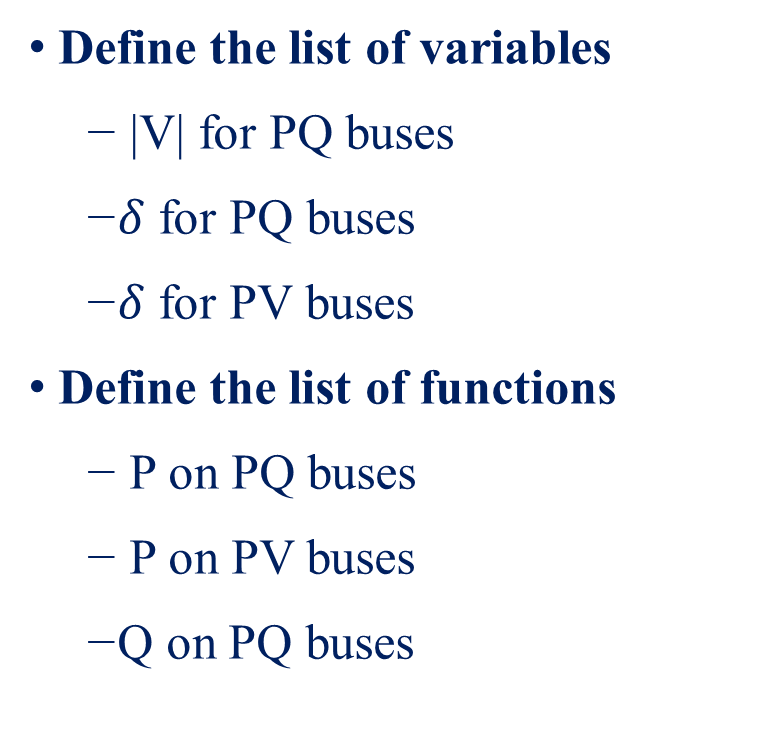

function [X,F_specified,VoltageMag,VoltageAngle,slack_buses,PQ_buses,PV_buses]=function_Defintion(bus_data)
    nBuses = size(bus_data, 1);
    VoltageMag = ones(nBuses, 1); % Initialize all voltage magnitudes to 1
    VoltageAngle = zeros(nBuses, 1); % Initialize all voltage angles to 0  
    % angle is in Radians
    ActivePower = zeros(nBuses, 1); % Initialize all active powers to 0
    ReactivePower = zeros(nBuses, 1); % Initialize all reactive powers to 0
    
    % Process each bus based on available data
    for i = 1:nBuses
        % Detect bus type
        if bus_data(i,1)==1 % Slack Bus
            % Slack bus: Specified V and theta
            VoltageMag(i) = bus_data(i, 4);
            VoltageAngle(i) = bus_data(i, 5);
        elseif bus_data(i,1)==2 % PQ Bus
            % PQ bus: Specified P and Q
            ActivePower(i) = bus_data(i, 2);
            ReactivePower(i) = bus_data(i, 3);
            VoltageMag(i) = 1.0;
            VoltageAngle(i) = 0;
        elseif bus_data(i,1)==3 % PV Bus
            % PV bus: Specified P and V
            ActivePower(i) = bus_data(i, 2);
            VoltageMag(i) = bus_data(i, 4);
            VoltageAngle(i) = 0;
        end
    end

    slack_buses=find(bus_data(:,1)==1); % slack busses
    PQ_buses=find(bus_data(:,1)==2);% PQ busses
    PV_buses=find(bus_data(:,1)==3); % PV busses
   
    X=[
        VoltageMag(PQ_buses);
        VoltageAngle(PQ_buses);
        VoltageAngle(PV_buses);
        ];
    F_specified=[
        ActivePower(PQ_buses);
        ActivePower(PV_buses);
        ReactivePower(PQ_buses);
       ];


end



**Newton Raphson Load Flow Analysis**

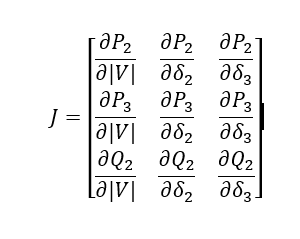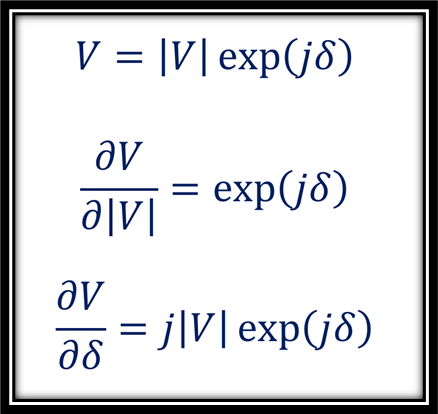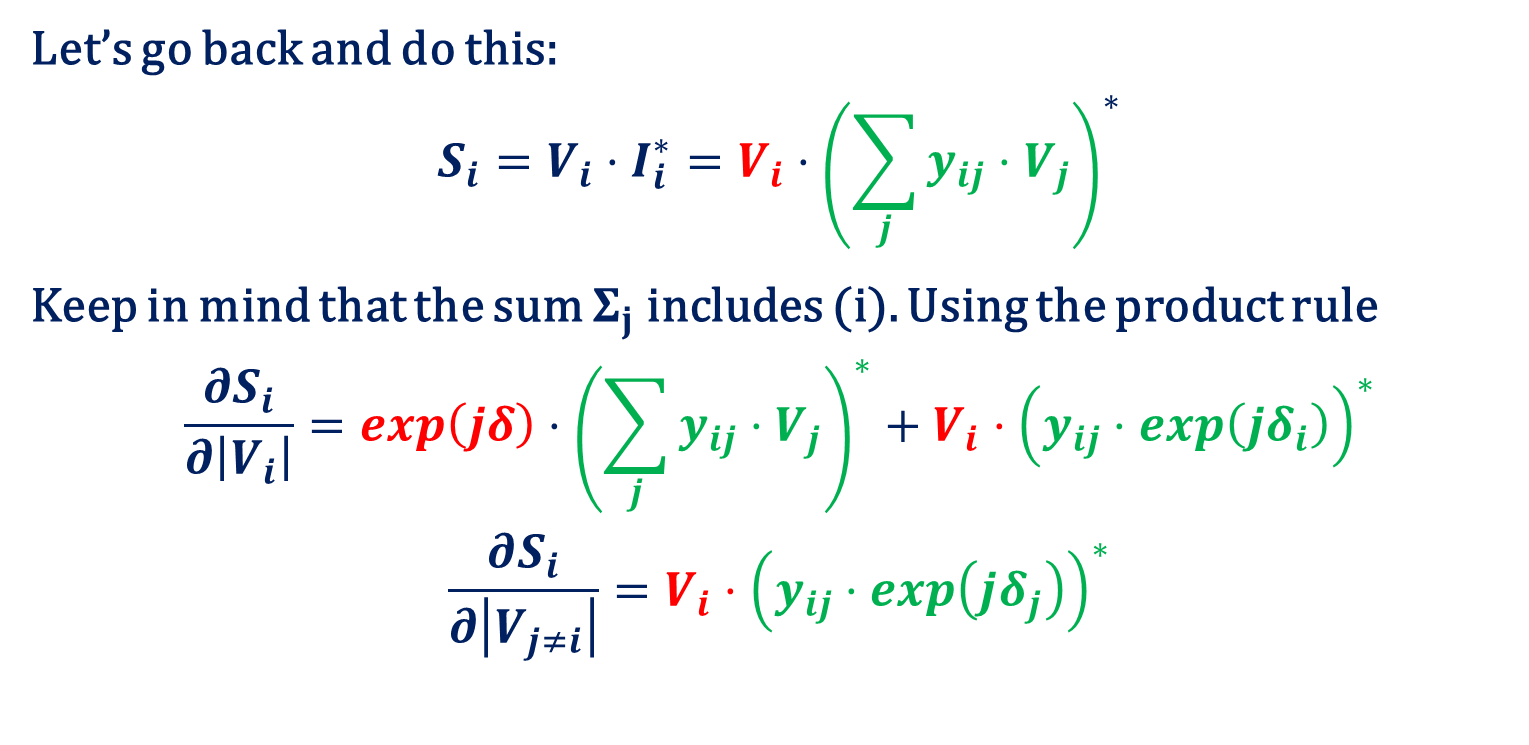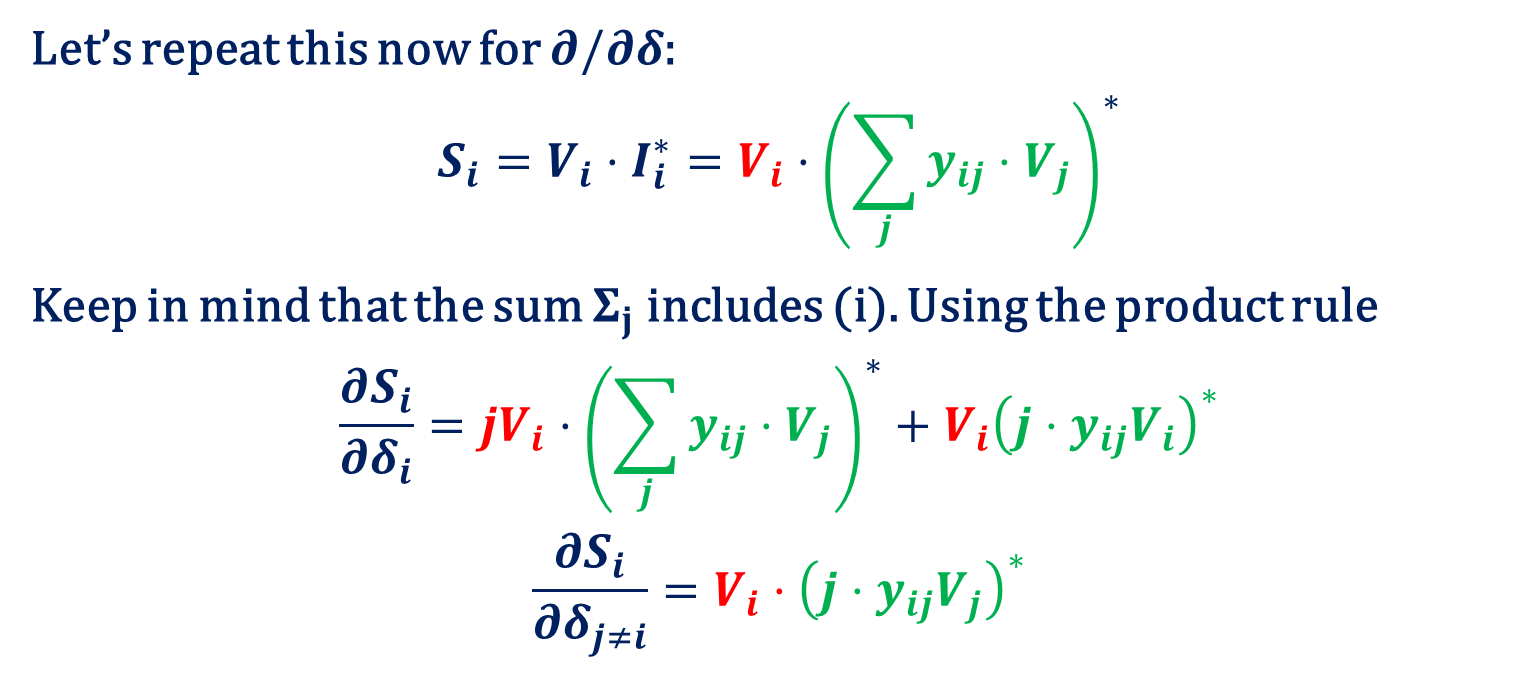


function [ComplexVoltage,IterationTable]=solvePowerFlowNR(Ybus,X,F_specified,VoltageMag,VoltageAngle,slack_buses,PQ_buses,PV_buses,nBuses,maxIter,tolerance,printIterations)
    nRef=numel(slack_buses);
    nPQ=numel(PQ_buses);
    nPV=numel(PV_buses);
    X_old=X;
    F_new=F_specified;
    ComplexVoltage=VoltageMag.*exp(1j.*VoltageAngle);
    
    headers = ['Number_of_Iteration', 'Error', strcat('V', string(1:nBuses))];
    IterationTable = array2table(zeros(0, length(headers)), 'VariableNames',headers);
    
    
    
    for iter = 1:maxIter
        
        Complex_Voltage = strings(0); % Initialize an empty string array
    
        %Calculate actual power in each bus
        Complex_power_calculated = zeros(nBuses, 1);% intialize the actual active power 
        for i = 1:nBuses
           Complex_power_calculated(i)=ComplexVoltage(i).*conj(Ybus(i,:)*ComplexVoltage);
           %%fprintf("\n V%g: %g<%g",i,VoltageMag(i),VoltageAngle(i)*180/pi)
           Complex_Voltage(end+1) = sprintf("%0.4g<%0.4g°",VoltageMag(i), VoltageAngle(i)*180/pi);
        end
    
        ReactivePower_calculated=imag(Complex_power_calculated);
        ActivePower_calculated=real(Complex_power_calculated);
    
        % calculated function values
        F_calculated=[
        ActivePower_calculated(PQ_buses);
        ActivePower_calculated(PV_buses);
        ReactivePower_calculated(PQ_buses);
       ];
    
      % the power mismatch 
       dF=F_specified-F_calculated;
       %fprintf('\n Iteration: %d    Power Mismatch: %d',iter,max(dF))
        newRow = array2table([iter, max(abs(dF)), Complex_Voltage], 'VariableNames', headers);
        IterationTable = [IterationTable; newRow];

       if (max(abs(dF))<= tolerance)
           break;
       else  
           % Build the jackobian matrix
           for i = 1:nBuses
               for j=1:nBuses
                   if (i==j)
                   dS_dVm(i,j)=exp(1j*VoltageAngle(i)).*conj(Ybus(i,:)*ComplexVoltage) + ComplexVoltage(i)*conj(Ybus(i,j)*exp(1j*VoltageAngle(i)));
                   dS_dVa(i,j)= 1j*ComplexVoltage(i)*conj(Ybus(i,:)*ComplexVoltage) + ComplexVoltage(i)*conj(1j*Ybus(i,j)*ComplexVoltage(i));
                   else
                   dS_dVm(i,j)=ComplexVoltage(i)*conj(Ybus(i,j)*exp(1j*VoltageAngle(i)));
                   dS_dVa(i,j)=ComplexVoltage(i)*conj(1j*Ybus(i,j)*ComplexVoltage(i));
        
                   end     
               end
           end
        
           %trsnasferign to dp and dQ
        
           dP_dVm=real(dS_dVm);
           dQ_dVm=imag(dS_dVm);
           dP_dVa=real(dS_dVa);
           dQ_dVa=imag(dS_dVa);
        
           % the jacobian matrix is 
           J=[dP_dVm(PQ_buses,PQ_buses),dP_dVa(PQ_buses,PQ_buses),dP_dVa(PQ_buses,PV_buses);
              dP_dVm(PV_buses,PQ_buses),dP_dVa(PV_buses,PQ_buses),dP_dVa(PV_buses,PV_buses);
              dQ_dVm(PQ_buses,PQ_buses),dQ_dVa(PQ_buses,PQ_buses),dQ_dVa(PQ_buses,PV_buses);
            ];
          %the function error 
          % dX=inv(J)*dF
          inv(J)
          dX=J\dF;
          X=X_old+dX;
          X_old=X;
    
          %update the voltage magnitude and voltage angle
           VoltageMag(PQ_buses)=X(1:nPQ);
           VoltageAngle(PQ_buses)=X(nPQ+1:nPQ+nPQ);
           VoltageAngle(PV_buses)=X(nPQ+nPQ+1:end);
           
           ComplexVoltage=VoltageMag.*exp(1j.*VoltageAngle);
           
       end
        
        
    end
    
    % Display the final table
     for category=headers
      if(category=="Number_of_Iteration" || category=="Error") 
          continue;
      end
      IterationTable.(category)=categorical(IterationTable.(category));
     end    
    IterationTable.Number_of_Iteration=double(IterationTable.Number_of_Iteration);
    IterationTable.Error=double(IterationTable.Error);
    
    if (printIterations) 
     disp(IterationTable);
    end
end



## System results Report

From the power-flow solution, calculate power (real & reactive) injections at slack bus, real power injection at PV

bus, and current flows in all transmission lines

function [busTable,lineTable]=systemReport(Ybus,ComplexVoltage,line_data,bus_data,printReport)
    bus_current=Ybus*ComplexVoltage;
    S_injected = ComplexVoltage .* conj(bus_current);
    P_injected = real(S_injected);
    Q_injected = imag(S_injected);
    
    % Initialize variables for line currents and line power
    nLines = size(line_data, 1);
    Line_Currents = zeros(nLines, 1);
    Line_Power_loss = zeros(nLines, 1);
    
    for i = 1:nLines
        % Extract line information
        fromBus = line_data(i, 1);
        toBus = line_data(i, 2);
        
        % Calculate current flow in the line
        V_from = ComplexVoltage(fromBus);
        V_to = ComplexVoltage(toBus);
        Y_line = Ybus(fromBus, toBus); % Simplified line admittance
        
        Line_Currents(i) = (V_from - V_to) * Y_line;
        
        % Calculate complex power flow in the line from 'fromBus' to 'toBus'
        %Line_Power(i) = V_from * conj(Line_Currents(i))
        Line_Power_loss(i)=abs(Line_Currents(i))*(real(1/Y_line))^2;
        
    end
    
    % update the bus and line dataset and fill the nan values
    line_data(:,6)=abs(Line_Currents);
    line_data(:,7)=angle(Line_Currents)*180/pi;
    line_data(:,8)=Line_Power_loss;
    
    
    bus_data(:,2)=P_injected;
    bus_data(:,3)=Q_injected;
    bus_data(:,4)=abs(ComplexVoltage);
    bus_data(:,5)=angle(ComplexVoltage)*180/pi;
    bus_data(:,6)=abs(bus_current);
    bus_data(:,7)=angle(bus_current)*180/pi;
    
    %present the result in table format for easy redablity
    lineTable = array2table(line_data);
    headers = {'From Bus', 'To Bus', 'Resistance','Reactance', 'Shunt Reactance','Line Current Mag', 'Line Current Angle', 'Power Loss'};
    lineTable.Properties.VariableNames = headers;
    
    %Bus#  %P    %Q    %V   %theta 
    busTable = array2table(bus_data);
    headers = {'Bus Type', 'Injected Active Power','Injected Reactive Power','Bus Voltage Mag', 'Bus Voltage Angle', 'Bus Current Mag', 'Bus Current Angle'};
    busTable.Properties.VariableNames = headers;
    
    if (printReport)
        fprintf("\n---------------------------------------------Line Data Updated -------------------------------------------\n \n");
        disp(lineTable);
        fprintf("\n---------------------------------------------Bus Data Updated -------------------------------------------\n \n");

        fprintf("\n\n")
        disp(busTable);
    end
end
